# Machine Learning: Programming Exercise 8

## Anomaly Detection and Recommender Systems

In this exercise, you will implement the anomaly detection algorithm and apply it to detect failing servers on a network. In the second part, you will use collaborative filtering to build a recommender system for movies.

### Files needed for this exercise

- `ex8.mlx` - MATLAB Live Script that steps you through the exercise

- `ex8data1.mat` - First example Dataset for anomaly detection

- `ex8data2.mat` - Second example Dataset for anomaly detection

- `ex8_movies.mat` - Movie Review Dataset

- `ex8_movieParams.mat` - Parameters provided for debugging

- `multivariateGaussian.m` - Computes the probability density function for a Gaussian distribution

- `visualizeFit.m` - 2D plot of a Gaussian distribution and a dataset

- `checkCostFunction.m` - Gradient checking for collaborative filtering

- `computeNumericalGradient.m` - Numerically compute gradients

- `fmincg.m` - Function minimization routine (similar to `fminunc`)

- `loadMovieList.m` - Loads the list of movies into a cell-array

- movie_ids.txt - List of movies

- `normalizeRatings.m` - Mean normalization for collaborative filtering

- `submit.m` - Submission script that sends your solutions to our servers

- `*estimateGaussian.m` - Estimate the parameters of a Gaussian distribution with a diagonal covariance matrix

- `*selectThreshold.m` - Find a threshold for anomaly detection

- `*cofiCostFunc.m` - Implement the cost function for collaborative filtering

**** indicates files you will need to complete***

#### Clear existing variables and confirm that your Current Folder is set correctly

Click into this section, then click the 'Run Section' button above. This will execute the `clear` command to clear existing variables and the `dir` command to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex8' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

clear
dir

.                           cofiCostFunc.m              ex8_companion1.mlx          ex8data2.mat                multivariateGaussian.m      token.mat                   
..                          computeNumericalGradient.m  ex8_companion2.mlx          fmincg.m                    normalizeRatings.m          visualizeFit.m              
.MATLABDriveTag             estimateGaussian.asv        ex8_movieParams.mat         lib                         selectThreshold.asv         
checkCostFunction.m         estimateGaussian.m          ex8_movies.mat              loadMovieList.m             selectThreshold.m           
cofiCostFunc.asv            ex8.mlx                     ex8data1.mat                movie_ids.txt               submit.m                    



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. Anomaly Detection

In this exercise, you will implement an anomaly detection algorithm to detect anomalous behavior in server computers. The features measure the throughput (mb/s) and latency (ms) of response of each server. While your servers were operating, you collected $m = 307$ examples of how they were behaving, and thus have an unlabeled dataset $\{x^{(1)},\ldots,x^{(m)}\}
$. You suspect that the vast majority of these examples are 'normal' (non-anomalous) examples of the servers operating normally, but there might also be some examples of servers acting anomalously within this dataset.

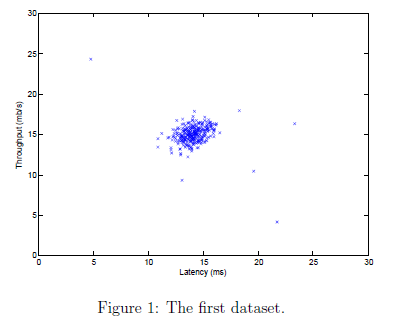

    You will use a Gaussian model to detect anomalous examples in your dataset. You will first start on a 2D dataset that will allow you to visualize what the algorithm is doing. On that dataset you will fit a Gaussian distribution and then find values that have very low probability and hence can be considered anomalies. After that, you will apply the anomaly detection algorithm to a larger dataset with many dimensions. The code below will visualize the dataset as shown in Figure 1.

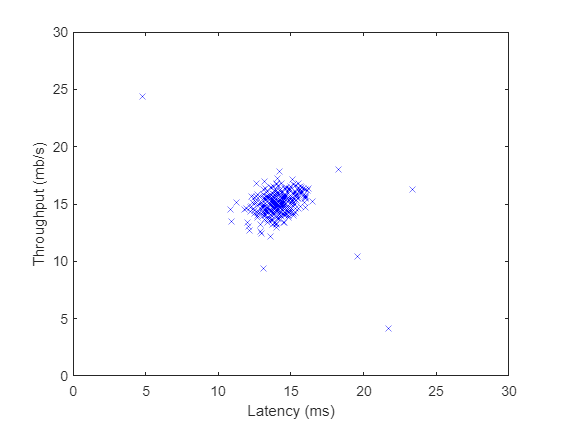

% The following command loads the dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data1.mat');

% Visualize the example dataset
plot(X(:, 1), X(:, 2), 'bx');
axis([0 30 0 30]);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

### 1.1 Gaussian distribution

To perform anomaly detection, you will first need to fit a model to the data's distribution. Given a training set $\{x^{(1)},\dots,x^{(m)}\}$ (where $x^{(i)}\in\mathbb{R}^n$), you want to estimate the Gaussian distribution for each of the features $x_i$. For each feature $i = 1\ldots n$ you need to find parameters $\mu_i$ and $\sigma^2_i$ that fit the data in the $i$-th dimension $\{x_i^{(1)},\ldots,x^{(m)}_i\}$(the $i$-th dimension of each example).

    The Gaussian distribution is given by


$$p(x;\mu,\sigma^2)=\frac{1}{\sqrt{2\pi\sigma^2}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$$


where $\mu$ is the mean and $\sigma^2$ controls the variance.

### 1.2 Estimating parameters for a Gaussian

You can estimate the parameters, $(\mu_i,\sigma_i^2)$, of the $i$-th feature by using the following equations. To estimate the mean, you will use:

$\mu_i = \frac{1}{m}\sum_{j=1}^m{x^{(j)}}$,

and for the variance you will use:

$\sigma^2_i = \frac{1}{m}\sum_{j=1}^m{(x^{(j)}-\mu_i)^2}$.

Your task is to complete the code in `estimateGaussian.m`. This function takes as input the data matrix `X` and should output an $n$-dimension vector `mu` that holds the mean of all the $n$ features and another $n$-dimension vector `sigma2` that holds the variances of all the features. You can implement this using a `for `loop over every feature and every training example (though a vectorized implementation might be more efficient; feel free to use a vectorized implementation if you prefer). Note that in MATLAB, the `var` function will (by default) use $\frac{1}{m-1}$, instead of $\frac{1}{m}$ when computing $\sigma^2_i$.

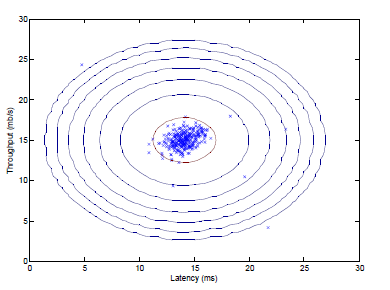

    Once you have completed the code in `estimateGaussian.m`, the code below will visualize the contours of the fitted Gaussian distribution. You should get a plot similar to Figure 2. From your plot, you can see that most of the examples are in the region with the highest probability, while the anomalous examples are in the regions with lower probabilities.

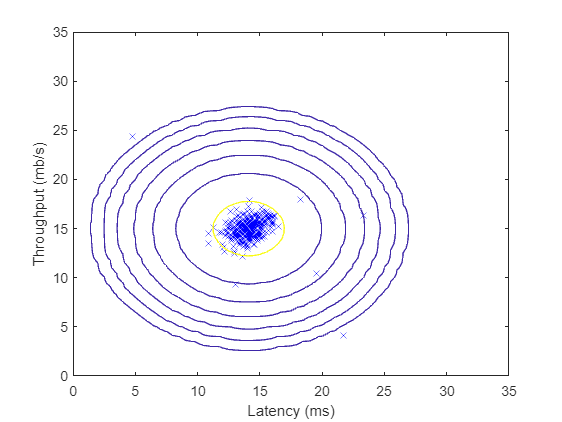

%  Estimate mu and sigma2
[mu, sigma2] = estimateGaussian(X);

%  Returns the density of the multivariate normal at each data point (row) of X
p = multivariateGaussian(X, mu, sigma2);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.3 Selecting the threshold, $\epsilon$

Now that you have estimated the Gaussian parameters, you can investigate which examples have a very high probability given this distribution and which examples have a very low probability. The low probability examples are more likely to be the anomalies in our dataset. One way to determine which examples are anomalies is to select a threshold based on a cross validation set. In this part of the exercise, you will implement an algorithm to select the threshold $\epsilon$ using the $F_1$ score on a cross validation set.

    You should now complete the code in `selectThreshold.m`. For this, we will use a cross validation set $\{(x^{(1)}_{cv},y^{(1)}_{cv}),\ldots, (x^{(m)}_{cv},y^{(m)}_{cv})\}$, where the label $y = 1$ corresponds to an anomalous example, and $y = 0$ corresponds to a normal example. For each cross validation example, we will compute $p(x^{(i)}_{cv})$. The vector of all of these probabilities $p(x^{(1)}_{cv}),\ldots,p(x^{(m)}_{cv})$ is passed to `selectThreshold.m` in the vector `pval`. The corresponding labels $y^{(1)}_{cv},\ldots,y^{m)}_{cv}$ is passed to the same function in the vector `yval`.

    The function `selectThreshold.m` should return two values; the first is the selected threshold $\epsilon$. If an example $x$ has a low probability $p(x) < \epsilon$, then it is considered to be an anomaly. The function should also return the $F_1$ score, which tells you how well you're doing on finding the ground truth anomalies given a certain threshold. For many different values of $\epsilon$, you will compute the resulting $F_1$ score by computing how many examples the current threshold classifies correctly and incorrectly.

    The $F_1$ score is computed using precision (*prec*) and recall (*rec*):

$F_1 = \frac{2 ( prec)(rec)}{prec + rec}$,

You compute precision and recall by:


$$prec = \frac{tp}{tp + fp}$$



$$rec = \frac{tp}{tp + fn}$$


where

- $tp$ is the number of true positives: the ground truth label says it's an anomaly and our algorithm correctly classified it as an anomaly.

- $fp$ is the number of false positives: the ground truth label says it's not an anomaly, but our algorithm incorrectly classified it as an anomaly.

- $fn$ is the number of false negatives: the ground truth label says it's an anomaly, but our algorithm incorrectly classified it as not being anomalous.

In the provided code `selectThreshold.m`, there is already a loop that will try many different values of $\epsilon$ and select the "best" based $\epsilon$ on the $F_1$ score. You should now complete the code in `selectThreshold.m`. You can implement the computation of the $F_1$ score using a `for` loop over all the cross validation examples (to compute the values $tp,\; fp,\text{and }fn$. You should see a value for epsilon of about `8.99e-05`.

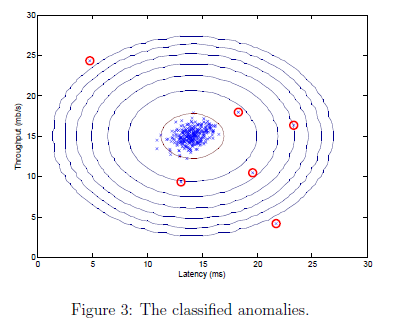

**Implementation Note**: In order to compute $tp,\; fp,\text{and }fn$, you may be able to use a vectorized implementation rather than loop over all the examples. This can be implemented by MATLAB's equality test between a vector and a single number. If you have several binary values in an $n$-dimensional binary vector $v\in\{0,\;1\}^n$, you can find out how many values in this vector are 0 by using: `sum(v == 0)`. You can also apply a logical `and` operator to such binary vectors. For instance, let `cvPredictions` be a binary vector of the size of your cross validation set, where the $i$-th element is 1 if your algorithm considers $x^{(i)}_{cv}$ an anomaly, and 0 otherwise. You can then, for example, compute the number of false positives using:` fp = sum((cvPredictions == 1) & (yval == 0))`.

    Once you have completed the code in `selectThreshold.m`, the code below will detect and circle the anomalies in the plot (Figure 3).

pval = multivariateGaussian(Xval, mu, sigma2);

[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 8.990853e-05


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.875000


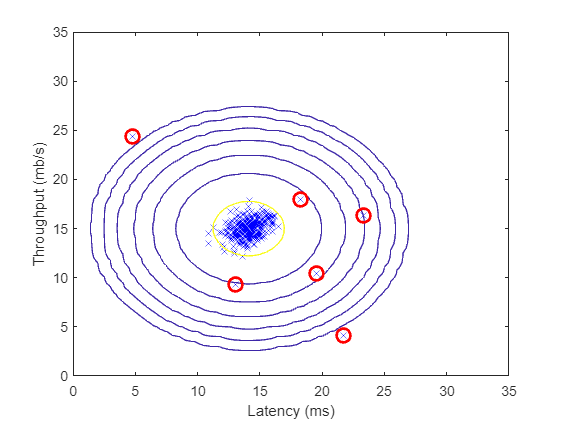


%  Find the outliers in the training set and plot the
outliers = find(p < epsilon);

%  Visualize the fit
visualizeFit(X,  mu, sigma2);
xlabel('Latency (ms)');
ylabel('Throughput (mb/s)');
%  Draw a red circle around those outliers
hold on
plot(X(outliers, 1), X(outliers, 2), 'ro', 'LineWidth', 2, 'MarkerSize', 10);
hold off

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.4 High dimensional dataset

The code in this section will run the anomaly detection algorithm you implemented on a more realistic and much harder dataset. In this dataset, each example is described by 11 features, capturing many more properties of your compute servers. The code below will use your code to estimate the Gaussian parameters ($\mu_i$ and $\sigma^2_i$), evaluate the probabilities for both the training data `X` from which you estimated the Gaussian parameters, and do so for the the cross-validation set `Xval`. Finally, it will use `selectThreshold` to find the best threshold $\epsilon$. You should see a value `epsilon` of about `1.38e-18`, and 117 anomalies found.

%  Loads the second dataset. You should now have the variables X, Xval, yval in your environment
load('ex8data2.mat');

%  Apply the same steps to the larger dataset
[mu, sigma2] = estimateGaussian(X);

%  Training set 
p = multivariateGaussian(X, mu, sigma2);

%  Cross-validation set
pval = multivariateGaussian(Xval, mu, sigma2);

%  Find the best threshold
[epsilon, F1] = selectThreshold(yval, pval);
fprintf('Best epsilon found using cross-validation: %e\n', epsilon);

Best epsilon found using cross-validation: 1.377229e-18


fprintf('Best F1 on Cross Validation Set:  %f\n', F1);

Best F1 on Cross Validation Set:  0.615385


fprintf('# Outliers found: %d\n', sum(p < epsilon));

# Outliers found: 117


## 2. Recommender Systems

In this part of the exercise, you will implement the collaborative filtering learning algorithm and apply it to a dataset of movie ratings*. This dataset consists of ratings on a scale of 1 to 5. The dataset has $n_u = 943$ users, and $n_m = 1682$ movies. In the next parts of this exercise, you will implement the function `cofiCostFunc.m` that computes the collaborative fitlering objective function and gradient. After implementing the cost function and gradient, you will use `fmincg.m` to learn the parameters for collaborative filtering.

*[MovieLens 100k Dataset](https://grouplens.org/datasets/movielens/) from GroupLens Research.

### 2.1 Movie ratings dataset

The code in this section will load the dataset `ex8_movies.mat`, providing the variables `Y` and `R` in your MATLAB environment. The matrix `Y` (a `num_movies` $\times$ `num_users` matrix) stores the ratings $y^{(i,j)}$ (from 1 to 5). The matrix `R` is an binary-valued indicator matrix, where` R(i,j) = 1` if user `j` gave a rating to movie `i`, and `R(i,j) = 0` otherwise. The objective of collaborative filtering is to predict movie ratings for the movies that users have not yet rated, that is, the entries with `R(i,j) = 0`. This will allow us to recommend the movies with the highest predicted ratings to the user.

    To help you understand the matrix `Y`, the code below will compute the average movie rating for the first movie (Toy Story) and output the average rating to the screen. Throughout this part of the exercise, you will also be working with the matrices, `X` and `Theta`:

`X = `$\left\lbrack \begin{array}{c}
-{\;\left(x^{\left(1\right)} \right)}^T -\\
-{\;\left(x^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(x^{\left(n_m \right)} \right)}^T -
\end{array}\right\rbrack$,    `Theta = `$\left\lbrack \begin{array}{c}
-{\;\left(\theta^{\left(1\right)} \right)}^T -\\
-{\;\left(\theta^{\left(2\right)} \right)}^T -\\
\vdots \\
-{\;\left(\theta^{\left(n_u \right)} \right)}^T -
\end{array}\right\rbrack$.

% Load data
load('ex8_movies.mat');

- `Y` is a 1682 x 943 matrix, containing ratings (1 - 5) of 1682 movies on 943 users

- `R` is a 1682 x 943 matrix, where `R(i,j)` = 1 if and only if user `j` gave a rating to movie `i`

% From the matrix, we can compute statistics like average rating.
fprintf('Average rating for movie 1 (Toy Story): %f / 5\n\n', mean(Y(1, R(1, :))));

Average rating for movie 1 (Toy Story): 3.878319 / 5



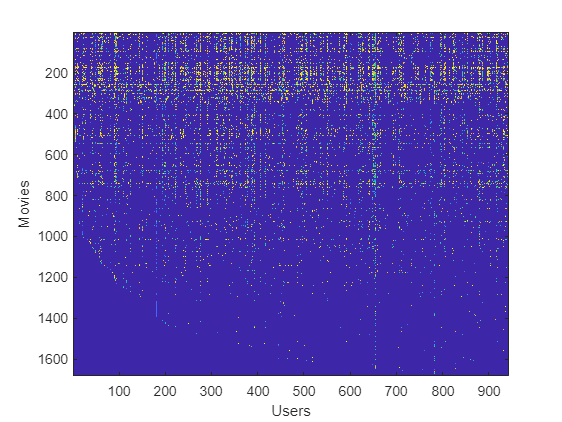

%  We can "visualize" the ratings matrix by plotting it with imagesc
imagesc(Y);
ylabel('Movies');
xlabel('Users');

The $i$-th row of `X` corresponds to the feature vector $x^{(i)}$ for the $i$-th movie, and the $j$-th row of `Theta` corresponds to one parameter vector $\theta^{(j)}$, for the $j$-th user. Both $x^{(i)}$ and $\theta^{(j)}$ are $n$-dimensional vectors. For the purposes of this exercise, you will use $n = 100$, and therefore, $x^{(i)} \in\mathbb{R}^{100}$ and $\theta^{(j)} \in\mathbb{R}^{100}$. Correspondingly, `X` is a $n_m\times 100$ matrix and `Theta` is a $n_u\times 100$ matrix.

### 2.2 Collaborative filtering learning algorithm

Now, you will start implementing the collaborative filtering learning algorithm. You will start by implementing the cost function (without regularization). The collaborative filtering algorithm in the setting of movie recommendations considers a set of $n$-dimensional parameter vectors $x^{(1)},\ldots,x^{(n_m)}$ and $\theta^{(1)},\ldots, \theta^{(n_u)}$, where the model predicts the rating for movie $i$ by user $j$ as $y^{(i,j)} = (\theta^{(j)})^T x^{(i)}$. Given a dataset that consists of a set of ratings produced by some users on some movies, you wish to learn the parameter vectors $x^{(1)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}$ that produce the best fit (minimizes the squared error).

    You will complete the code in `cofiCostFunc.m` to compute the cost function and gradient for collaborative filtering. Note that the parameters to the function (i.e., the values that you are trying to learn) are `X` and `Theta`. In order to use an off-the-shelf minimizer such as `fmincg`, the cost function has been set up to unroll the parameters into a single vector `params`. You had previously used the same vector unrolling method in the neural networks programming exercise.

#### 2.2.1 Collaborative filtering cost function

The collaborative filtering cost function (without regularization) is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2$$


You should now modify `cofiCostFunc.m` to return this cost in the variable `J`. Note that you should be accumulating the cost for user $j$ and movie $i$ only if $R(i,j) = 1$. After you have completed the function, the code below will run your cost function. You should expect to see an output of `22.22`.

**Implementation Note:** We strongly encourage you to use a vectorized implementation to compute `J`, since it will later by called many times by the optimization package `fmincg`. As usual, it might be easiest to first write a non-vectorized implementation (to make sure you have the right answer), and the modify it to become a vectorized implementation (checking that the vectorization steps don't change your algorithm's output). To come up with a vectorized implementation, the following tip might be helpful: You can use the `R` matrix to set selected entries to 0. For example, `R.*M` will do an element-wise multiplication between `M` and `R`; since `R` only has elements with values either 0 or 1, this has the effect of setting the elements of `M` to 0 only when the corresponding value in `R` is 0. Hence, `sum(sum(R.*M))` is the sum of all the elements of `M` for which the corresponding element in `R` equals 1.

%  Load pre-trained weights (X, Theta, num_users, num_movies, num_features)
load('ex8_movieParams.mat');

%  Reduce the data set size so that this runs faster
num_users = 4; num_movies = 5; num_features = 3;
X = X(1:num_movies, 1:num_features);
Theta = Theta(1:num_users, 1:num_features);
Y = Y(1:num_movies, 1:num_users);
R = R(1:num_movies, 1:num_users);

%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)],  Y, R, num_users, num_movies,num_features, 0);

Theta_grad =   -10.5680    4.6278   -7.1600
   -3.0510    1.1644   -3.4741
         0         0         0
         0         0         0


fprintf('Cost at loaded parameters: %f ',J);

Cost at loaded parameters: 22.224604 

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.2 Collaborative filtering gradient

Now, you should implement the gradient (without regularization). Specically, you should complete the code in `cofiCostFunc.`m to return the variables `X_grad` and `Theta_gra`d. Note that `X_grad` should be a matrix of the same size as `X` and similarly, `Theta_grad` is a matrix of the same size as `Theta`. The gradients of the cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}$$


Note that the function returns the gradient for both sets of variables by unrolling them into a single vector. After you have completed the code to compute the gradients, the code below will run a gradient check (`checkCostFunction`) to numerically check the implementation of your gradients. (This is similar to the numerical check that you used in the neural networks exercise.) If your implementation is correct, you should find that the analytical and numerical gradients match up closely.

**Implementation Note**: You can get full credit for this assignment without using a vectorized implementation, but your code will run much more slowly (a small number of hours), and so we recommend that you try to vectorize your implementation. To get started, you can implement the gradient with a `for` loop over movies (for computing $\frac{\partial J}{\partial x_k^{(i)}$) and a `for` loop over users (for computing $\frac{\partial J}{\partial \theta_k^{(j)}$). When you first implement the gradient, you might start with an unvectorized version, by implementing another inner `for` loop that computes each element in the summation. After you have completed the gradient computation this way, you should try to vectorize your implementation (vectorize the inner `for` loops), so that you're left with only two `for` loops (one for looping over movies to compute $\frac{\partial J}{\partial x_k^{(i)}$ for each movie, and one for looping over users to compute $\frac{\partial J}{\partial \theta_k^{(j)}$ for each user).

    To perform the vectorization, you might find this helpful: You should come up with a way to compute all the derivatives associated with $x^{(i)}_1,x^{(i)}_2,\ldots,x^{(i)}_n$, (i.e., the derivative terms associated with the feature vector $x^{(i)}$) at the same time. Let us define the derivatives for the feature vector of the $i$-th movie as:


$${\left({\mathrm{X}}_{\textrm{grad}} \left(\mathrm{i},:\right)\right)}^T =\left\lbrack \begin{array}{c}
\frac{\partial J}{\partial x_1^{\left(i\right)} }\\
\frac{\partial J}{\partial x_2^{\left(i\right)} }\\
\vdots \\
\frac{\partial J}{\partial x_n^{\left(i\right)} }
\end{array}\right\rbrack =\sum_{j:r\left(i,j\right)=1} \left({\left(\theta^{\left(j\right)} \right)}^T x^{\left(i\right)} -y^{\left(i,j\right)} \right)\;\theta^{\left(j\right)}$$


To vectorize the above expression, you can start by indexing into `Theta` and `Y` to select only the elements of interest (that is, those with $r(i,j) = 1$). Intuitively, when you consider the features for the $i$-th movie, you only need to be concerned about the users who had given ratings to the movie, and this allows you to remove all the other users from `Theta` and `Y`.

    Concretely, you can set `idx = find(R(i,:)==1)` to be a list of all the users that have rated movie $i$. This will allow you to create the temporary matrices `Theta_temp = Theta(idx,:)` and `Y_temp = Y(i,idx)` that index into `Theta` and `Y` to give you only the set of users which have rated the $i$-th movie. This will allow you to write the derivatives as:

${\mathrm{X}}_{\textrm{grad}} \left(i,:\right)=\left(\mathrm{X}\left(i,:\right)*{\Theta \;}_{\textrm{temp}}^T -{\mathrm{Y}}_{\textrm{temp}} \right)*{\Theta \;}_{\textrm{temp}}$.

(Note: The vectorized computation above returns a row-vector instead.) After you have vectorized the computations of the derivatives with respect to $x^{(i)}$, you should use a similar method to vectorize the derivatives with respect to $\theta^{(j)}$ as well.

%  Check gradients by running checkNNGradients
checkCostFunction;

Theta_grad =     1.4417   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4530    3.0942    0.7514
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4415   -0.4538    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4538    3.0946    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2329
   -1.8179    0.5174   -1.3481
    5.4538    3.0943    0.7515
   -4.0572    1.1220   -2.6775


Theta_grad =     1.4416   -0.4537    0.7807
   -0.5970   -0.2140   -0.2328
   -1.8174    0.5173   -1.3479
    5.4531    3.0944    0.7512
   -4.0563    1.1218   -2.6771


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8175    0.5173   -1.3479
    5.4534    3.0944    0.7513
   -4.0564    1.1219   -2.6771


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8178    0.5174   -1.3481
    5.4534    3.0944    0.7513
   -4.0571    1.1220   -2.6775


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5970   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4415   -0.4538    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4533    3.0940    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4417   -0.4536    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4535    3.0947    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4417   -0.4537    0.7807
   -0.5970   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4536    3.0944    0.7514
   -4.0571    1.1219   -2.6775


Theta_grad =     1.4414   -0.4538    0.7806
   -0.5972   -0.2139   -0.2329
   -1.8177    0.5174   -1.3480
    5.4533    3.0943    0.7513
   -4.0564    1.1219   -2.6771


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8177    0.5174   -1.3480
    5.4534    3.0944    0.7513
   -4.0565    1.1220   -2.6771


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5172   -1.3480
    5.4534    3.0944    0.7513
   -4.0569    1.1219   -2.6775


Theta_grad =     1.4416   -0.4538    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4536    0.7806
   -0.5970   -0.2139   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4415   -0.4538    0.7807
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4538    3.0948    0.7511
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4417   -0.4536    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4530    3.0940    0.7516
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4418   -0.4538    0.7808
   -0.5972   -0.2139   -0.2329
   -1.8175    0.5173   -1.3480
    5.4529    3.0945    0.7512
   -4.0566    1.1219   -2.6774


Theta_grad =     1.4414   -0.4537    0.7805
   -0.5970   -0.2140   -0.2328
   -1.8178    0.5174   -1.3480
    5.4539    3.0942    0.7515
   -4.0569    1.1220   -2.6772


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8177    0.5174   -1.3480
    5.4534    3.0944    0.7513
   -4.0568    1.1219   -2.6772


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8175    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6774


Theta_grad =     1.4415   -0.4538    0.7806
   -0.5970   -0.2139   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4536    0.7807
   -0.5971   -0.2140   -0.2329
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4408   -0.4539    0.7804
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4423   -0.4535    0.7808
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5976   -0.2139   -0.2330
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5966   -0.2140   -0.2326
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8182    0.5175   -1.3483
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8170    0.5172   -1.3477
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4527    3.0942    0.7511
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4541    3.0945    0.7515
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0573    1.1221   -2.6777


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0561    1.1218   -2.6770


Theta_grad =     1.4414   -0.4542    0.7807
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4418   -0.4532    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5970   -0.2141   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2138   -0.2329
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8175    0.5173   -1.3479
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8178    0.5174   -1.3481
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4532    3.0941    0.7514
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4536    3.0947    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0566    1.1219   -2.6772


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0569    1.1220   -2.6774


Theta_grad =     1.4414   -0.4537    0.7805
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4418   -0.4538    0.7807
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5973   -0.2139   -0.2329
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5969   -0.2140   -0.2327
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8180    0.5174   -1.3482
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad =     1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8173    0.5172   -1.3478
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


Theta_grad = 5×3
    1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4532    3.0945    0.7512
   -4.0567    1.1219   -2.6773


Theta_grad = 5×3
    1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4536    3.0943    0.7514
   -4.0567    1.1219   -2.6773


Theta_grad = 5×3
    1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0571    1.1220   -2.6775


Theta_grad = 5×3
    1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0564    1.1218   -2.6771


Theta_grad = 5×3
    1.4416   -0.4537    0.7806
   -0.5971   -0.2140   -0.2328
   -1.8176    0.5173   -1.3480
    5.4534    3.0944    0.7513
   -4.0567    1.1219   -2.6773


    2.4734    2.4734
   -3.3642   -3.3642
    3.0220    3.0220
   -0.0045   -0.0045
    1.3398    1.3398
   -3.0521   -3.0521
    2.0962    2.0962
    0.0222    0.0222
   -5.1495   -5.1495
    2.6312    2.6312
   -1.3667   -1.3667
    0.3324    0.3324
    1.4416    1.4416
   -0.5971   -0.5971
   -1.8176   -1.8176
    5.4534    5.4534
   -4.0567   -4.0567
   -0.4537   -0.4537
   -0.2140   -0.2140
    0.5173    0.5173
    3.0944    3.0944
    1.1219    1.1219
    0.7806    0.7806
   -0.2328   -0.2328
   -1.3480   -1.3480
    0.7513    0.7513
   -2.6773   -2.6773

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 7.39115e-13


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.3 Regularized cost function

The cost function for collaborative filtering with regularization is given by


$$J\left(x^{(i)},\ldots,x^{(n_m)},\;\theta^{(1)},\ldots,\theta^{(n_u)}\right)
=\\ \qquad\qquad \frac{1}{2}\sum_{(i,j):r(i,j)=1}\left((\theta^{(j)})^Tx^{(i)}-y^{(i,j)}\right)^2
+\left(\frac{\lambda}{2}\sum_{j=1}^{n_u}{\sum_{k=1}^{n}{(\theta_k^{(j)})^2}}\right)
+\left(\frac{\lambda}{2}\sum_{i=1}^{n_m}{\sum_{k=1}^{n}{(x_k^{(i)})^2}}\right)$$


You should now add regularization to your original computations of the cost function, $J$. After you are done, the code below will run your regularized cost function, and you should expect to see a cost of about `31.34`.

%  Evaluate cost function
J = cofiCostFunc([X(:); Theta(:)], Y, R, num_users, num_movies, num_features, 1.5);      

Theta_grad =   -10.1399    2.1014   -6.7656
   -2.2935    0.4824   -2.9979
   -0.6479   -0.7182    1.2701
    1.0929   -0.4078    0.4903


fprintf('Cost at loaded parameters (lambda = 1.5): %f',J);

Cost at loaded parameters (lambda = 1.5): 31.344056

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.2.4 Regularized gradient

Now that you have implemented the regularized cost function, you should proceed to implement regularization for the gradient. You should add to your implementation in `cofiCostFunc.m` to return the regularized gradient by adding the contributions from the regularization terms. Note that the gradients for the regularized cost function is given by:


$$\frac{\partial J}{\partial x_k^{(i)}} 
= \sum_{j:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right)\theta_k^{(j)}+\lambda x_k^{(i)}$$



$$\frac{\partial J}{\partial \theta_k^{(j)}} = \sum_{i:r(i,j)=1}\left((\theta^{(j)})^T x^{(i)} -y^{(i,j)}\right) x_k^{(i)}+\lambda\theta_k^{(j)}$$


This means that you just need to add $\lambda x^{(i)}$ to the `X_grad(i,:)` variable described earlier, and add $\lambda \theta^{(j)}$ to the `Theta_grad(j,:) `variable described earlier. After you have completed the code to compute the gradients, the code below will run another gradient check (`checkCostFunction`) to numerically check the implementation of your gradients.

%  Check gradients by running checkNNGradients
checkCostFunction(1.5);

Theta_grad =    -1.7367    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4578    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1671   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6976    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1669   -1.5952    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4577    7.5505    1.9999
   -2.4867   14.9199    7.5846
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4580    7.5506    2.0000
   -2.4873   14.9200    7.5848
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7366    3.8778   -0.7142
   -1.9312    1.6977    2.0173
   -1.4578    7.5505    1.9999
   -2.4869   14.9199    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7369    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4580    7.5506    1.9999
   -2.4872   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7366    3.8778   -0.7142
   -1.9312    1.6977    2.0173
   -1.4576    7.5505    1.9999
   -2.4865   14.9199    7.5847
    2.1668   -1.5951    0.2629


Theta_grad =    -1.7369    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4581    7.5506    1.9999
   -2.4875   14.9201    7.5847
    2.1671   -1.5955    0.2628


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6976    2.0173
   -1.4579    7.5506    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5952    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5954    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4578    7.5508    2.0000
   -2.4869   14.9205    7.5848
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5503    1.9998
   -2.4871   14.9194    7.5846
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8780   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5507    1.9999
   -2.4870   14.9202    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7367    3.8777   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5504    1.9999
   -2.4870   14.9197    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8781   -0.7142
   -1.9312    1.6977    2.0173
   -1.4580    7.5509    2.0000
   -2.4871   14.9206    7.5848
    2.1670   -1.5954    0.2628


Theta_grad =    -1.7367    3.8776   -0.7143
   -1.9312    1.6977    2.0173
   -1.4578    7.5502    1.9999
   -2.4869   14.9193    7.5846
    2.1669   -1.5952    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6976    2.0173
   -1.4579    7.5506    2.0000
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7367    3.8778   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2628


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5504    2.0000
   -2.4870   14.9201    7.5851
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4578    7.5506    1.9998
   -2.4871   14.9198    7.5843
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7367    3.8778   -0.7141
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    2.0000
   -2.4870   14.9200    7.5848
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7143
   -1.9312    1.6977    2.0173
   -1.4579    7.5506    1.9998
   -2.4870   14.9199    7.5846
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7367    3.8777   -0.7142
   -1.9312    1.6977    2.0173
   -1.4578    7.5504    2.0001
   -2.4871   14.9201    7.5852
    2.1669   -1.5952    0.2628


Theta_grad =    -1.7368    3.8780   -0.7143
   -1.9312    1.6977    2.0173
   -1.4579    7.5506    1.9997
   -2.4869   14.9198    7.5842
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7370    3.8780   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7365    3.8777   -0.7143
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9314    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9311    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4582    7.5506    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4576    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4873   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4867   14.9199    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1667   -1.5951    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1672   -1.5954    0.2628


Theta_grad =    -1.7366    3.8774   -0.7143
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7369    3.8784   -0.7141
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6975    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6978    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4578    7.5498    1.9997
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4580    7.5512    2.0002
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9193    7.5844
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4871   14.9206    7.5850
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1671   -1.5957    0.2628


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1668   -1.5948    0.2630


Theta_grad =    -1.7367    3.8778   -0.7144
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8780   -0.7140
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0171
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0174
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5503    1.9996
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad =    -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5508    2.0002
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


Theta_grad = 5×3
   -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9197    7.5844
    2.1670   -1.5953    0.2629


Theta_grad = 5×3
   -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9202    7.5850
    2.1670   -1.5953    0.2629


Theta_grad = 5×3
   -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5954    0.2627


Theta_grad = 5×3
   -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1669   -1.5952    0.2631


Theta_grad = 5×3
   -1.7368    3.8779   -0.7142
   -1.9312    1.6977    2.0173
   -1.4579    7.5505    1.9999
   -2.4870   14.9200    7.5847
    2.1670   -1.5953    0.2629


   -0.5757   -0.5757
    1.7256    1.7256
    1.8087    1.8087
    5.5917    5.5917
    0.1996    0.1996
   -7.6902   -7.6902
   -4.3051   -4.3051
  -10.4999  -10.4999
   -0.0717   -0.0717
   -3.6842   -3.6842
    0.5828    0.5828
   -2.0054   -2.0054
   -1.7368   -1.7368
   -1.9312   -1.9312
   -1.4579   -1.4579
   -2.4870   -2.4870
    2.1670    2.1670
    3.8779    3.8779
    1.6977    1.6977
    7.5505    7.5505
   14.9200   14.9200
   -1.5953   -1.5953
   -0.7142   -0.7142
    2.0173    2.0173
    1.9999    1.9999
    7.5847    7.5847
    0.2629    0.2629

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your cost function implementation is correct, then 
the relative difference will be small (less than 1e-9). 

Relative Difference: 2.00726e-12


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Learning movie recommendations

After you have finished implementing the collaborative ltering cost function and gradient, you can now start training your algorithm to make movie recommendations for yourself. In the code below, you can enter your own movie preferences, so that later when the algorithm runs, you can get your own movie recommendations! We have filled out some values according to our own preferences, but you should change this according to your own tastes. The list of all movies and their number in the dataset can be found listed in the file movie idx.txt.

% Load movvie list
movieList = loadMovieList();

% Initialize my ratings
my_ratings = zeros(1682, 1);

% Check the file movie_idx.txt for id of each movie in our dataset
% For example, Toy Story (1995) has ID 1, so to rate it "4", you can set
my_ratings(1) = 4;
% Or suppose did not enjoy Silence of the Lambs (1991), you can set
my_ratings(98) = 2; 

% We have selected a few movies we liked / did not like and the ratings we gave are as follows:
my_ratings(7) = 3;
my_ratings(12)= 5;
my_ratings(54) = 4;
my_ratings(64)= 5;
my_ratings(66)= 3;
my_ratings(69) = 5;
my_ratings(183) = 4;
my_ratings(226) = 5;
my_ratings(355)= 5;

fprintf('\n\nNew user ratings:\n');



New user ratings:


for i = 1:length(my_ratings)
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end

Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


#### 2.3.1 Recommendations

After the additional ratings have been added to the dataset, the code below will proceed to train the collaborative filtering model. This will learn the parameters `X` and `Theta`. 

%  Load data
load('ex8_movies.mat');

%  Y is a 1682x943 matrix, containing ratings (1-5) of 1682 movies by 943 users
%  R is a 1682x943 matrix, where R(i,j) = 1 if and only if user j gave a rating to movie i
%  Add our own ratings to the data matrix
Y = [my_ratings Y];
R = [(my_ratings ~= 0) R];

%  Normalize Ratings
[Ynorm, Ymean] = normalizeRatings(Y, R);

%  Useful Values
num_users = size(Y, 2);
num_movies = size(Y, 1);
num_features = 10;

% Set Initial Parameters (Theta, X)
X = randn(num_movies, num_features);
Theta = randn(num_users, num_features);
initial_parameters = [X(:); Theta(:)];

% Set options for fmincg
options = optimset('GradObj','on','MaxIter',100);

% Set Regularization
lambda = 10;
theta = fmincg(@(t)(cofiCostFunc(t, Ynorm, R, num_users, num_movies, num_features,lambda)), initial_parameters, options);

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2427   -0.1568    0.1130   -0.3298    0.5161   -0.4265    0.2458   -0.3771    0.1752    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0518   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0096    0.0317   -0.0366    0.0274   -0.0178    0.0163
    0.0361    0.1163   -0.3347    0.0815    0.1845    0.2658   -0.1687    0.0158    0.1421   -0.0277
   -0.1346    0.1848   -0.3884    0.4758   -0.3951   -0.0403   -0.0482   -0.1998   -0.1782   -0.1770
   -0.2656    0.5652    0.0838    0.2243   -0.1837   -0.4124    0.1451   -0.7230    0.5526    0.9646
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0456    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2427   -0.1568    0.1130   -0.3298    0.5161   -0.4265    0.2458   -0.3771    0.1752    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0518   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0096    0.0317   -0.0366    0.0274   -0.0178    0.0163
    0.0361    0.1163   -0.3347    0.0815    0.1845    0.2658   -0.1687    0.0158    0.1421   -0.0277
   -0.1346    0.1848   -0.3884    0.4758   -0.3951   -0.0403   -0.0482   -0.1998   -0.1782   -0.1770
   -0.2656    0.5652    0.0838    0.2243   -0.1837   -0.4124    0.1451   -0.7230    0.5526    0.9646
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0456    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2427   -0.1568    0.1130   -0.3298    0.5160   -0.4265    0.2458   -0.3771    0.1752    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0518   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0096    0.0317   -0.0366    0.0274   -0.0178    0.0163
    0.0361    0.1163   -0.3347    0.0815    0.1845    0.2658   -0.1687    0.0158    0.1421   -0.0277
   -0.1346    0.1848   -0.3884    0.4758   -0.3951   -0.0403   -0.0482   -0.1998   -0.1782   -0.1770
   -0.2656    0.5652    0.0838    0.2243   -0.1837   -0.4124    0.1451   -0.7230    0.5526    0.9646
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0456    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2427   -0.1568    0.1130   -0.3298    0.5160   -0.4265    0.2458   -0.3771    0.1752    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0518   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0096    0.0317   -0.0366    0.0274   -0.0178    0.0163
    0.0361    0.1163   -0.3347    0.0815    0.1845    0.2658   -0.1687    0.0158    0.1421   -0.0277
   -0.1346    0.1848   -0.3884    0.4758   -0.3950   -0.0403   -0.0482   -0.1998   -0.1782   -0.1770
   -0.2656    0.5652    0.0838    0.2243   -0.1837   -0.4124    0.1451   -0.7230    0.5525    0.9646
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0456    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2427   -0.1568    0.1130   -0.3298    0.5160   -0.4265    0.2458   -0.3771    0.1752    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0518   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0096    0.0317   -0.0366    0.0274   -0.0178    0.0163
    0.0361    0.1163   -0.3347    0.0815    0.1845    0.2658   -0.1687    0.0158    0.1421   -0.0277
   -0.1346    0.1848   -0.3884    0.4758   -0.3950   -0.0403   -0.0482   -0.1998   -0.1781   -0.1770
   -0.2656    0.5652    0.0838    0.2243   -0.1837   -0.4124    0.1451   -0.7230    0.5525    0.9646
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0456    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2426   -0.1568    0.1129   -0.3298    0.5160   -0.4264    0.2458   -0.3771    0.1752    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0518   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0096    0.0317   -0.0366    0.0274   -0.0178    0.0163
    0.0361    0.1163   -0.3346    0.0815    0.1845    0.2658   -0.1687    0.0158    0.1421   -0.0277
   -0.1346    0.1848   -0.3884    0.4758   -0.3950   -0.0403   -0.0482   -0.1998   -0.1781   -0.1770
   -0.2655    0.5651    0.0838    0.2242   -0.1837   -0.4123    0.1451   -0.7229    0.5525    0.9645
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0456    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0170    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0304    0.0330   -0.0149
    0.2426   -0.1568    0.1129   -0.3297    0.5159   -0.4263    0.2458   -0.3770    0.1751    0.2849
   -0.0945    0.0953    0.0100    0.0544    0.1596    0.1977    0.0552   -0.0436   -0.1312    0.0092
    0.0337   -0.0517   -0.0864   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0430   -0.0042    0.0095    0.0317   -0.0366    0.0274   -0.0178    0.0162
    0.0361    0.1163   -0.3346    0.0815    0.1845    0.2657   -0.1686    0.0158    0.1421   -0.0277
   -0.1345    0.1847   -0.3883    0.4757   -0.3949   -0.0403   -0.0482   -0.1998   -0.1781   -0.1770
   -0.2655    0.5650    0.0838    0.2242   -0.1836   -0.4122    0.1451   -0.7227    0.5524    0.9642
   -0.1179   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0166    0.0125   -0.0479    0.0190
    0.0394    0.0455    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0169    0.0172    0.0254   -0.0019    0.0134    0.0111    0.0303    0.0330   -0.0149
    0.2425   -0.1567    0.1128   -0.3295    0.5155   -0.4260    0.2456   -0.3768    0.1750    0.2847
   -0.0945    0.0952    0.0100    0.0543    0.1595    0.1976    0.0552   -0.0436   -0.1311    0.0092
    0.0337   -0.0517   -0.0863   -0.1161   -0.0188    0.0296    0.0335    0.0171   -0.0116    0.0450
   -0.0738   -0.0262    0.0429   -0.0042    0.0095    0.0317   -0.0366    0.0274   -0.0178    0.0162
    0.0360    0.1162   -0.3344    0.0814    0.1844    0.2656   -0.1686    0.0158    0.1420   -0.0277
   -0.1345    0.1846   -0.3880    0.4753   -0.3946   -0.0403   -0.0482   -0.1996   -0.1780   -0.1769
   -0.2653    0.5645    0.0837    0.2240   -0.1834   -0.4118    0.1449   -0.7221    0.5519    0.9635
   -0.1178   -0.0124   -0.0560    0.0136    0.0054    0.0154    0.0165    0.0125   -0.0479    0.0190
    0.0394    0.0455    0.0089   -0.0429   -0.0303   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0169    0.0172    0.0253   -0.0019    0.0134    0.0111    0.0303    0.0330   -0.0148
    0.2421   -0.1563    0.1124   -0.3289    0.5145   -0.4252    0.2452   -0.3760    0.1746    0.2841
   -0.0943    0.0951    0.0100    0.0542    0.1592    0.1973    0.0551   -0.0435   -0.1309    0.0091
    0.0337   -0.0517   -0.0862   -0.1159   -0.0188    0.0295    0.0335    0.0170   -0.0116    0.0450
   -0.0737   -0.0261    0.0428   -0.0042    0.0095    0.0317   -0.0365    0.0274   -0.0178    0.0162
    0.0360    0.1161   -0.3339    0.0812    0.1842    0.2651   -0.1683    0.0158    0.1417   -0.0277
   -0.1345    0.1841   -0.3872    0.4743   -0.3938   -0.0402   -0.0482   -0.1992   -0.1776   -0.1765
   -0.2648    0.5631    0.0833    0.2233   -0.1829   -0.4107    0.1446   -0.7203    0.5507    0.9612
   -0.1177   -0.0123   -0.0559    0.0136    0.0054    0.0154    0.0165    0.0124   -0.0479    0.0189
    0.0393    0.0454    0.0089   -0.0428   -0.0302   -0.0042   -0.

Theta_grad = 	1.0e+03 *

   -0.0107    0.0168    0.0172    0.0252   -0.0018    0.0134    0.0111    0.0302    0.0329   -0.0148
    0.2411   -0.1552    0.1113   -0.3269    0.5114   -0.4226    0.2438   -0.3737    0.1734    0.2824
   -0.0940    0.0948    0.0101    0.0539    0.1585    0.1964    0.0548   -0.0434   -0.1303    0.0090
    0.0336   -0.0515   -0.0858   -0.1155   -0.0187    0.0294    0.0333    0.0169   -0.0116    0.0450
   -0.0734   -0.0259    0.0426   -0.0042    0.0094    0.0317   -0.0364    0.0272   -0.0178    0.0160
    0.0358    0.1158   -0.3322    0.0807    0.1834    0.2637   -0.1675    0.0156    0.1410   -0.0277
   -0.1342    0.1828   -0.3847    0.4711   -0.3913   -0.0402   -0.0483   -0.1978   -0.1765   -0.1756
   -0.2634    0.5588    0.0823    0.2214   -0.1814   -0.4073    0.1435   -0.7149    0.5471    0.9544
   -0.1172   -0.0123   -0.0556    0.0136    0.0054    0.0153    0.0163    0.0123   -0.0477    0.0188
    0.0392    0.0452    0.0088   -0.0426   -0.0301   -0.0041   -0.

Theta_grad = 	1.0e+03 *

   -0.0106    0.0165    0.0172    0.0250   -0.0017    0.0133    0.0109    0.0299    0.0326   -0.0145
    0.2381   -0.1519    0.1079   -0.3210    0.5021   -0.4150    0.2397   -0.3668    0.1699    0.2774
   -0.0928    0.0938    0.0104    0.0528    0.1562    0.1938    0.0541   -0.0430   -0.1285    0.0087
    0.0335   -0.0511   -0.0846   -0.1142   -0.0185    0.0289    0.0329    0.0167   -0.0117    0.0449
   -0.0727   -0.0251    0.0419   -0.0043    0.0092    0.0317   -0.0359    0.0268   -0.0177    0.0154
    0.0354    0.1149   -0.3274    0.0791    0.1810    0.2597   -0.1653    0.0153    0.1388   -0.0277
   -0.1336    0.1790   -0.3772    0.4617   -0.3838   -0.0399   -0.0486   -0.1938   -0.1734   -0.1726
   -0.2590    0.5461    0.0792    0.2157   -0.1768   -0.3971    0.1401   -0.6988    0.5362    0.9341
   -0.1159   -0.0121   -0.0548    0.0135    0.0053    0.0149    0.0159    0.0120   -0.0472    0.0184
    0.0388    0.0445    0.0087   -0.0418   -0.0295   -0.0039   -0.

Theta_grad = 	1.0e+03 *

   -0.0104    0.0157    0.0172    0.0242   -0.0015    0.0131    0.0106    0.0290    0.0316   -0.0137
    0.2290   -0.1422    0.0982   -0.3037    0.4749   -0.3927    0.2276   -0.3469    0.1596    0.2626
   -0.0893    0.0908    0.0113    0.0498    0.1494    0.1861    0.0519   -0.0418   -0.1231    0.0077
    0.0330   -0.0499   -0.0813   -0.1105   -0.0178    0.0277    0.0317    0.0159   -0.0119    0.0447
   -0.0706   -0.0230    0.0398   -0.0044    0.0084    0.0315   -0.0347    0.0257   -0.0174    0.0138
    0.0341    0.1123   -0.3133    0.0743    0.1742    0.2479   -0.1586    0.0142    0.1324   -0.0277
   -0.1315    0.1679   -0.3557    0.4342   -0.3620   -0.0392   -0.0492   -0.1821   -0.1641   -0.1641
   -0.2463    0.5089    0.0704    0.1992   -0.1634   -0.3676    0.1304   -0.6519    0.5043    0.8747
   -0.1119   -0.0115   -0.0526    0.0131    0.0050    0.0139    0.0147    0.0110   -0.0457    0.0172
    0.0377    0.0424    0.0083   -0.0397   -0.0280   -0.0033   -0.

Theta_grad = 	1.0e+03 *

   -0.0099    0.0134    0.0171    0.0219   -0.0006    0.0124    0.0095    0.0264    0.0290   -0.0113
    0.2028   -0.1158    0.0722   -0.2557    0.4000   -0.3314    0.1935   -0.2921    0.1311    0.2215
   -0.0796    0.0822    0.0135    0.0415    0.1306    0.1645    0.0456   -0.0384   -0.1079    0.0050
    0.0317   -0.0462   -0.0718   -0.0999   -0.0159    0.0242    0.0282    0.0139   -0.0123    0.0440
   -0.0647   -0.0172    0.0341   -0.0047    0.0064    0.0310   -0.0311    0.0225   -0.0166    0.0095
    0.0305    0.1046   -0.2739    0.0612    0.1546    0.2153   -0.1397    0.0110    0.1146   -0.0274
   -0.1245    0.1378   -0.2968    0.3594   -0.3019   -0.0366   -0.0502   -0.1498   -0.1384   -0.1405
   -0.2098    0.4055    0.0473    0.1543   -0.1260   -0.2867    0.1026   -0.5226    0.4150    0.7090
   -0.1007   -0.0100   -0.0462    0.0121    0.0043    0.0111    0.0112    0.0084   -0.0415    0.0141
    0.0348    0.0367    0.0073   -0.0339   -0.0237   -0.0016   -0.

Theta_grad =    -8.6617    7.6692   16.8486   16.0052    1.7825   10.5714    7.0035   20.4386   22.3920   -5.3205
  133.9992  -56.1702   17.0546 -142.6227  227.8854 -190.7035  108.7944 -167.4276   64.5691  124.3712
  -55.9810   60.2658   16.8987   23.3292   85.8574  113.1437   29.4602  -28.2973  -70.8991    1.0203
   28.0544  -36.1788  -49.8165  -72.8785  -11.2911   16.7503   20.1298    9.3269  -12.0711   41.5479
  -51.5880   -4.9168   22.3411   -4.7050    2.9584   28.9106  -23.0088   15.6930  -14.0413    0.6730
   22.3117   83.8255 -180.9767   31.8708  105.2828  139.9730  -91.8057    2.8906   71.7625  -23.9422
  -97.9762   72.7093 -166.6022  194.2092 -164.9017  -26.2672  -45.6384  -74.6883  -78.8807  -85.9992
 -116.4363  162.8163    3.2539   57.2271  -36.0828 -104.8316   32.6234 -225.4913  197.8565  313.7066
  -72.7155   -6.0183  -30.6990    9.4825    2.7946    5.7852    3.1434    3.1440  -30.9197    7.4065
   28.8469   24.9400    4.7939  -21.8455  -14.4447    2.9157  -24.7439  -11.47

Iteration     1 | Cost: 3.286364e+05


Theta_grad = 	1.0e+03 *

   -0.0058    0.0049    0.0103    0.0044    0.0045    0.0052    0.0044    0.0128    0.0086    0.0034
   -0.0234    0.0105    0.0048    0.0238   -0.0096   -0.0044   -0.0190   -0.0015   -0.0087   -0.0095
   -0.0043    0.0178    0.0069    0.0082    0.0109    0.0168   -0.0012    0.0030   -0.0121    0.0122
    0.0064    0.0006   -0.0135   -0.0142   -0.0004    0.0093    0.0070    0.0026   -0.0000    0.0125
   -0.0302   -0.0062    0.0188   -0.0023    0.0063    0.0152   -0.0094    0.0118   -0.0010    0.0075
    0.0016   -0.0096   -0.0077    0.0029   -0.0046    0.0132    0.0153    0.0019   -0.0054   -0.0010
    0.0212    0.0101    0.0090    0.0111   -0.0062   -0.0026    0.0112    0.0062   -0.0060    0.0040
    0.0523    0.0053    0.0265    0.0129   -0.0003   -0.0115    0.0140    0.0086   -0.0479   -0.0486
   -0.0112    0.0003   -0.0069    0.0032   -0.0028    0.0051   -0.0038   -0.0015   -0.0094    0.0018
    0.0215    0.0128    0.0018   -0.0072   -0.0017    0.0073   -0.

Iteration     2 | Cost: 1.263156e+05


Theta_grad = 	1.0e+04 *

   -0.0012   -0.0009    0.0014   -0.0004    0.0004    0.0000    0.0001    0.0012    0.0003    0.0007
   -0.0049   -0.0098    0.0081   -0.0067    0.0089    0.0042    0.0027    0.0090    0.0026    0.0090
   -0.0061   -0.0061    0.0046   -0.0015    0.0089   -0.0012    0.0020    0.0046    0.0007    0.0056
   -0.0005   -0.0013   -0.0006   -0.0012   -0.0000    0.0009    0.0024    0.0007    0.0014   -0.0014
    0.0162    0.0160   -0.0181    0.0118   -0.0147    0.0056   -0.0005   -0.0085   -0.0028   -0.0104
   -0.0206   -0.0185    0.0333   -0.0221    0.0114   -0.0128   -0.0085    0.0125   -0.0007    0.0178
   -0.0287   -0.0294    0.0301   -0.0220    0.0229   -0.0054    0.0004    0.0151    0.0072    0.0193
   -0.0710   -0.0693    0.0711   -0.0505    0.0432   -0.0054   -0.0036    0.0418    0.0220    0.0583
    0.0052    0.0060   -0.0080    0.0050   -0.0044    0.0025    0.0017   -0.0033   -0.0015   -0.0044
   -0.0091   -0.0084    0.0106   -0.0090    0.0056   -0.0029   -0.

Theta_grad =    -5.8284    4.7373    9.3266    3.5120    4.0386    4.5559    4.1956   12.0949    7.2096    3.5319
  -11.6352    6.0472    2.8908   17.3813   -7.2726   -0.1635  -11.9585   -1.4552   -3.2248   -5.6812
   -4.1347   13.1305    6.0945    5.9143    8.7856   12.5177   -0.8779    2.7722   -9.5454    8.1572
    4.5465   -0.4652  -11.1690  -10.9151    0.5132    6.8951    6.9169    2.5731   -0.1399    9.9675
  -19.0148    0.2232   10.3561    2.7108   -1.7397   13.2712   -8.6244    5.2960   -1.5031    2.4719
    0.7541   -6.4059   -3.6141    2.2694   -5.3304    7.5418    9.6847    0.1107   -4.3397   -0.2478
   12.5817    5.1099    7.3641    6.4331   -2.0395   -2.3452    6.5621    5.8205   -2.8818    4.1112
   15.1137   -5.5442   12.2795    0.5589   -0.7997   -7.9281   10.5518    7.3235   -7.9722   -8.8074
   -9.9789   -0.3732   -5.0948    2.0377   -2.0093    3.8714   -2.0972   -1.4048   -7.5368    1.6275
   16.8683    9.7757    1.8617   -8.3887   -0.2163    5.5177  -13.8299   -7.79

Iteration     3 | Cost: 1.048809e+05


Theta_grad =    -6.2954    2.5215    7.5937    1.2324    2.9074    2.7194    3.6974   10.3733    4.1455    3.0966
    9.1950    1.0867   -1.4812   -0.4426    1.4867   -0.0859    1.7098   -2.2578    4.9993   -0.8186
   -4.6023    4.4828   -0.1384    4.1495   11.4839    7.6791    0.9822    5.5949   -5.4264    5.6908
    1.8056   -4.1109   -5.1826   -7.1557    0.2718    4.2321    7.1803    3.5590    0.2760    2.5319
  -10.4460   -0.7554    8.9019   -0.1542   -4.1596    3.9760   -4.1172    2.3388   -1.7284    3.0709
   -1.2714    1.3153   -1.5679    3.8475   -1.3337    2.2565   -4.7822   -3.3183   -0.9514    0.8528
   -0.4207    1.4282   -2.8765    3.8589   -0.2312    3.0854   -2.1722   -0.8522    0.3269    1.0596
  -30.1072    0.0548  -21.1460   -8.7825   -1.9595   -1.6510    3.9825    2.1251   32.7716   21.0093
   -6.3376    1.3871   -4.8779    0.5927   -2.1564    0.9443    1.8989   -1.5648   -4.8328   -0.2694
   10.3369    6.4640   -1.5836   -5.1165   -2.3660    1.2519   -9.1614   -3.72

Iteration     4 | Cost: 7.914864e+04


Theta_grad =    -3.9217    1.1282    3.0674    0.7602    1.9081    1.3651    3.0525    7.2886    1.7039    0.9310
    3.6594   -5.3419   11.6485   -9.6158    6.8270   -4.1871   -3.5942   11.6644    4.1760    7.7835
    2.2510    5.6347   -0.7564    1.4960    1.8633    0.1782   -3.0052    0.5360   -3.2174    1.8069
    0.3401    1.5318    0.4863   -3.1309   -2.7709    0.0937    1.2985   -1.3019   -1.6322   -3.8356
   -6.6698   -6.8019    8.0386   -1.7645   -0.3294    1.4231    2.8801    5.3198    4.4928    7.7532
   -1.7615   -2.4178    8.1686   -3.8101   -0.0297   -5.0854  -10.9578   -4.3825   -0.8157    2.8313
   -3.1809    0.7680    4.6890   -6.1436   -3.5361   -1.3222   -7.0149   -8.0585   -2.9114   -1.2082
   12.5296    4.5739    4.9719    4.1728    2.0314    2.5576   -8.7251    9.9062   -6.8956   -6.5786
   -1.6921    0.2190   -2.4721    0.5967   -0.8333   -0.2053   -0.6986    0.2887   -2.5043    0.5094
   -0.2424   -2.3558    2.8796   -5.5055    3.8327   -3.7622   -2.4914    3.84

Iteration     5 | Cost: 5.896561e+04


Theta_grad =     2.2661   -0.3760   -3.3991    1.1355    0.8539    0.6350   -0.1324   -1.5533   -2.8827   -2.7419
  -12.7320   -3.4527   -7.9365    6.9877   -1.8865    0.2022   29.2923   15.7917    6.2595  -16.3719
    7.9276    2.1304    3.1958   -1.7620  -12.5573   -9.9607   -4.1853   -4.0660    5.2787  -12.9078
   -4.2595    7.6549    8.4734    2.0479   -5.8505   -4.9344  -10.7027  -10.7549   -3.0698   -2.7828
   20.3501    9.1025  -24.4132    9.5790  -12.4609    2.4664    7.8161  -11.6546    2.3355  -10.5176
   -7.7462   -6.2977   -3.4178   -0.5002   14.8089  -23.5373   36.0594   71.1728   21.6217   -5.2905
  -26.5224  -18.6378   13.2967    3.1766    6.5535  -11.8177   32.2943   28.8096   31.9605   -3.2481
   66.0072   40.4233    5.5746    8.4069  -22.8507   47.1489 -120.6126 -127.8428  -93.3986   -5.0673
    2.0934   -1.5064    4.0243    2.6542    2.8339   -2.1536    2.3247    9.7109    4.7471   -2.4341
  -17.5948  -14.0708    4.9421   -1.5406    8.2944  -11.3347   18.7568   13.09

Theta_grad =    -1.9027    0.5499    0.5259    0.9823    1.6528    0.9048    2.2968    5.0915    0.4867   -0.5158
   -1.5364   -4.4385   10.5148   -2.5731    4.4854   -2.9101    4.3025   15.6121    5.5212    0.5778
    3.5923    3.7348    0.4850   -0.1194   -1.8241   -2.3603   -3.0596    0.3376   -0.3224   -1.5365
   -0.8342    3.6429    2.9313   -1.4872   -3.5193   -1.5924   -2.7898   -3.9785   -2.2513   -3.3447
   -1.3645   -3.7154    1.1082    0.1579   -0.5552    1.5646    4.9995    3.2556    4.1520    3.6935
   -3.8214   -4.0266    8.4333   -2.5032    2.3112   -7.2016   -2.9053    5.6289    1.8896    3.1391
   -6.8452   -2.4073    8.7027   -5.0262   -2.3618   -3.4477   -1.8864   -5.2331    1.2958    1.1945
   17.6552    9.4853    7.9189   10.5273   -9.3347    4.0164  -12.8295   -8.6409  -11.4901  -13.6591
    0.0547   -0.1153   -0.6786    1.3317   -0.0228   -0.6310   -0.1627    2.7383   -0.1148   -0.6386
   -4.5251   -5.1012    3.0106   -3.5505    4.4689   -5.2749    2.8387    5.94

Iteration     6 | Cost: 5.035244e+04


Theta_grad =    -0.5184    0.2489   -0.0295    1.0476    1.0736    0.7281    0.8875    0.7772    0.1464   -0.3315
    2.7184    5.0167   -0.6277    5.3250   -5.0865    7.8748   -7.4416  -23.0203   -6.7314   -5.7834
    0.3923   -0.4986   -0.3933    0.3172   -0.2213   -0.7639    1.2238    4.6942    3.0356   -3.9208
   -2.4780    0.3093    1.4874   -1.6933    0.3754   -3.0901   -0.4137    1.5686    0.7190    0.7602
    3.6040    1.6034   -1.3212    1.9890   -1.7629    1.0912    1.1117    0.0433    1.4897   -0.7265
    1.3274   -0.0665   -0.9257    6.3630   -1.6211    0.4587    4.3119   -1.5663    0.5087   -5.9048
    1.0277   -3.5633   -1.2259    1.9355    1.2692   -2.5103    3.0862   16.6517    6.5049   -8.5344
   -6.7494   -4.8684    1.8797    4.8781    3.5148   -5.1843   19.8440   29.1683   15.1191   -1.4882
    1.1393    1.6982    0.3754    2.4756    0.4830   -0.0514    0.2040    3.3530    1.0697   -2.2219
    0.9783    0.2222   -1.0877    1.0589   -1.1129   -2.2793   -0.0905   -1.16

Theta_grad =    -1.1233    0.4031    0.2446    1.0471    1.3151    0.8412    1.4388    2.5825    0.2514   -0.3919
    3.1140    2.9541    1.7314    5.4753   -2.5653    3.6731   -2.1351   -7.2764   -1.0144   -6.2922
    1.6098    1.0791    0.2997   -0.0976   -0.7958   -1.3732   -0.7717    3.0741    1.7542   -2.7929
   -1.7572    2.0307    2.4025   -1.2923   -1.4494   -2.3007   -1.7330   -1.6008   -0.9197   -0.9270
    1.1391   -1.2345   -0.6218    0.2697   -0.9345    0.9635    3.2358    2.2667    2.7151    1.0984
    1.1526    0.2141    1.6946    4.9941   -1.9746   -2.0197   -0.0748   -3.7062   -0.4461   -3.0877
   -0.7805   -0.5476    2.3446    0.9377   -2.7263   -2.5212   -0.4224    0.8426    1.9886   -3.5309
    1.5656   -1.1302    7.0490    5.5971    0.5501   -2.4195    7.1379   20.1540    6.6932   -5.5064
    0.4442    0.6201    0.0257    1.6274    0.4771   -0.4797    0.1471    3.5813    0.7436   -1.5403
   -0.5313   -1.4088   -0.5118   -0.3561    0.6365   -3.4920    1.1192    1.10

Iteration     7 | Cost: 4.567923e+04


Theta_grad =    -0.3823    0.0199   -0.3210    0.2244    0.7238    0.0591    0.9540    0.0150    0.5740    0.2205
   -8.7057   -1.2569   -8.9362   -6.1200    1.0946   -0.1545   15.4502    3.7109   -2.6047    4.7530
   -2.7260   -1.3916    3.3140    0.6697   -0.1601    0.7470   -1.4384   -5.0592   -0.0858   -0.4073
   -1.2523   -2.0572   -3.4595   -0.4761    3.3504   -3.3187    3.5085    6.6616    2.0815    2.0815
    4.3572    1.9518   -4.8204   -0.2221   -0.1653    0.2017    1.2249    4.7984    0.6932   -3.5758
    0.8660    0.8740   -9.0397    2.6559    2.9118   -1.5139   20.5004   24.0538    5.5757   -2.7109
    4.6710   -2.0847   -8.6289    1.3510    4.1149    0.1461    5.8536   15.9220    3.8778   -3.3960
  -13.3359    1.1781    9.8411  -20.1556   -8.3130   18.9649  -27.7619  -94.4076  -28.5370   36.2709
   -1.2840    0.3179    4.8601   -0.4349   -0.0906    0.8707   -3.1092   -5.8078   -1.1867    0.0859
    2.2532    0.8104   -2.0607    0.4578   -1.4302   -0.2208   -0.7657   -0.24

Theta_grad =    -0.7931    0.2699   -0.0178    0.7468    1.1159    0.5383    1.2896    1.6915    0.4145   -0.1820
    0.2121    1.2054    0.7772    3.5322   -1.1453    2.7182    1.4868   -2.4254   -0.4163   -2.9203
    0.4876    0.2258    0.7054    0.3067   -0.5562   -0.4128   -0.8251    1.1329    1.4989   -2.4294
   -2.0256    0.4517    1.4788   -0.9684    0.3624   -2.6465   -0.5749    0.0095   -0.0654    0.7442
    2.4380   -0.0313   -2.6117    0.0276   -0.5109    0.6522    2.7157    3.8085    2.0428   -0.8510
    0.4373    0.1675    0.7595    4.7141   -0.4120   -1.0009    4.4868    2.3664    0.7513   -1.2081
    0.2937   -1.5744    2.1241    1.6847   -0.2926   -1.0767   -0.8738    2.4485    1.8386   -1.8412
    0.2254    0.7725    4.3421   -0.6507   -2.9870    2.0119   -2.2471   -8.5042    0.2226    0.9491
    0.1998    0.7238    0.9506    0.8954    0.3018   -0.3131   -0.4718    1.8262    0.6281   -1.6542
    0.8121   -0.4602   -1.4420    0.0175   -0.1273   -2.3202    0.6254    1.05

Iteration     8 | Cost: 4.350031e+04


Theta_grad =    -0.3280    0.3498   -0.2784   -0.2024    0.5698    0.1418    0.5770    0.0496    0.2610    0.5053
   -9.0211    0.8193   -3.4569  -14.2449    0.4943   -1.0385    5.9261   -3.7128   -5.5848    9.2372
   -1.3378   -0.4296    1.0748    0.0059   -0.3742   -0.1167    0.0274   -1.9286    0.1509   -0.2104
   -0.0211   -1.3138   -0.9281    0.3454    2.2700   -2.6320    1.1948    2.2865    0.8881    1.1753
    2.1626    1.0153   -2.0175   -0.1583   -0.0696    0.9546   -0.1039    2.1731    0.7389   -1.7221
   -0.0049   -0.4603    2.8143   -1.5654   -0.3222    1.9445   -0.2567   -7.6328   -5.4594    6.1301
   -1.6906   -2.5929   -4.4321   -2.6362    0.1050    0.9320    3.2191   -6.2362   -5.3054    5.0954
   -4.8425    3.3967   -9.0708  -12.7050   -0.9976   -2.9138    5.5242   -1.9936    0.5676    6.0671
   -1.2719    1.0847    2.9371   -2.8783   -0.5300   -0.1624   -2.4657   -2.6059   -0.3972    0.2944
    1.4320    0.6911   -0.8583   -0.3186   -0.4124   -0.0480   -1.1042   -0.48

Theta_grad =    -0.4961    0.3335   -0.1889    0.1166    0.7679    0.2864    0.8246    0.6149    0.3074    0.2792
   -4.6990    0.7428   -0.7417   -5.8625   -0.0238    0.4886    3.5977   -2.1586   -2.8619    4.1114
   -0.5529   -0.1727    1.0269    0.1942   -0.4349   -0.1289   -0.4802   -0.7909    0.6958   -1.0789
   -0.8614   -0.6628    0.0738   -0.2741    1.6044   -2.6959    0.4552    1.2685    0.4054    1.1511
    2.2484    0.5807   -2.2996   -0.0584   -0.1540    0.9040    0.9295    2.7589    1.1929   -1.4165
    0.1880   -0.2788    2.7006    0.7312   -0.5449    0.8587    0.7828   -4.9202   -3.5034    3.5306
   -0.6545   -2.2214   -0.9759   -0.7211   -0.2244    0.0191    0.6427   -3.3019   -2.4281    2.1172
   -1.5707    2.5737   -3.1956   -5.6706   -2.0406   -1.4734    2.6387   -1.9935    2.2091    2.4986
   -0.6313    0.9630    2.3087   -1.2078   -0.2053   -0.2229   -1.8141   -0.9339    0.0638   -0.5195
    1.2753    0.2520   -1.0152   -0.0006   -0.2307   -0.8519   -0.3848    0.28

Iteration     9 | Cost: 4.212377e+04


Theta_grad =     0.3888    0.4188   -0.5194   -0.4392    0.1224    0.0171   -0.0557   -0.5774    0.0056    0.7479
   -4.2823    0.0092    1.0002  -10.1343    3.0655   -6.9041    1.3317   15.9258    2.7018    3.6509
   -2.2303   -0.3503    0.0171   -0.5778   -0.1456   -0.4713    2.2932   -1.2276   -0.2629    0.9389
    1.4458   -0.7195   -1.6711    1.1607    1.2764   -1.1562    1.3169    3.7965    1.5388    1.3784
    1.4959    0.8873   -0.0693    2.0814    0.1652    0.7635   -1.4926   -1.2351   -0.1517   -2.3865
   -2.3447   -1.2691    2.9053   -8.1879    3.1235   -3.5505    3.5273   10.6408    0.7031    6.0067
   -1.1759    0.6203   -4.8686   -2.9405   -1.0488    0.8028    2.1856    0.5703   -1.9112    1.9177
    0.9885    2.5942   -9.7674   -4.9190    2.5420   -4.8539    1.6013    4.1402    0.3464    0.6406
   -1.3958    0.8524    1.1201   -2.3315   -0.4389   -0.2565    0.1391   -2.5318   -0.3936    0.1126
    1.0670    0.7450   -0.1341    0.8884    0.2798    0.6780   -0.7756   -1.18

Theta_grad =    -0.0004    0.4043   -0.3949   -0.2118    0.4067    0.1203    0.3348   -0.0272    0.1490    0.5641
   -4.2165    0.5962    0.6626   -7.7491    1.5146   -3.3865    2.2266    7.4602    0.1966    3.6288
   -1.4749   -0.2519    0.4933   -0.2446   -0.2613   -0.3001    1.0473   -0.8675    0.2181    0.0224
    0.3220   -0.7456   -0.7203    0.4492    1.4927   -1.9566    0.8381    2.5256    0.9229    1.2881
    1.7214    0.6192   -0.9951    0.9765    0.1146    0.8248   -0.4366    0.9419    0.6386   -1.9096
   -0.8075   -0.6967    2.8749   -3.2929    1.1308   -1.3408    2.1700    2.6844   -1.6800    4.9273
   -0.8674   -0.7775   -2.6072   -1.8308   -0.8155    0.2990    1.2055   -1.6529   -2.2686    1.9439
    0.2074    3.1284   -6.3093   -5.4797   -0.1286   -3.8794    2.4440    2.0805    2.0218    0.8322
   -1.2300    0.8321    1.8157   -2.0519   -0.2428   -0.4560   -0.7081   -1.3887   -0.0527   -0.1020
    1.1211    0.4408   -0.4154    0.4206    0.1113   -0.0257   -0.5921   -0.31

Iteration    10 | Cost: 4.132472e+04


Theta_grad =     0.5939    0.2813   -0.5145   -0.1581   -0.1178    0.0250   -0.0094   -0.3312    0.0192    0.6796
    3.1966    1.6502    5.7119    4.4309   -0.5670    0.2627   -8.0749   -1.4222   -0.1792   -0.4210
   -1.2726    0.5062   -0.0700   -0.5649   -0.2719   -0.0298    1.0439   -1.0367   -0.0759    0.4926
    1.5191   -0.0162   -0.5508    1.4150    0.0084   -0.5928    0.3276    1.4970    1.1129    0.5396
    0.5939    0.8539    0.8689    0.7843    0.1446    0.4003   -1.7624   -0.7011    0.2191   -1.6213
    2.5722    0.6253    1.3322   -1.2854    1.2698   -1.2273   -1.6202   -0.6676   -1.8241    3.3529
    0.2265    1.0367   -1.2674    2.0843   -1.2002    0.6506    0.9485    2.5492    1.6106   -2.5226
    3.2533    1.6964    0.6204    3.6469    0.4155    0.3561   -6.0779   -1.2939    0.1054   -0.6686
   -0.9743    1.1789   -0.0819   -1.4616   -0.3728   -0.1835   -0.0708   -1.4200   -0.3149   -0.1064
    0.6829    0.6239    0.7996    0.3479    0.1956    0.4769   -1.0310   -0.78

Iteration    11 | Cost: 4.074258e+04


Theta_grad =     1.0935   -0.0045   -0.4919   -0.7364   -1.1729   -0.1665   -0.6065   -1.3151   -0.4145    0.9898
    6.2409    1.2556   -8.8956   13.8487   -3.0878    7.3259   -0.0724  -13.4964   -4.3206   -6.5501
    0.1952    0.7021   -1.0413   -0.4873    1.3442    0.5367    0.9932    0.4908    0.3188    0.8163
    2.0697    1.9597    1.3941    1.0490   -4.2755    2.7582   -2.7801   -2.1777    1.2922   -1.2747
   -1.7018    0.2473    1.6475    1.5128    0.3276   -0.7769   -0.9197   -3.2837   -1.0140   -1.0475
    4.2510    4.1930   -6.3842    1.8384    0.7150    2.5935   -2.6641   -3.7984    2.1700   -3.9990
   -0.2916    4.2171    3.7532    3.3312   -0.1626    1.7926   -1.9455    3.3646    7.3309   -4.3981
   -0.6711  -10.8296    2.7685   12.1158   10.9901    5.3536   -4.7017    2.8583   -7.3999    2.0451
   -0.4465    0.1943   -3.7893    0.4512    0.6041    0.7636    0.6140   -0.7510   -0.8078    0.3401
   -0.7670    0.3045    1.3243   -0.2136    0.2471    0.6452    0.6294   -0.93

Theta_grad =     0.7466    0.2069   -0.5057   -0.3241   -0.4159   -0.0325   -0.1763   -0.6170   -0.1059    0.7876
    3.8108    1.4587    2.7507    6.3173   -0.9810    1.9083   -5.9894   -3.6166   -1.1737   -1.2131
   -0.8556    0.5530   -0.3376   -0.5407    0.0990    0.1074    1.0002   -0.6442    0.1231    0.4705
    1.6676    0.4738    0.0820    1.3783   -0.9810    0.1914   -0.5856    0.4448    1.0708    0.1173
   -0.0219    0.6693    1.1188    0.9720    0.1925    0.0794   -1.4719   -1.3152   -0.0982   -1.4303
    3.2447    1.4108    0.0829   -0.7098    1.2535   -0.6228   -2.0679   -1.0176   -1.0095    2.2270
   -0.0090    1.8554    0.4317    2.3480   -1.4011    0.9427   -0.1757    2.3518    3.0421   -3.2922
    2.3698   -0.8801    1.0344    5.6696    2.5283    1.0361   -4.8143    0.0932   -0.8657   -0.4877
   -0.8723    0.9606   -1.0662   -1.0071   -0.0898   -0.0315    0.1877   -1.0892   -0.3379   -0.0042
    0.3233    0.5531    0.9344    0.2126    0.2640    0.5026   -0.5091   -0.78

Iteration    12 | Cost: 4.048947e+04


Theta_grad =     0.5868    0.1562   -0.3266   -0.4560   -0.3973   -0.0873   -0.1888   -0.6243   -0.0325    0.7653
    0.4095    0.7388    1.2724    1.0940   -0.1777    0.1405   -1.3153    0.7707   -0.3709    0.6602
   -0.5719    0.3149   -0.1685   -0.4220    0.2594    0.0904    0.8156   -0.5186    0.3297    0.1841
    1.0044    0.0814    0.3345    0.8984   -0.7169    0.0038   -0.7013    0.0788    0.9732    0.2148
    0.0359    0.4573    0.8320    1.0472    0.0952    0.0606   -0.9635   -1.0504   -0.1194   -1.2048
    2.1826    1.0700    0.8024   -1.0490    1.3623   -0.8716   -0.8220    0.6112   -0.4974    2.7182
   -0.7361    0.9881    0.4758    0.4267   -1.2453    0.7133   -0.4222   -0.2889    1.4767   -1.2999
    0.6430   -0.1821   -0.0911    1.4463    1.6504   -0.7023   -1.0380    0.0832    0.3744    0.2336
   -0.8846    0.5693   -0.3930   -1.1225    0.2794   -0.0518   -0.1880   -0.5823   -0.1139    0.2674
    0.2237    0.4565    0.6754    0.0049    0.2115    0.3028   -0.1088   -0.54

Iteration    13 | Cost: 4.017599e+04


Theta_grad =     0.3638    0.0187    0.0827   -0.3561   -0.3033   -0.1392   -0.2649   -0.3450    0.3197    0.5412
   -0.8888    0.4175    1.6900   -0.4089   -0.2983    0.3499   -1.1218   -1.9143   -0.8017    1.2392
   -0.1419    0.4891    0.0581   -0.1830    0.1221   -0.0163    0.3603   -0.5685    0.3891   -0.2207
    0.0850   -0.6209    0.0820    0.3419   -0.5307   -0.0489   -0.0079   -0.1779    1.1339    0.1668
    0.3831    0.2601    0.5892    0.5924    0.1713    0.0145   -0.6224   -0.0797   -0.0620   -0.5148
    1.9376    1.2342    1.0585    0.4919    0.8777   -0.0044   -1.1309   -2.3587   -1.0802    2.2038
   -0.6876   -0.0919   -0.9246    0.0204   -0.8447    0.7197    0.0944   -1.5914   -0.0188   -0.7352
    0.0835    0.5064   -0.1092   -1.0546    0.0437   -1.1555   -0.2714   -1.2618    1.4640    1.7163
   -0.6171    0.5614   -0.0335   -0.7115    0.5314    0.0058   -0.6475   -0.3096   -0.0614    0.2736
    0.1838    0.4725    0.4455   -0.3565   -0.1788    0.0963   -0.0676   -0.19

Iteration    14 | Cost: 3.993787e+04


Theta_grad =     0.1145    0.0306    0.2128   -0.4289   -0.1854   -0.1167   -0.2996   -0.2404    0.4048    0.4638
   -2.1262    0.0300    0.6124   -2.2590    0.4673   -0.3283    1.0848    1.4845    0.1988    1.3568
    0.3401    0.4494    0.1577    0.1657    0.1590   -0.1692    0.1854   -0.0098    0.5757   -0.6342
   -0.5533   -0.6919    0.2909   -0.3591   -0.3672   -0.0955   -0.2276   -0.4875    1.0813    0.3556
    0.5218   -0.2496   -0.0658    0.6929    0.1298    0.0959    0.3979    0.2630   -0.0762   -0.0496
    0.3772    0.9854    1.8145   -0.6269    1.6843   -1.0823    1.1574    2.1534    0.8694    2.1878
   -0.5197   -0.1645   -0.7216   -1.1191   -0.3555   -0.1447   -0.5272   -0.2152    0.4290   -0.3116
    0.5532   -0.1297   -1.4950   -0.7229   -0.4112   -0.9789    1.1675   -1.7987    1.4188    1.1364
   -0.2867    0.2958    0.0150   -0.1277    0.8625    0.1189   -0.5441    0.2005    0.0759    0.2275
    0.0045    0.2695   -0.2118   -0.4158   -0.4187   -0.0955    0.3802    0.11

Iteration    15 | Cost: 3.972654e+04


Theta_grad =    -0.3133    0.1392    0.0353   -0.4038    0.0157   -0.0707   -0.0630    0.1738    0.4446    0.2579
   -1.0261    0.3543   -0.8431   -1.3479   -0.2936    0.9138    0.5848    0.5414    0.8618   -0.4824
    1.0046    0.5204    0.3206    0.6385    0.1425   -0.3159   -0.3501    0.4491    0.2490   -0.5907
   -0.7716   -0.2721    0.2993   -0.4776   -0.2794   -0.0580   -0.5519   -0.8604    1.1335   -0.0016
    0.6795   -0.9049   -0.0597   -0.1193    0.3849    0.1314    1.3384    1.0903   -0.1419    1.3075
   -0.5304    1.3493   -0.8877   -0.0974    0.0076    1.2183    1.0792   -1.4480    1.3155   -0.6151
    0.1328   -0.2675   -0.9584   -0.8592    0.9952   -0.7649    0.3328   -1.0132    0.1991    1.1902
    0.6737   -1.4983    0.1376    0.2959    1.0378   -0.7747    0.2394    4.5466    0.7470   -0.6698
    0.5027   -0.0735    0.3793    0.5884    1.1644    0.5205   -0.1652    0.8034    0.0013    0.5116
   -0.4214   -0.0677   -0.5551   -0.8483   -0.8154   -0.3162    0.3185    0.75

Theta_grad =    -0.1741    0.1062    0.0913   -0.4148   -0.0473   -0.0858   -0.1363    0.0460    0.4348    0.3315
   -1.4019    0.2835   -0.1666   -1.7155    0.1044    0.4821    0.7311    0.9886    0.6036    0.3810
    0.7877    0.5080    0.2717    0.4746    0.1322   -0.2762   -0.1778    0.3054    0.4003   -0.6285
   -0.6913   -0.4287    0.3153   -0.4344   -0.3105   -0.0707   -0.4376   -0.7586    1.1283    0.1223
    0.6283   -0.7042   -0.0657    0.1548    0.3021    0.1197    1.0385    0.8719   -0.0923    0.8443
   -0.0989    1.1843    0.2652   -0.2756    0.8149    0.3558    1.1681   -0.2990    1.0394    0.7192
   -0.1429   -0.2528   -0.9038   -0.9996    0.3720   -0.5524    0.0235   -0.7410    0.3254    0.5314
    0.7184   -0.9482   -0.4616    0.0128    0.6322   -1.0701    0.5654    2.5102    1.3391    0.0196
    0.2031    0.0715    0.2498    0.3197    1.0748    0.3516   -0.3234    0.6639    0.0704    0.4191
   -0.2761    0.0407   -0.4317   -0.7075   -0.6784   -0.2535    0.3433    0.57

Iteration    16 | Cost: 3.956902e+04


Theta_grad =    -0.1377    0.0130   -0.0749    0.0509   -0.0317   -0.0893    0.1244    0.3371    0.4469   -0.0043
    0.9592   -0.0510    0.4120    2.0208   -0.5484    1.4024   -1.1484   -2.0769    0.4876   -0.9461
    0.4147    0.6800    0.1267    0.5319    0.0661   -0.2659   -0.2079   -0.0483   -0.0998   -0.0280
   -0.4696   -0.2030    0.0540    0.0613    0.1031   -0.0417   -0.2729   -0.4766    0.9524    0.0338
    1.0425   -0.3981    0.1781    0.3302   -0.1019    0.2365    0.6502    0.4512   -0.1229    0.6034
    0.4593    1.0204   -0.5597    0.2084    0.3926    1.0910   -0.1619   -1.4816    0.5990   -0.4677
    0.1492   -0.0716   -0.1125   -0.0408    0.8628   -0.2720    0.6953   -0.0292    0.3387    0.5037
    1.3674    0.5052    0.1939    1.7165   -0.6266    1.4621   -1.9967   -3.5021   -1.3069   -0.2526
    0.5464    0.2573   -0.1852    0.6648    0.4673    0.7340    0.1656   -0.2721   -0.2982    0.1743
   -0.2682    0.0967   -0.4970   -0.2804   -0.8624   -0.2500   -0.0697    0.54

Iteration    17 | Cost: 3.947709e+04


Theta_grad =     0.0559   -0.1000   -0.5629    0.9334   -0.0005   -0.0103    0.5289    0.4519    0.0199   -0.6485
    3.7667   -2.0689   -0.5798    5.7723   -0.1263    0.4917   -1.7611   -2.2828    0.8473   -1.5414
   -0.5242    0.3074   -0.3179    0.4864    0.4648   -0.2383    0.2592    0.0201   -1.1169    1.6741
    0.3712    0.9551   -0.3513    1.0629    0.9484    0.0265   -0.3589    0.4497    0.0110   -0.1475
    1.2406    0.1007    0.9652    0.2789   -1.0280    0.2273    0.0625   -0.5252   -0.1610    0.1264
    0.1212   -0.4192   -1.8849    0.4727   -0.6154    1.6990   -0.7224    1.1433    1.2507   -3.3266
    1.5132    1.4992    1.6873    2.8425    1.4346    0.1999    1.3071    2.9860    0.5902    0.1850
   -1.4587    2.1959   -0.7049    1.4794   -0.6809    2.6920   -2.0684   -3.6541   -4.0612   -3.1122
    1.0722    0.1045   -0.8033    1.1048   -0.8015    1.1341    1.9128   -1.2282   -0.5284   -0.1668
   -0.4001    0.0956   -0.6554    0.3932   -0.6984   -0.2654   -1.0011    0.13

Theta_grad =    -0.0754   -0.0241   -0.2338    0.3290   -0.0249   -0.0630    0.2522    0.3732    0.3131   -0.2087
    1.8265   -0.5225    0.3759    3.2081   -0.4036    1.1844   -1.3097   -2.0645    0.6343   -1.0528
    0.1119    0.5900   -0.0151    0.4972    0.1732   -0.2554   -0.0680   -0.0414   -0.4007    0.4872
   -0.2077    0.1242   -0.0850    0.4100    0.4019   -0.0325   -0.3003   -0.1878    0.6936    0.0005
    1.1410   -0.2719    0.4491    0.3446   -0.3552    0.2667    0.4735    0.1582   -0.1210    0.4599
    0.4671    0.5655   -0.8262    0.3389    0.2615    1.2051   -0.2678   -0.6787    0.8073   -1.1243
    0.5121    0.3913    0.4985    0.8159    0.8821   -0.1228    0.8571    0.8245    0.5108    0.2563
    0.7959    1.0707   -0.1429    1.7623   -0.5344    1.6404   -1.9349   -3.5729   -1.8609   -1.0241
    0.7083    0.2296   -0.3737    0.8026    0.0946    0.8426    0.6874   -0.5460   -0.3630    0.0400
   -0.3134    0.1005   -0.5387   -0.0744   -0.8210   -0.2538   -0.3571    0.43

Iteration    18 | Cost: 3.942646e+04


Theta_grad =    -0.0749   -0.0082   -0.2360    0.2591   -0.0268   -0.0511    0.2104    0.2816    0.2407   -0.1797
    1.2292   -0.4740    0.3183    2.1256   -0.1319    0.7714   -0.6729   -0.9668    0.7242   -0.5625
    0.1256    0.4389    0.0139    0.4437    0.2555   -0.2446   -0.0190    0.1143   -0.3155    0.4657
   -0.1785    0.1549   -0.0649    0.3506    0.3754   -0.0465   -0.3655   -0.1714    0.6480    0.0075
    1.0124   -0.3538    0.4905    0.2607   -0.2655    0.2445    0.5774    0.2363   -0.1124    0.5194
    0.3314    0.4407   -0.5305    0.2563    0.3712    0.9784    0.0425   -0.1552    0.9625   -0.8745
    0.5253    0.4431    0.4486    0.6972    0.5902   -0.1833    0.6297    0.6750    0.5030    0.1791
    0.3567    0.6642   -0.3716    1.1008    0.0508    0.6759   -0.8499   -1.3928   -0.9089   -1.0735
    0.6419    0.1217   -0.1858    0.7559    0.1869    0.7193    0.6705   -0.2444   -0.1890    0.0280
   -0.3512    0.0620   -0.5237   -0.1586   -0.7182   -0.2582   -0.3018    0.40

Theta_grad =    -0.0744    0.0103   -0.2385    0.1784   -0.0289   -0.0373    0.1622    0.1758    0.1574   -0.1459
    0.5341   -0.4007    0.1968    0.8151    0.1952    0.3092    0.0983    0.2918    0.7806    0.0292
    0.1391    0.2705    0.0425    0.3771    0.3489   -0.2307    0.0384    0.2835   -0.2261    0.4476
   -0.1423    0.1873   -0.0465    0.2827    0.3486   -0.0638   -0.4295   -0.1348    0.6012    0.0125
    0.8583   -0.4380    0.5322    0.1520   -0.1664    0.2223    0.6931    0.2985   -0.1205    0.6012
    0.1711    0.2912   -0.2223    0.1574    0.5139    0.7114    0.4611    0.5231    1.1566   -0.6030
    0.5448    0.4887    0.3829    0.5702    0.2693   -0.2565    0.4034    0.5671    0.5163    0.0762
   -0.1425    0.2558   -0.6742    0.2607    0.7107   -0.3911    0.3304    0.9486    0.0671   -1.0681
    0.5651    0.0056    0.0192    0.6922    0.2910    0.5827    0.6522    0.0829   -0.0059    0.0224
   -0.3992    0.0232   -0.5099   -0.2632   -0.6007   -0.2618   -0.2377    0.36

Iteration    19 | Cost: 3.932533e+04


Theta_grad =    -0.0900   -0.1406   -0.0155   -0.0726   -0.0624   -0.0757    0.1115    0.1133    0.0594   -0.1756
   -2.2517    0.0948   -0.4292   -4.4086    0.2482    0.6096    2.1360   -0.1389   -0.9509    2.0549
    0.0381   -0.3190    0.3135    0.0960    0.4456   -0.0153   -0.0527    0.1621    0.1841    0.2168
   -0.3429   -0.5174   -0.1780   -0.2875    0.0327    0.0516   -0.0096   -0.2173    0.5252    0.0219
    0.4976    0.1185    0.1922    0.2323   -0.0533    0.2497    0.8114   -0.0389   -0.6250    0.5417
    0.2007    0.2832    0.9552   -0.4021    1.0718    0.0519    0.1495    0.3112   -0.2867    1.0546
   -0.5304   -0.7581   -0.7528   -1.9554   -0.2997    0.2516    0.6013   -1.5843   -1.2149    0.7594
   -0.2387   -0.1336   -0.1964   -1.1652   -0.3257   -0.4260    1.3274   -2.5197    0.9158    2.5387
   -0.0197   -0.1205    0.9074    0.2824    0.3648    0.2395   -0.0584    0.3025    0.4530   -0.1553
   -0.3525    0.0894   -0.5878   -0.1711   -0.2959   -0.1892    0.1907    0.03

Theta_grad =    -0.0823   -0.0659   -0.1259    0.0518   -0.0455   -0.0568    0.1367    0.1447    0.1079   -0.1609
   -0.8511   -0.1396   -0.0237   -1.7599    0.2192    0.4373    1.0628    0.0959   -0.0353    1.0446
    0.0869   -0.0335    0.1849    0.2308    0.3957   -0.1225   -0.0135    0.2193   -0.0123    0.3228
   -0.2433   -0.1758   -0.1018   -0.0007    0.1911   -0.0075   -0.2263   -0.1824    0.5681    0.0150
    0.6791   -0.1537    0.3526    0.1916   -0.1000    0.2361    0.7603    0.1438   -0.3751    0.5721
    0.1851    0.2789    0.4233   -0.1143    0.7999    0.3654    0.2644    0.3955    0.4232    0.2617
    0.0062   -0.1689   -0.1210   -0.6803   -0.0394   -0.0091    0.4326   -0.5292   -0.3232    0.3868
   -0.1580    0.0569   -0.3930   -0.4232    0.1797   -0.4500    0.8565   -0.7451    0.5802    0.7552
    0.2661   -0.0607    0.4786    0.4796    0.3342    0.4002    0.2796    0.1986    0.2360   -0.0632
   -0.3742    0.0571   -0.5516   -0.2147   -0.4490   -0.2253   -0.0191    0.20

Iteration    20 | Cost: 3.927392e+04


Theta_grad =     0.0091   -0.1860    0.0556    0.0324   -0.0845   -0.0571    0.1002    0.1006    0.1276   -0.1927
   -0.7100   -0.1985    0.4322   -1.0846    0.2357    0.3931   -0.0399    0.2871    0.1473    0.4235
   -0.0223   -0.0837    0.2566    0.0395    0.2325    0.0900   -0.0499   -0.1252    0.1433    0.1993
   -0.2506   -0.4878   -0.1181   -0.1380   -0.1438    0.1449    0.2158   -0.2503    0.5237   -0.0098
    0.5566    0.1697    0.2878    0.2131    0.0080    0.1167    0.4573    0.0459   -0.5135    0.3391
    0.4997    0.2014    0.4487    0.7528    0.8119    0.4326    0.4012   -0.3514   -0.1038    0.4592
   -0.0264   -0.4168   -0.5339   -0.1129   -0.2773    0.3232    0.0262   -0.8684   -0.3918   -0.3693
    0.4380   -0.0026   -0.0085   -0.3634   -0.3691   -1.0927   -0.1684    0.5933    1.5632    0.6982
   -0.1398    0.0854    0.5478    0.0533    0.3102    0.1955   -0.0390    0.1767    0.2827   -0.1556
   -0.1948    0.1666   -0.4158   -0.1117   -0.2166   -0.1836   -0.1277   -0.07

Iteration    21 | Cost: 3.922420e+04


Theta_grad =     0.1571   -0.1527    0.1106   -0.0220   -0.1555    0.0423    0.0551   -0.2144    0.0071   -0.0514
    0.3065   -0.1584    0.7271    0.6523    0.3157    0.3957   -1.5308   -0.1366    0.1941   -0.2250
   -0.0431   -0.0339    0.2070    0.0061   -0.0248    0.3462    0.2592   -0.1411    0.3030   -0.0141
    0.0873   -0.2086    0.0348   -0.1744   -0.4801    0.2275    0.2719   -0.3246    0.2573   -0.0073
    0.0366    0.1219    0.1951    0.2507    0.0257   -0.0003    0.1981   -0.4322   -0.5509   -0.0909
    0.8447    0.2476    0.8564    0.0810    0.9922   -0.2346    0.2976    0.5597    0.0395    0.4674
    0.1226    0.2467   -0.0356    0.3283   -0.1430   -0.5034   -1.2230    1.2984    0.8857   -1.2329
    1.0355   -0.8171   -0.2799    0.6672   -0.6026    0.6225   -0.3672   -1.9266   -0.6273    0.7506
   -0.4634    0.1291    0.2052   -0.2191    0.2036    0.0536    0.1496    0.2113    0.2465   -0.3088
   -0.0898    0.0997   -0.2180    0.0865    0.2270   -0.1521   -0.1317   -0.43

Iteration    22 | Cost: 3.918580e+04


Theta_grad =     0.2766   -0.0606    0.0160   -0.1335   -0.2070    0.0800    0.0803   -0.2939   -0.1058    0.0983
    0.7761   -0.2203   -0.3198    1.5979    0.0422    0.0809   -1.8938   -0.5751   -0.2448   -0.9505
    0.0072    0.0964    0.3012   -0.0658   -0.3764    0.6065    0.4158   -0.2795    0.3252   -0.1945
    0.4687    0.0802    0.2365   -0.1475   -0.9605    0.3056    0.3738   -0.5571   -0.1760   -0.2570
   -0.6835    0.1432    0.1715   -0.1094    0.0432   -0.3891   -0.3963   -0.7720   -0.6527   -0.5219
    1.2664    0.0950   -0.3924   -0.2395   -0.2673    0.3115   -0.2990   -1.4790   -0.7486   -0.3028
   -0.5983    0.4237   -0.2508   -0.1521    0.1513   -0.1960   -0.9773   -0.1606    0.2862   -0.3570
   -0.0882   -1.3322    0.6303    0.8339    0.8936    0.5284   -0.7763    1.5335   -1.9178   -0.2041
   -0.7803    0.2239    0.0091   -0.7585   -0.0668   -0.1762    0.0478   -0.0557    0.0480   -0.2273
    0.1863    0.0678    0.4582    0.1081    1.0126   -0.1587   -0.1876   -0.73

Theta_grad =     0.2166   -0.1062    0.0635   -0.0775   -0.1814    0.0614    0.0688   -0.2550   -0.0480    0.0238
    0.5647   -0.1502    0.3197    1.1285    0.2323    0.2835   -1.6814   -0.3614    0.0030   -0.4865
   -0.0173    0.0409    0.2537   -0.0273   -0.1936    0.4730    0.3299   -0.2169    0.3211   -0.1022
    0.2813   -0.0776    0.1299   -0.1467   -0.7058    0.2634    0.3051   -0.4480    0.0671   -0.1172
   -0.2987    0.1417    0.1980    0.0928    0.0547   -0.1721   -0.0748   -0.5869   -0.6001   -0.2952
    1.0855    0.1998    0.3082   -0.0762    0.4380    0.0547    0.0059   -0.5058   -0.3471    0.1736
   -0.2477    0.3223   -0.1221    0.0995   -0.0346   -0.3643   -1.1028    0.5458    0.5876   -0.8062
    0.5838   -1.0284    0.1343    0.8010    0.1316    0.5251   -0.5067   -0.2379   -1.1487    0.3297
   -0.6143    0.1839    0.1139   -0.4776    0.0864   -0.0470    0.1028    0.0841    0.1476   -0.2682
    0.0469    0.0781    0.0941    0.1035    0.5937   -0.1580   -0.1593   -0.56

Iteration    23 | Cost: 3.915918e+04


Theta_grad =     0.1385   -0.1120    0.0261   -0.0834   -0.1576   -0.0066    0.0494   -0.0883   -0.0169   -0.0330
   -0.1384   -0.0652    0.0064   -0.1050    0.3001    0.0566   -0.3323    0.3115    0.0056    0.0351
   -0.0372    0.0327    0.2731   -0.0364   -0.1026    0.3165    0.1570   -0.2668    0.2212   -0.0488
    0.1511   -0.2929    0.0523   -0.2240   -0.4758    0.2146    0.2224   -0.3776    0.1149   -0.0999
   -0.1108    0.2409    0.1686    0.1487    0.0089   -0.1519   -0.0087   -0.4057   -0.5759   -0.1893
    0.7263    0.2181    0.1227    0.0263    0.3465    0.2166    0.1581   -0.5452   -0.4055    0.2418
   -0.5268   -0.0555   -0.3054   -0.3926   -0.0215    0.2398   -0.2687   -0.8366   -0.3658   -0.0449
    0.0065   -0.3504    0.2486    0.1755    0.0850   -0.4386   -0.3843    0.8495    0.0907    0.1363
   -0.4701    0.2199    0.2512   -0.4456    0.0321    0.0355   -0.1358   -0.1828    0.0318   -0.1437
    0.1149    0.1103    0.0424    0.0725    0.4402   -0.1481   -0.1063   -0.42

Iteration    24 | Cost: 3.913296e+04


Theta_grad =     0.0381   -0.0466    0.0203   -0.0929   -0.1360   -0.0344   -0.0998   -0.1322   -0.0618   -0.0161
   -0.6071    0.0804   -0.0780   -1.4411    0.3065   -0.1152    0.8347    0.3344   -0.0731    0.7216
   -0.0632   -0.0462    0.1466    0.0281    0.0988   -0.0043    0.2273    0.0167    0.1202   -0.0239
    0.0970   -0.3181   -0.0902   -0.2881    0.0137    0.0912   -0.0283   -0.0618    0.1894    0.0418
    0.0354    0.0423    0.0534    0.2913   -0.0500   -0.0846    0.2391   -0.1739   -0.4178   -0.0565
   -0.0711    0.2941    0.6493   -0.5785    0.5887   -0.3115    0.2031    1.0693    0.1033    0.3243
   -0.1056    0.0504    0.1312   -0.3842    0.0241    0.1410   -0.2574    0.2156   -0.2457   -0.0023
   -0.6507   -0.0120   -0.3723   -0.6790   -0.4626   -0.1973    0.7560   -1.3128    0.2740    0.5996
   -0.1747    0.0877    0.1846   -0.1302    0.0002    0.1368   -0.0450   -0.1725   -0.0523   -0.0690
    0.0961    0.0334   -0.1709    0.0387    0.1576   -0.0920    0.0664   -0.21

Iteration    25 | Cost: 3.910934e+04


Theta_grad = 944×10
   -0.0912    0.0224    0.0059   -0.0374   -0.0547   -0.0844   -0.1768    0.0437    0.0344   -0.0383
    0.2221   -0.1548    0.2632   -0.4940   -0.0119    0.0776    0.2716   -0.4915    0.3152    0.0923
   -0.0164    0.0969    0.0777    0.1303    0.2160   -0.3617    0.2677    0.1885   -0.0906    0.0952
    0.0271   -0.2806   -0.2275   -0.0548    0.4264   -0.0514   -0.1344    0.1199    0.3910    0.0500
    0.3096   -0.1211    0.1705    0.1317    0.0742   -0.1055    0.2516    0.4467   -0.1680    0.3442
   -0.4911   -0.0455    0.1028    0.1601   -0.1469    0.5682    0.0508   -0.3207    0.3455   -0.4149
    0.4728   -0.1394    0.0266    0.4885   -0.1337    0.3260    0.2152    0.1111   -0.2316   -0.1855
   -0.5956    0.5516    0.1054   -0.6191    0.3395   -1.1137    0.4689    1.6299    1.2259   -0.0653
    0.1992    0.0068    0.0189    0.3152    0.1596    0.0096    0.1456    0.3886   -0.0319    0.1691
    0.1248    0.0048   -0.1869   -0.2172   -0.1906   -0.0162   -0.0727 

Theta_grad = 944×10
   -0.0275   -0.0113    0.0125   -0.0645   -0.0946   -0.0598   -0.1387   -0.0417   -0.0126   -0.0275
   -0.1865   -0.0378    0.1167   -0.9550    0.1501   -0.0198    0.5418   -0.0919    0.1250    0.4134
   -0.0382    0.0264    0.1120    0.0790    0.1577   -0.1848    0.2486    0.1050    0.0143    0.0350
    0.0628   -0.3025   -0.1562   -0.1706    0.2228    0.0190   -0.0844    0.0284    0.2924    0.0474
    0.1752   -0.0442    0.1126    0.2105    0.0191   -0.0956    0.2522    0.1618   -0.2840    0.1458
   -0.2829    0.1223    0.3848   -0.2066    0.2153    0.1355    0.1168    0.3314    0.2137   -0.0344
    0.1862   -0.0429    0.0845    0.0580   -0.0649    0.2293   -0.0315    0.1496   -0.2433   -0.0969
   -0.6102    0.2736   -0.1224   -0.6412   -0.0471   -0.6792    0.6264    0.2302    0.7956    0.2568
    0.0152    0.0473    0.1014    0.0962    0.0848    0.0697    0.0515    0.1228   -0.0377    0.0507
    0.1113    0.0183   -0.1769   -0.0919   -0.0157   -0.0544   -0.0008 

Iteration    26 | Cost: 3.909640e+04


Theta_grad = 944×10
   -0.0534    0.0009   -0.0040   -0.0322   -0.0414   -0.0549   -0.0514    0.0729    0.0761   -0.0327
    0.5567   -0.3037    0.1192    0.6226    0.0141    0.2824   -0.4211   -0.3438    0.4463   -0.5022
    0.0156    0.1657    0.1538    0.2338    0.0200   -0.1595    0.1839   -0.0285   -0.0619    0.0383
    0.0105   -0.1750   -0.0039   -0.1149    0.2574    0.0013   -0.0824   -0.0599    0.2893    0.0819
    0.2325   -0.0329    0.0725    0.2595   -0.0685   -0.0433    0.1853    0.1725   -0.1868    0.1888
   -0.0850    0.1021    0.1760   -0.1285    0.1857    0.4042    0.1405   -0.0469    0.2278   -0.3486
    0.1199   -0.1391    0.0859    0.0448    0.2927    0.0041    0.1603    0.0727   -0.1590    0.0612
    0.5799    0.1234    0.2496    1.0334   -0.3819    0.3851   -0.9033   -0.6818   -0.3174   -0.3971
    0.1033    0.0351   -0.1207    0.3820   -0.0076    0.1298    0.0751   -0.0694   -0.0764    0.0559
    0.1125   -0.0103   -0.2189   -0.0477   -0.1528    0.0106   -0.0674 

Iteration    27 | Cost: 3.908684e+04


Theta_grad = 944×10
   -0.0386    0.0748   -0.0148   -0.0274    0.0900    0.0109    0.0550    0.0357    0.0934    0.0534
    0.9932   -0.4623   -0.4711    1.9555   -0.0455    0.6829   -1.1700   -0.1767    0.4830   -1.3058
    0.1338    0.2075    0.1652    0.4348   -0.1540   -0.0498    0.0939    0.0226   -0.0905    0.0498
   -0.0378    0.3503    0.2654    0.1023    0.1180    0.0077   -0.0942   -0.2723    0.1969    0.0163
    0.1272   -0.2139    0.0742    0.0420   -0.0732   -0.0220    0.1076    0.3144    0.0100    0.3792
    0.6153   -0.2264   -0.4052    0.2981   -0.1215    0.9691    0.0397   -1.1669    0.0267   -0.9248
    0.3125    0.0243   -0.0733    0.4680    0.5920   -0.4737   -0.0053   -0.0617    0.3126   -0.0601
    0.8558   -0.4675    0.0450    1.4139    0.2446    0.7862   -1.1343    1.1390   -1.4716   -0.7697
    0.0863   -0.1347   -0.2853    0.6338   -0.0724    0.1328    0.2387   -0.0727   -0.0362    0.0597
   -0.0145   -0.1168   -0.1310   -0.1483   -0.2083    0.1133   -0.1570 

Theta_grad = 944×10
   -0.0454    0.0396   -0.0098   -0.0300    0.0269   -0.0206    0.0042    0.0536    0.0853    0.0124
    0.7791   -0.3824   -0.1629    1.3219   -0.0100    0.4943   -0.8053   -0.2604    0.4778   -0.9075
    0.0799    0.1921    0.1637    0.3398   -0.0711   -0.1011    0.1371   -0.0037   -0.0766    0.0439
   -0.0136    0.0926    0.1373   -0.0060    0.1844    0.0030   -0.0926   -0.1739    0.2438    0.0490
    0.1796   -0.1241    0.0754    0.1542   -0.0709   -0.0291    0.1494    0.2491   -0.0843    0.2880
    0.2778   -0.0649   -0.1108    0.0916    0.0344    0.6994    0.0893   -0.6347    0.1244   -0.6385
    0.2093   -0.0582    0.0110    0.2668    0.4386   -0.2498    0.0697    0.0000    0.0845   -0.0039
    0.7346   -0.1763    0.1438    1.2359   -0.0602    0.5868   -1.0101    0.2655   -0.8978   -0.5855
    0.0934   -0.0513   -0.2034    0.5129   -0.0389    0.1326    0.1604   -0.0697   -0.0543    0.0580
    0.0472   -0.0656   -0.1747   -0.0987   -0.1812    0.0649   -0.1132 

Iteration    28 | Cost: 3.908003e+04


Theta_grad = 944×10
   -0.0354    0.0368   -0.0058   -0.0236    0.0453   -0.0254   -0.0042    0.0560    0.0526    0.0034
    0.2866   -0.2116   -0.2011    0.4855    0.0826    0.3484   -0.2757    0.0143    0.2749   -0.4093
    0.0567    0.1046    0.1315    0.2796   -0.0209   -0.1015    0.1118    0.0812   -0.0551    0.0541
   -0.0603    0.1064    0.0922   -0.0364    0.1792   -0.0045   -0.0961   -0.1391    0.2118    0.0311
    0.1572   -0.1234    0.0794    0.1352   -0.0755   -0.0286    0.1803    0.2499   -0.0934    0.3010
    0.2303   -0.1000   -0.0070    0.0340    0.1092    0.5431    0.1172   -0.3726    0.0996   -0.4779
    0.1782   -0.0008   -0.0358    0.1787    0.2647   -0.1854    0.0193   -0.0130    0.0951   -0.0443
    0.1413   -0.0985   -0.0454    0.3677    0.0938    0.1047   -0.3013    0.5580   -0.4350   -0.1756
    0.0434   -0.0856   -0.0734    0.4012    0.0010    0.0866    0.1503    0.0370   -0.0280    0.0530
    0.0226   -0.0660   -0.1503   -0.1158   -0.1331    0.0549   -0.0595 

Iteration    29 | Cost: 3.907001e+04


Theta_grad = 944×10
   -0.0366   -0.0059    0.0093   -0.0031    0.0243   -0.0532   -0.0198    0.0970    0.0294   -0.0461
   -0.1929   -0.0807    0.0113   -0.4182    0.0886    0.1500    0.1987   -0.0202    0.0707    0.1207
   -0.0298    0.0056    0.1044    0.1669    0.0384   -0.0895    0.0536    0.0408   -0.0474    0.0522
   -0.1458   -0.0838   -0.0137   -0.1886    0.2272    0.0017   -0.0397   -0.0323    0.1710    0.0635
    0.1749    0.0217    0.0256    0.2784   -0.1611   -0.0203    0.1881    0.0953   -0.1735    0.1782
   -0.0806    0.0412    0.3365   -0.2654    0.3926    0.0512    0.1931    0.5047    0.1584   -0.0566
   -0.0573   -0.0577    0.0108   -0.2561    0.1663    0.0171    0.0996    0.0562   -0.1106    0.0542
   -0.0139    0.1466   -0.0247    0.1275   -0.4430    0.1146   -0.2221   -1.1152    0.0468    0.1677
   -0.0080   -0.0410    0.0614    0.2459   -0.0192    0.0844    0.0426   -0.0440   -0.0517   -0.0014
    0.0392   -0.0040   -0.1750   -0.0274   -0.0999    0.0182    0.0474 

Iteration    30 | Cost: 3.906535e+04


Theta_grad = 944×10
   -0.0098   -0.0464    0.0394   -0.0023   -0.0150   -0.0564   -0.0582    0.0232   -0.0506   -0.0577
   -0.6148    0.0441    0.2890   -1.4273    0.1021   -0.1294    0.6521   -0.0952   -0.1600    0.7201
   -0.1227   -0.1590    0.0821   -0.0394    0.1409   -0.0255    0.0404    0.0603    0.0207    0.0582
   -0.1496   -0.2508   -0.1739   -0.2376    0.1554    0.0467    0.0732    0.0413    0.1254    0.0051
    0.0710    0.1266    0.0579    0.2144   -0.1171   -0.0942    0.1130    0.0246   -0.2927    0.0686
   -0.2538   -0.0196    0.3904   -0.1590    0.2850   -0.1698    0.1514    0.5183    0.0802    0.3324
   -0.1098   -0.0463   -0.0629   -0.2888   -0.2074    0.3669   -0.0070   -0.1186   -0.2843   -0.1589
   -0.7121    0.3184   -0.0281   -0.8740   -0.1859   -0.8513    0.6387   -0.1427    1.3542    0.5046
   -0.1656    0.0206    0.3001   -0.1178    0.0648   -0.0197   -0.0107    0.1433   -0.0152   -0.0525
    0.0307    0.0870   -0.0504   -0.0543    0.0647   -0.0630    0.0908 

Theta_grad = 944×10
   -0.0221   -0.0278    0.0256   -0.0026    0.0030   -0.0549   -0.0406    0.0570   -0.0139   -0.0523
   -0.4222   -0.0133    0.1660   -0.9629    0.0977   -0.0022    0.4452   -0.0572   -0.0516    0.4466
   -0.0801   -0.0841    0.0923    0.0555    0.0942   -0.0549    0.0465    0.0520   -0.0099    0.0549
   -0.1482   -0.1746   -0.1001   -0.2151    0.1878    0.0256    0.0210    0.0069    0.1468    0.0322
    0.1183    0.0780    0.0431    0.2439   -0.1365   -0.0603    0.1482    0.0586   -0.2375    0.1181
   -0.1749    0.0086    0.3669   -0.2058    0.3347   -0.0699    0.1693    0.5092    0.1152    0.1578
   -0.0859   -0.0511   -0.0287   -0.2729   -0.0403    0.2061    0.0390   -0.0420   -0.2069   -0.0621
   -0.3893    0.2405   -0.0241   -0.4138   -0.3035   -0.4143    0.2484   -0.5804    0.7662    0.3498
   -0.0938   -0.0081    0.1909    0.0488    0.0269    0.0278    0.0148    0.0596   -0.0305   -0.0300
    0.0345    0.0451   -0.1073   -0.0419   -0.0105   -0.0259    0.0715 

Iteration    31 | Cost: 3.906169e+04


Theta_grad = 944×10
   -0.0058   -0.0176    0.0205   -0.0130    0.0005   -0.0289   -0.0206    0.0073   -0.0175   -0.0221
   -0.0985   -0.0894    0.1290   -0.4441    0.1105    0.0377    0.1153   -0.0218    0.0756    0.1612
   -0.0563   -0.0623    0.1062    0.0857    0.0622   -0.0164    0.0947    0.0559    0.0219    0.0415
   -0.0746   -0.0897   -0.0468   -0.1380    0.1276    0.0409    0.0107   -0.0486    0.1559    0.0066
    0.0455    0.0132    0.0510    0.1588   -0.0901   -0.0753    0.1051    0.0741   -0.2330    0.1124
   -0.0034   -0.0455    0.2221   -0.1012    0.1977    0.0862    0.1002    0.1185    0.0809    0.0334
    0.0339    0.0220   -0.0082   -0.0804   -0.0079    0.0850   -0.1050    0.0397   -0.0552   -0.1750
   -0.2202    0.0360   -0.0169   -0.1706   -0.0767   -0.3196    0.2029    0.0360    0.4394    0.2179
   -0.1180   -0.0073    0.1318    0.0458    0.0345    0.0258    0.0675    0.0848   -0.0178   -0.0351
    0.0260    0.0260   -0.0631   -0.0670    0.0252   -0.0286    0.0226 

Iteration    32 | Cost: 3.905689e+04


Theta_grad = 944×10
    0.0069   -0.0207   -0.0006   -0.0055    0.0073   -0.0131    0.0355    0.0532    0.0274   -0.0271
    0.2115   -0.1514   -0.0541    0.2644    0.0664    0.1407   -0.2460    0.0042    0.1713   -0.2584
   -0.0461    0.0243    0.1270    0.1567   -0.0258    0.0182    0.0846   -0.0552    0.0267    0.0299
   -0.0463   -0.0504    0.0495   -0.1148    0.0876    0.0588   -0.0012   -0.1177    0.1757    0.0096
    0.0332    0.0143    0.0015    0.1877   -0.1080   -0.0513    0.0547    0.0186   -0.2242    0.0577
    0.1602    0.0391    0.0850   -0.1197    0.1962    0.1923    0.0559   -0.0308    0.0311   -0.1297
   -0.0589   -0.0117   -0.0156   -0.1770    0.2154   -0.0140   -0.0073   -0.0966   -0.0919    0.0504
    0.3051   -0.0767    0.0926    0.5807   -0.2549    0.2808   -0.5053   -0.5429   -0.4314   -0.0001
   -0.1013    0.0266    0.0140    0.1193   -0.0433    0.0919    0.0333   -0.1234   -0.0561   -0.0475
    0.0586    0.0075   -0.0716   -0.0059    0.0068   -0.0173   -0.0125 

Iteration    33 | Cost: 3.905502e+04


Theta_grad = 944×10
    0.0676    0.0129   -0.0503   -0.0187    0.0230    0.0660    0.1232    0.0299    0.0979    0.0173
    0.9534   -0.2034   -0.7681    2.0319   -0.0717    0.4285   -1.1113    0.0820    0.2294   -1.2926
    0.0014    0.2281    0.1393    0.3041   -0.2448    0.0937    0.0942   -0.2353    0.0729    0.0028
    0.0921    0.1918    0.2941    0.0903   -0.1207    0.1333   -0.0278   -0.3435    0.2435   -0.0686
   -0.0796   -0.1170   -0.0442    0.0080   -0.0075   -0.0647   -0.1229    0.0365   -0.1516   -0.0073
    0.7534    0.0412   -0.6426    0.2474   -0.2066    0.7991   -0.1485   -1.1775   -0.2409   -0.8223
   -0.0186    0.0036   -0.1611    0.1765    0.6264   -0.2559    0.0507   -0.5692   -0.0242    0.3545
    0.9429   -0.4412    0.1715    1.4224    0.1535    0.9504   -1.4399    0.8265   -2.1933   -0.6432
   -0.0911    0.0614   -0.2614    0.2129   -0.1635    0.1767    0.0213   -0.3828   -0.1085   -0.0296
    0.1242   -0.0542    0.0217    0.0174    0.0167    0.0043   -0.1898 

Theta_grad = 944×10
    0.0177   -0.0147   -0.0094   -0.0078    0.0101    0.0010    0.0511    0.0490    0.0400   -0.0191
    0.3418   -0.1608   -0.1686    0.5794    0.0453    0.1928   -0.4003    0.0169    0.1881   -0.4379
   -0.0373    0.0618    0.1315    0.1838   -0.0646    0.0319    0.0864   -0.0879    0.0352    0.0252
   -0.0220   -0.0094    0.0938   -0.0794    0.0510    0.0715   -0.0070   -0.1582    0.1891   -0.0043
    0.0143   -0.0076   -0.0067    0.1580   -0.0901   -0.0523    0.0240    0.0223   -0.2127    0.0462
    0.2664    0.0401   -0.0366   -0.0560    0.1298    0.3012    0.0191   -0.2362   -0.0162   -0.2479
   -0.0565   -0.0103   -0.0370   -0.1125    0.2836   -0.0588    0.0011   -0.1822   -0.0805    0.1012
    0.4219   -0.1367    0.1055    0.7317   -0.1846    0.3955   -0.6673   -0.3012   -0.7350   -0.1103
   -0.1005    0.0339   -0.0330    0.1362   -0.0632    0.1076    0.0311   -0.1688   -0.0649   -0.0443
    0.0707   -0.0039   -0.0562   -0.0021    0.0084   -0.0135   -0.0443 

Iteration    34 | Cost: 3.905436e+04


Theta_grad = 944×10
    0.0184   -0.0124   -0.0081   -0.0098    0.0096    0.0021    0.0449    0.0393    0.0351   -0.0161
    0.3167   -0.1499   -0.1640    0.5316    0.0487    0.1869   -0.3725    0.0192    0.1747   -0.4058
   -0.0371    0.0554    0.1284    0.1782   -0.0591    0.0290    0.0888   -0.0754    0.0371    0.0253
   -0.0209   -0.0048    0.0887   -0.0748    0.0490    0.0718   -0.0072   -0.1558    0.1888   -0.0082
    0.0109   -0.0145   -0.0011    0.1453   -0.0826   -0.0563    0.0254    0.0328   -0.2107    0.0516
    0.2636    0.0267   -0.0388   -0.0419    0.1172    0.3051    0.0184   -0.2511   -0.0183   -0.2469
   -0.0395   -0.0017   -0.0385   -0.0789    0.2606   -0.0553   -0.0174   -0.1740   -0.0680    0.0727
    0.3579   -0.1342    0.0863    0.6351   -0.1384    0.3234   -0.5798   -0.1533   -0.6617   -0.0972
   -0.1032    0.0290   -0.0243    0.1274   -0.0545    0.0999    0.0367   -0.1424   -0.0604   -0.0415
    0.0682   -0.0044   -0.0516   -0.0113    0.0119   -0.0144   -0.0457 

Theta_grad = 944×10
    0.0198   -0.0077   -0.0054   -0.0139    0.0085    0.0044    0.0324    0.0197    0.0252   -0.0099
    0.2665   -0.1281   -0.1550    0.4359    0.0554    0.1752   -0.3171    0.0234    0.1478   -0.3416
   -0.0367    0.0427    0.1222    0.1671   -0.0481    0.0232    0.0934   -0.0505    0.0409    0.0254
   -0.0188    0.0043    0.0784   -0.0655    0.0451    0.0723   -0.0074   -0.1508    0.1884   -0.0161
    0.0042   -0.0282    0.0101    0.1198   -0.0678   -0.0644    0.0279    0.0528   -0.2070    0.0627
    0.2580   -0.0003   -0.0433   -0.0137    0.0919    0.3128    0.0177   -0.2796   -0.0222   -0.2454
   -0.0056    0.0152   -0.0416   -0.0114    0.2151   -0.0486   -0.0536   -0.1559   -0.0421    0.0151
    0.2301   -0.1283    0.0479    0.4416   -0.0463    0.1797   -0.4064    0.1392   -0.5166   -0.0700
   -0.1086    0.0192   -0.0069    0.1099   -0.0371    0.0844    0.0475   -0.0904   -0.0516   -0.0359
    0.0631   -0.0052   -0.0423   -0.0297    0.0188   -0.0163   -0.0486 

Theta_grad = 944×10
    0.0226    0.0014   -0.0001   -0.0218    0.0064    0.0088    0.0080   -0.0186    0.0058    0.0021
    0.1687   -0.0853   -0.1378    0.2489    0.0684    0.1526   -0.2098    0.0303    0.0943   -0.2161
   -0.0358    0.0182    0.1101    0.1453   -0.0269    0.0121    0.1021   -0.0029    0.0478    0.0259
   -0.0146    0.0216    0.0584   -0.0473    0.0376    0.0732   -0.0071   -0.1398    0.1879   -0.0319
   -0.0088   -0.0540    0.0317    0.0697   -0.0396   -0.0798    0.0314    0.0884   -0.2012    0.0852
    0.2467   -0.0535   -0.0521    0.0417    0.0433    0.3273    0.0180   -0.3308   -0.0280   -0.2442
    0.0605    0.0470   -0.0479    0.1206    0.1277   -0.0361   -0.1212   -0.1144    0.0112   -0.0986
   -0.0185   -0.1146   -0.0269    0.0639    0.1316   -0.0975   -0.0750    0.6955   -0.2402   -0.0137
   -0.1191    0.0007    0.0267    0.0756   -0.0037    0.0545    0.0676    0.0085   -0.0354   -0.0244
    0.0534   -0.0063   -0.0243   -0.0657    0.0319   -0.0197   -0.0551 

Iteration    35 | Cost: 3.904988e+04


Theta_grad = 944×10
   -0.0003   -0.0065    0.0127   -0.0187   -0.0043   -0.0184   -0.0428   -0.0094   -0.0252   -0.0233
   -0.3483    0.0516    0.0645   -0.7057    0.0978   -0.0068    0.3381    0.0544   -0.0903    0.3796
   -0.0767   -0.0870    0.0603    0.0892    0.0472   -0.0352    0.0756    0.0846    0.0326    0.0066
   -0.0905   -0.0583   -0.0359   -0.1775    0.1462    0.0534   -0.0222   -0.0081    0.1385    0.0066
    0.0161   -0.0132   -0.0075    0.1762   -0.1135   -0.0579    0.1206    0.0292   -0.2032    0.0534
   -0.1061    0.0136    0.3669   -0.3385    0.3438   -0.1470    0.1524    0.6262    0.1096    0.1090
    0.0027    0.0654    0.0462   -0.1561    0.0038    0.0007   -0.1516    0.3131    0.0596   -0.1805
   -0.3314   -0.0025   -0.1559   -0.3191   -0.2416   -0.0950    0.2880   -0.7884    0.2588    0.3520
   -0.0962   -0.0341    0.1085    0.0533    0.0094    0.0223    0.0291    0.0724   -0.0475   -0.0369
    0.0407    0.0074   -0.0970   -0.0185   -0.0001   -0.0193    0.0536 

Iteration    36 | Cost: 3.904712e+04


Theta_grad = 944×10
   -0.0550   -0.0395    0.0284   -0.0162   -0.0227   -0.0795   -0.0903    0.0775   -0.0366   -0.0823
   -0.7920    0.0600    0.4154   -1.5999   -0.0191   -0.1918    0.8606   -0.0216   -0.1943    0.9086
   -0.1442   -0.1800    0.0459   -0.0381    0.1386   -0.1051   -0.0612    0.0912   -0.0329    0.0218
   -0.1882   -0.2760   -0.2033   -0.3193    0.2623    0.0547    0.0223    0.1367    0.0603   -0.0186
    0.0840    0.1406   -0.0027    0.2679   -0.1649   -0.0816    0.1522    0.0387   -0.1902    0.0618
   -0.5381   -0.0358    0.5056   -0.2791    0.3598   -0.3544    0.2586    0.8315    0.1343    0.4788
   -0.1735   -0.1747   -0.1389   -0.5409   -0.1743    0.4303    0.2276   -0.0789   -0.3292   -0.0410
   -0.6925    0.3934    0.0909   -0.6137   -0.3457   -0.7348    0.3284   -0.9796    1.6364    0.4127
   -0.0505   -0.0116    0.2332   -0.0155    0.0285   -0.0793   -0.1102    0.1752   -0.0730    0.0017
    0.0451    0.0887   -0.1089    0.0045   -0.0582   -0.0311    0.1324 

Theta_grad = 944×10
   -0.0194   -0.0179    0.0181   -0.0178   -0.0107   -0.0398   -0.0593    0.0209   -0.0291   -0.0439
   -0.5054    0.0561    0.1937   -1.0175    0.0606   -0.0719    0.5225    0.0274   -0.1225    0.5665
   -0.1002   -0.1194    0.0558    0.0459    0.0798   -0.0589    0.0283    0.0872    0.0102    0.0112
   -0.1273   -0.1366   -0.0916   -0.2270    0.1873    0.0529   -0.0080    0.0398    0.1139   -0.0014
    0.0416    0.0412   -0.0062    0.2078   -0.1305   -0.0651    0.1325    0.0355   -0.1998    0.0564
   -0.2574   -0.0022    0.4181   -0.3160    0.3502   -0.2201    0.1881    0.6947    0.1179    0.2419
   -0.0644   -0.0196   -0.0132   -0.2876   -0.0627    0.1478   -0.0234    0.1708   -0.0777   -0.1327
   -0.4482    0.1423   -0.0715   -0.4223   -0.2832   -0.3224    0.3095   -0.8511    0.7507    0.3766
   -0.0823   -0.0261    0.1543    0.0291    0.0180   -0.0127   -0.0188    0.1098   -0.0552   -0.0236
    0.0429    0.0361   -0.1016   -0.0108   -0.0205   -0.0236    0.0814 

Iteration    37 | Cost: 3.904555e+04


Theta_grad = 944×10
   -0.0162   -0.0168    0.0166   -0.0206   -0.0101   -0.0340   -0.0495    0.0145   -0.0236   -0.0364
   -0.3509    0.0096    0.1798   -0.7626    0.0399   -0.0419    0.3667    0.0081   -0.0594    0.4150
   -0.0943   -0.0969    0.0671    0.0524    0.0650   -0.0487    0.0285    0.0669    0.0115    0.0160
   -0.1061   -0.1220   -0.0730   -0.1946    0.1659    0.0591   -0.0048    0.0124    0.1192   -0.0166
    0.0327    0.0335    0.0039    0.1759   -0.1106   -0.0739    0.1054    0.0555   -0.1934    0.0650
   -0.1867   -0.0343    0.3096   -0.1915    0.2529   -0.1007    0.1438    0.4112    0.0830    0.1706
   -0.0440   -0.0332   -0.0364   -0.2133   -0.0383    0.1497   -0.0106    0.0516   -0.0971   -0.1160
   -0.3587    0.1308   -0.0255   -0.3157   -0.1811   -0.3554    0.2254   -0.4193    0.6966    0.2652
   -0.0867   -0.0163    0.1318    0.0303    0.0151   -0.0129   -0.0117    0.1045   -0.0532   -0.0171
    0.0447    0.0372   -0.0784   -0.0231   -0.0160   -0.0243    0.0530 

Theta_grad = 944×10
   -0.0099   -0.0145    0.0135   -0.0262   -0.0088   -0.0224   -0.0300    0.0015   -0.0128   -0.0214
   -0.0420   -0.0854    0.1453   -0.2514   -0.0024    0.0177    0.0592   -0.0270    0.0659    0.1091
   -0.0827   -0.0521    0.0894    0.0649    0.0353   -0.0285    0.0289    0.0265    0.0140    0.0258
   -0.0636   -0.0923   -0.0363   -0.1286    0.1227    0.0714    0.0026   -0.0416    0.1301   -0.0470
    0.0140    0.0180    0.0254    0.1102   -0.0707   -0.0920    0.0490    0.0936   -0.1807    0.0830
   -0.0458   -0.1002    0.0863    0.0609    0.0572    0.1362    0.0612   -0.1451    0.0158    0.0226
   -0.0014   -0.0608   -0.0865   -0.0628    0.0124    0.1536    0.0190   -0.1818   -0.1349   -0.0832
   -0.1814    0.1079    0.0689   -0.1052    0.0234   -0.4177    0.0522    0.4356    0.5825    0.0443
   -0.0954    0.0028    0.0865    0.0326    0.0092   -0.0135    0.0026    0.0938   -0.0492   -0.0039
    0.0480    0.0397   -0.0305   -0.0485   -0.0069   -0.0256   -0.0046 

Iteration    38 | Cost: 3.904004e+04


Theta_grad = 944×10
    0.0166   -0.0065    0.0002   -0.0193    0.0031    0.0104    0.0232   -0.0176    0.0105    0.0045
    0.3762   -0.1368   -0.0717    0.5032   -0.0067    0.1004   -0.3723   -0.0129    0.1682   -0.3249
   -0.0695    0.0024    0.0685    0.1569   -0.0426    0.0266    0.0981   -0.0002    0.0480   -0.0016
    0.0091    0.0575    0.0758   -0.0812    0.1055    0.0739   -0.0451   -0.0911    0.1282   -0.0044
   -0.0524   -0.0697   -0.0416    0.1236   -0.1049   -0.0445    0.0201    0.0023   -0.1554    0.0097
    0.1177    0.0012    0.1053   -0.1629    0.1470    0.0515   -0.0226    0.0620    0.0555   -0.1163
    0.0737    0.1064    0.1180   -0.0632    0.2482   -0.2040   -0.1760    0.2912    0.1397   -0.0402
    0.4312   -0.2129   -0.0405    0.6292   -0.2891    0.5850   -0.3805   -0.8593   -0.7877    0.0041
   -0.0847   -0.0048   -0.0903    0.1283   -0.0764    0.0730    0.0587   -0.1014   -0.0769   -0.0517
    0.0424   -0.0195   -0.0498    0.0231   -0.0034   -0.0064   -0.0182 

Theta_grad = 944×10
    0.0035   -0.0105    0.0068   -0.0227   -0.0028   -0.0059   -0.0031   -0.0081   -0.0010   -0.0084
    0.1687   -0.1116    0.0381    0.1295   -0.0037    0.0594   -0.1573   -0.0169    0.1197   -0.1099
   -0.0762   -0.0246    0.0794    0.1113   -0.0037   -0.0009    0.0641    0.0140    0.0317    0.0118
   -0.0269   -0.0170    0.0202   -0.1053    0.1139    0.0724   -0.0222   -0.0675    0.1290   -0.0254
   -0.0199   -0.0266   -0.0078    0.1175   -0.0873   -0.0679    0.0356    0.0500   -0.1670    0.0458
    0.0370   -0.0483    0.0966   -0.0522    0.1024    0.0936    0.0173   -0.0435    0.0347   -0.0457
    0.0368    0.0243    0.0169   -0.0634    0.1293   -0.0262   -0.0826    0.0516    0.0015   -0.0615
    0.1268   -0.0545    0.0145    0.2657   -0.1320    0.0852   -0.1600   -0.2071   -0.1022    0.0221
   -0.0904   -0.0014   -0.0019    0.0808   -0.0331    0.0299    0.0319   -0.0018   -0.0621   -0.0284
    0.0449    0.0095   -0.0400   -0.0124   -0.0048   -0.0160   -0.0109 

Iteration    39 | Cost: 3.903766e+04


Theta_grad = 944×10
    0.0317   -0.0002   -0.0124   -0.0108    0.0277    0.0109    0.0341    0.0232    0.0302   -0.0029
    0.1134    0.0245   -0.3393    0.3044    0.0016    0.1173   -0.0835    0.0878   -0.0197   -0.2122
   -0.0673    0.0150    0.0436    0.1377   -0.0537    0.0281    0.0593    0.0017    0.0546    0.0153
   -0.0097    0.0839    0.0671   -0.0305    0.0487    0.0859   -0.0238   -0.1275    0.1514   -0.0357
   -0.0476   -0.0661   -0.0005    0.0446   -0.0642   -0.0496   -0.0090    0.0606   -0.1458    0.0417
    0.2408   -0.0222   -0.1503    0.0094   -0.0106    0.2337   -0.0146   -0.2384   -0.0650   -0.2888
    0.0449    0.0772   -0.0246    0.0563    0.1248   -0.0601   -0.0574   -0.1763    0.0348    0.0138
    0.0609   -0.0941   -0.0274    0.0552    0.1402    0.1005   -0.1590    0.4246   -0.6599    0.0511
   -0.0967   -0.0083   -0.0316    0.0599   -0.0489    0.0547    0.0159   -0.0590   -0.0713   -0.0216
    0.0477   -0.0315    0.0091   -0.0135    0.0273   -0.0124   -0.0465 

Iteration    40 | Cost: 3.903515e+04


Theta_grad = 944×10
    0.0333    0.0079   -0.0087   -0.0169    0.0310    0.0147    0.0157   -0.0009    0.0229    0.0050
   -0.0324    0.1056   -0.3665    0.1853   -0.0046    0.1088    0.0247    0.1045   -0.1172   -0.0979
   -0.0749    0.0039    0.0241    0.1175   -0.0630    0.0267    0.0150   -0.0237    0.0438    0.0143
   -0.0314    0.0790    0.0607   -0.0388    0.0510    0.0959   -0.0169   -0.1066    0.1288   -0.0307
   -0.0395   -0.0514   -0.0110    0.0455   -0.0774   -0.0446   -0.0043    0.0523   -0.1182    0.0313
    0.1965   -0.0026   -0.1379   -0.0375    0.0279    0.1602    0.0014   -0.0656   -0.0667   -0.2720
    0.0309    0.0686   -0.0138    0.0963    0.1407   -0.0425   -0.0796   -0.1427    0.0360    0.0087
   -0.0675   -0.0645   -0.0997   -0.1323    0.1107    0.0748   -0.0712    0.3898   -0.5797    0.0210
   -0.0911   -0.0277   -0.0142    0.0373   -0.0669    0.0606   -0.0055   -0.0749   -0.0793   -0.0276
    0.0429   -0.0284    0.0092   -0.0027    0.0139   -0.0100   -0.0284 

Theta_grad = 944×10
    0.0362    0.0238   -0.0013   -0.0293    0.0375    0.0221   -0.0214   -0.0493    0.0079    0.0207
   -0.3154    0.2654   -0.4434   -0.0567   -0.0312    0.0854    0.2332    0.1484   -0.3298    0.1275
   -0.0886   -0.0221   -0.0234    0.0651   -0.0844    0.0194   -0.0759   -0.0745    0.0201    0.0126
   -0.0629    0.0805    0.0362   -0.0530    0.0533    0.1192   -0.0010   -0.0519    0.0651   -0.0228
   -0.0310   -0.0253   -0.0306    0.0441   -0.1080   -0.0402    0.0014    0.0221   -0.0509    0.0104
    0.1084    0.0350   -0.1232   -0.1321    0.1003    0.0096    0.0335    0.2867   -0.0728   -0.2453
    0.0364    0.0608   -0.0085    0.1580    0.1922    0.0071   -0.1176   -0.0610    0.0470    0.0032
   -0.3648   -0.0335   -0.2309   -0.5053    0.0764    0.0339    0.0859    0.3127   -0.4522   -0.0555
   -0.0680   -0.0702    0.0091   -0.0136   -0.1102    0.0696   -0.0513   -0.1112   -0.0974   -0.0387
    0.0314   -0.0210    0.0122    0.0216   -0.0127   -0.0046    0.0074 

Iteration    41 | Cost: 3.902732e+04


Theta_grad = 944×10
   -0.0118   -0.0045    0.0106    0.0019    0.0463   -0.0119   -0.0039    0.0550    0.0154   -0.0186
   -0.2077    0.1241   -0.0100   -0.1663   -0.1201   -0.0957    0.1422    0.2365   -0.2084    0.2982
   -0.0742   -0.1407   -0.0834   -0.0529   -0.0320    0.0079   -0.0775    0.0272   -0.0144   -0.0198
   -0.0463    0.0913   -0.0674   -0.0764    0.0932    0.1185   -0.0001    0.0702   -0.1019   -0.0286
   -0.0584   -0.0314   -0.0460    0.0220   -0.1539   -0.0528    0.0022   -0.0329    0.0264    0.0051
   -0.0382   -0.0329    0.0235   -0.2172    0.0490   -0.1548    0.0231    0.3385    0.0090    0.0358
    0.0745    0.0724   -0.0793   -0.1706    0.0292    0.0902   -0.0050    0.1776    0.1558   -0.1025
   -0.3123   -0.2037    0.0301   -0.1059    0.1618    0.0197   -0.1569   -0.4577    0.0679   -0.0019
    0.0209   -0.0919    0.0261   -0.0446   -0.0547   -0.0838   -0.0842    0.0659   -0.0838    0.0004
   -0.0069   -0.0031    0.0202    0.0594   -0.0305   -0.0008    0.0649 

Iteration    42 | Cost: 3.902264e+04


Theta_grad = 944×10
   -0.1997   -0.1288    0.1347   -0.0129   -0.0396   -0.0414   -0.0330   -0.0844   -0.1192   -0.0116
    1.5805   -1.0199    1.0059    0.7815   -1.5233   -0.6239   -1.1965   -0.6554    0.3704   -0.1123
    0.2958   -0.2205   -0.3394   -1.0644    0.0777   -0.1576   -0.3931    0.1062   -0.3432    0.0340
    0.6041    0.2254   -0.7483    0.4058   -0.3902    0.1654    0.0837    0.7403   -1.2320   -0.2257
   -0.1379   -0.0136   -0.0003   -0.6431    0.1679   -0.4036   -0.4390   -0.3849    0.8110    0.1222
   -0.5682   -0.8107   -0.7237    1.2788   -1.2700   -0.1071   -0.4833   -1.7833    0.0116    0.4131
    0.8194   -0.1189   -0.6088   -0.3664    0.0734    0.6045    0.7046   -0.0490   -0.1340    0.3512
   -0.2494   -0.3348    1.0829    0.7864    1.6787   -0.2397   -0.1866    1.0065    1.9894   -1.0058
    0.7123    0.0863   -0.4502   -0.5908   -0.0932   -0.6441   -0.1576    0.3978    0.1110    0.2958
   -0.2232    0.2140    0.3681    0.0170   -0.1533    0.0105    0.0167 

Theta_grad = 944×10
   -0.0301   -0.0162    0.0226    0.0004    0.0377   -0.0146   -0.0065    0.0411    0.0027   -0.0176
   -0.0420    0.0126    0.1351   -0.0800   -0.2144   -0.1253    0.0191    0.1325   -0.1108    0.2609
   -0.0640   -0.1501   -0.0812   -0.1084   -0.0163    0.0003   -0.0967    0.0346   -0.0380   -0.0172
   -0.0012    0.0774   -0.1023   -0.0550    0.0770    0.1264    0.0037    0.1021   -0.1617   -0.0485
   -0.0680   -0.0329   -0.0373   -0.0125   -0.1291   -0.0799   -0.0248   -0.0307    0.0653    0.0208
   -0.0944   -0.1088   -0.0208   -0.0753   -0.0530   -0.1407   -0.0291    0.1145    0.0197    0.0891
    0.1017    0.0382   -0.1119   -0.1851    0.0166    0.1184    0.0488    0.1349    0.1161   -0.0809
   -0.2251   -0.1628    0.0972   -0.0128    0.2350   -0.0351   -0.1458   -0.3086    0.3101   -0.0504
    0.0503   -0.0746    0.0080   -0.0700   -0.0485   -0.1312   -0.0830    0.1098   -0.0705    0.0208
   -0.0236    0.0175    0.0481    0.0511   -0.0440   -0.0011    0.0614 

Iteration    43 | Cost: 3.902223e+04


Theta_grad = 944×10
   -0.0258   -0.0149    0.0231   -0.0046    0.0345   -0.0085   -0.0092    0.0193   -0.0015   -0.0108
   -0.0287    0.0178    0.0899   -0.0417   -0.2172   -0.1028    0.0184    0.0895   -0.1049    0.2256
   -0.0668   -0.1278   -0.0717   -0.0958   -0.0243    0.0034   -0.1038    0.0140   -0.0376   -0.0131
    0.0090    0.0704   -0.0894   -0.0501    0.0688    0.1262   -0.0013    0.0878   -0.1477   -0.0468
   -0.0676   -0.0339   -0.0343   -0.0088   -0.1177   -0.0762   -0.0271   -0.0266    0.0651    0.0197
   -0.0945   -0.1062   -0.0420   -0.0415   -0.0528   -0.1290   -0.0376    0.0896    0.0141    0.0661
    0.0887    0.0294   -0.0849   -0.1347    0.0422    0.0940    0.0408    0.0964    0.0828   -0.0422
   -0.1752   -0.0995    0.0471   -0.0507    0.1884   -0.0090   -0.0985   -0.2249    0.2526   -0.0675
    0.0411   -0.0643   -0.0042   -0.0670   -0.0588   -0.1106   -0.0780    0.0774   -0.0705    0.0155
   -0.0215    0.0168    0.0510    0.0508   -0.0478    0.0004    0.0539 

Theta_grad = 944×10
   -0.0176   -0.0124    0.0240   -0.0142    0.0285    0.0032   -0.0143   -0.0222   -0.0096    0.0021
   -0.0032    0.0276    0.0036    0.0310   -0.2231   -0.0604    0.0174    0.0084   -0.0943    0.1587
   -0.0721   -0.0856   -0.0537   -0.0720   -0.0396    0.0092   -0.1174   -0.0253   -0.0369   -0.0053
    0.0283    0.0571   -0.0652   -0.0407    0.0532    0.1258   -0.0104    0.0611   -0.1212   -0.0435
   -0.0671   -0.0357   -0.0284   -0.0019   -0.0962   -0.0690   -0.0320   -0.0194    0.0644    0.0178
   -0.0946   -0.1014   -0.0831    0.0228   -0.0525   -0.1071   -0.0530    0.0440    0.0035    0.0220
    0.0644    0.0120   -0.0349   -0.0389    0.0917    0.0475    0.0276    0.0281    0.0210    0.0301
   -0.0815    0.0206   -0.0467   -0.1234    0.1003    0.0411   -0.0104   -0.0699    0.1425   -0.0991
    0.0239   -0.0445   -0.0272   -0.0615   -0.0788   -0.0715   -0.0689    0.0152   -0.0709    0.0056
   -0.0176    0.0154    0.0566    0.0502   -0.0551    0.0033    0.0394 

Iteration    44 | Cost: 3.902017e+04


Theta_grad = 944×10
    0.0010   -0.0197    0.0025    0.0017    0.0354    0.0109    0.0301    0.0222    0.0189   -0.0087
    0.0796    0.0476   -0.1574    0.2417   -0.1461   -0.0362    0.0381    0.0335    0.0161   -0.0328
   -0.0675   -0.0043   -0.0345    0.0261   -0.0485    0.0406   -0.0507   -0.0026    0.0081   -0.0101
    0.0568    0.0602    0.0022   -0.0012    0.0353    0.0893   -0.0475   -0.0414   -0.0091   -0.0159
   -0.0708   -0.0721   -0.0027   -0.0157   -0.0570   -0.0143   -0.0365    0.0123    0.0092    0.0128
    0.0004   -0.0653   -0.1460    0.1092   -0.1185    0.0142   -0.0602   -0.1806   -0.0167   -0.0633
   -0.0518    0.0252    0.0962    0.0667   -0.0185   -0.0781    0.0649   -0.1376   -0.0135    0.1068
    0.2897    0.2011   -0.0742   -0.0500    0.0318    0.0856   -0.0129    0.1872   -0.2626    0.0094
   -0.0185    0.0147   -0.0624   -0.0097   -0.0460   -0.0290   -0.0456   -0.0450   -0.0615    0.0121
    0.0027   -0.0253    0.0623    0.0538   -0.0443    0.0068   -0.0069 

Iteration    45 | Cost: 3.901893e+04


Theta_grad = 944×10
    0.0417    0.0132   -0.0261   -0.0235   -0.0059    0.0337    0.0131   -0.0440    0.0251    0.0201
    0.0645    0.1081   -0.1252    0.4650   -0.0489    0.0112    0.0376   -0.0281    0.1154   -0.2082
   -0.0627    0.1068    0.0496    0.2063   -0.0056    0.0463    0.0860    0.0520    0.1231   -0.0358
    0.0185   -0.1003    0.1357    0.0510    0.0627    0.0215   -0.0236   -0.1814    0.2861    0.0698
    0.0139   -0.0614    0.0380   -0.0436    0.0364    0.0576   -0.0212    0.1763   -0.1621    0.0035
   -0.0049    0.0307   -0.0766    0.1832   -0.1444    0.0648   -0.0175   -0.2142    0.0613   -0.1157
   -0.1915   -0.0185    0.3046    0.4457   -0.1761   -0.2601   -0.1512   -0.0521    0.0728   -0.0660
    0.5836    0.3336   -0.0502   -0.0717   -0.0632   -0.0032    0.0968    0.3276   -0.5509    0.1563
   -0.1482    0.0721   -0.0265    0.1432    0.0095    0.0833    0.0729   -0.0402   -0.0223   -0.0165
    0.0592   -0.0465    0.0150   -0.0177   -0.0865   -0.0077   -0.0745 

Theta_grad = 944×10
    0.0150   -0.0083   -0.0074   -0.0069    0.0210    0.0187    0.0243   -0.0005    0.0210    0.0012
    0.0738    0.0673   -0.1425    0.3151   -0.1045   -0.0172    0.0387    0.0120    0.0557   -0.0939
   -0.0651    0.0348   -0.0046    0.0883   -0.0332    0.0432   -0.0035    0.0163    0.0481   -0.0190
    0.0437    0.0038    0.0494    0.0152    0.0459    0.0651   -0.0400   -0.0908    0.0947    0.0140
   -0.0410   -0.0677    0.0117   -0.0241   -0.0243    0.0112   -0.0306    0.0696   -0.0504    0.0097
   -0.0003   -0.0312   -0.1198    0.1336   -0.1246    0.0324   -0.0445   -0.1926    0.0118   -0.0809
   -0.1018    0.0095    0.1689    0.1995   -0.0761   -0.1424   -0.0094   -0.1092    0.0146    0.0479
    0.3937    0.2506   -0.0661   -0.0552   -0.0089    0.0505    0.0262    0.2359   -0.3605    0.0629
   -0.0636    0.0346   -0.0490    0.0427   -0.0257    0.0100   -0.0046   -0.0432   -0.0478    0.0022
    0.0224   -0.0325    0.0455    0.0290   -0.0583    0.0020   -0.0303 

Iteration    46 | Cost: 3.901824e+04


Theta_grad = 944×10
    0.0136   -0.0030   -0.0050   -0.0132    0.0137    0.0167    0.0091   -0.0126    0.0158    0.0051
    0.0369    0.0626   -0.0778    0.2473   -0.1125   -0.0204    0.0370   -0.0004    0.0286   -0.0380
   -0.0689    0.0184    0.0031    0.0777   -0.0251    0.0317   -0.0124    0.0064    0.0450   -0.0225
    0.0230   -0.0246    0.0454   -0.0061    0.0634    0.0652   -0.0275   -0.0735    0.0866    0.0177
   -0.0239   -0.0457    0.0034   -0.0052   -0.0364    0.0065   -0.0204    0.0731   -0.0530    0.0051
   -0.0342   -0.0260   -0.0781    0.0946   -0.0933   -0.0051   -0.0282   -0.1089    0.0281   -0.0338
   -0.0902   -0.0104    0.1317    0.1547   -0.0508   -0.0992   -0.0224   -0.0734    0.0067    0.0279
    0.2914    0.1952   -0.0490   -0.0406   -0.0159    0.0232    0.0083    0.1361   -0.2147    0.0111
   -0.0642    0.0196   -0.0262    0.0496   -0.0305    0.0105   -0.0013   -0.0298   -0.0478   -0.0039
    0.0277   -0.0180    0.0301    0.0266   -0.0692    0.0000   -0.0184 

Theta_grad = 944×10
    0.0113    0.0060   -0.0009   -0.0239    0.0015    0.0132   -0.0164   -0.0331    0.0070    0.0117
   -0.0250    0.0545    0.0294    0.1329   -0.1257   -0.0258    0.0348   -0.0218   -0.0172    0.0556
   -0.0751   -0.0093    0.0160    0.0596   -0.0114    0.0124   -0.0275   -0.0104    0.0397   -0.0282
   -0.0115   -0.0719    0.0383   -0.0414    0.0927    0.0654   -0.0060   -0.0440    0.0729    0.0241
    0.0047   -0.0092   -0.0103    0.0262   -0.0568   -0.0015   -0.0036    0.0789   -0.0574   -0.0026
   -0.0915   -0.0172   -0.0091    0.0290   -0.0411   -0.0684   -0.0005    0.0324    0.0560    0.0446
   -0.0694   -0.0437    0.0680    0.0795   -0.0076   -0.0267   -0.0425   -0.0111   -0.0056   -0.0056
    0.1177    0.1018   -0.0190   -0.0164   -0.0266   -0.0219   -0.0231   -0.0350    0.0289   -0.0753
   -0.0651   -0.0057    0.0121    0.0611   -0.0385    0.0114    0.0043   -0.0075   -0.0480   -0.0140
    0.0364    0.0063    0.0045    0.0223   -0.0873   -0.0032    0.0014 

Iteration    47 | Cost: 3.901634e+04


Theta_grad = 944×10
    0.0083    0.0034   -0.0078    0.0041    0.0114   -0.0095   -0.0013    0.0701    0.0343   -0.0159
   -0.0481   -0.0030    0.1261   -0.1787   -0.1205   -0.1051    0.0462    0.1173   -0.0898    0.2476
   -0.0815   -0.1168    0.0053    0.0059    0.0367   -0.0242    0.0174    0.0579    0.0254   -0.0492
   -0.0646   -0.0563    0.0260   -0.0851    0.1213    0.0682    0.0154   -0.0080    0.0022   -0.0075
    0.0331    0.0143   -0.0280    0.0457   -0.1096   -0.0350    0.0064    0.0681   -0.0790    0.0151
   -0.0062   -0.0445    0.0243   -0.0669   -0.0882   -0.0766    0.0111    0.0334    0.0547    0.1449
    0.0253   -0.0180   -0.2017   -0.2961   -0.0378    0.1796    0.0564   -0.0092    0.0591   -0.0982
   -0.2802   -0.2430    0.1085   -0.0059    0.2936   -0.1509   -0.1166   -0.1805    0.4130   -0.0361
   -0.0389   -0.0632    0.1099    0.0571    0.0034   -0.0615    0.0053    0.1079   -0.0423    0.0134
    0.0613    0.0426   -0.0177    0.0015   -0.0556   -0.0155    0.0283 

Theta_grad = 944×10
    0.0102    0.0051   -0.0035   -0.0133    0.0052    0.0047   -0.0107    0.0059    0.0173    0.0013
   -0.0341    0.0331    0.0666    0.0166   -0.1245   -0.0560    0.0387    0.0310   -0.0443    0.1278
   -0.0777   -0.0499    0.0122    0.0396    0.0067   -0.0013   -0.0106    0.0153    0.0344   -0.0362
   -0.0315   -0.0661    0.0338   -0.0580    0.1035    0.0664    0.0018   -0.0307    0.0466    0.0122
    0.0154   -0.0005   -0.0170    0.0336   -0.0766   -0.0140    0.0003    0.0752   -0.0655    0.0039
   -0.0595   -0.0274    0.0043   -0.0070   -0.0589   -0.0714    0.0035    0.0315    0.0552    0.0828
   -0.0345   -0.0338   -0.0324   -0.0615   -0.0202    0.0507   -0.0069   -0.0139    0.0177   -0.0398
   -0.0304   -0.0274    0.0280   -0.0122    0.0936   -0.0707   -0.0573   -0.0870    0.1742   -0.0606
   -0.0556   -0.0274    0.0489    0.0598   -0.0223   -0.0162    0.0050    0.0369   -0.0456   -0.0040
    0.0457    0.0198   -0.0039    0.0145   -0.0753   -0.0079    0.0117 

Iteration    48 | Cost: 3.901562e+04


Theta_grad = 944×10
    0.0180    0.0032   -0.0006   -0.0066    0.0101    0.0120   -0.0027   -0.0084    0.0148    0.0064
    0.0452    0.0159   -0.0562   -0.0289   -0.1445   -0.0670   -0.0026    0.0452   -0.0609    0.1104
   -0.0866   -0.0592    0.0036    0.0307    0.0030   -0.0084   -0.0023    0.0132    0.0093   -0.0361
    0.0002   -0.0096    0.0442   -0.0533    0.0721    0.0865   -0.0060   -0.0291    0.0080   -0.0187
    0.0007   -0.0168   -0.0258    0.0413   -0.0803   -0.0434   -0.0113    0.0432   -0.0532    0.0167
    0.0048   -0.0412   -0.0391   -0.0071   -0.0664   -0.0834   -0.0400    0.0282    0.0365    0.0362
    0.0543    0.0191   -0.0696   -0.1161    0.0792    0.0337   -0.0371    0.0391    0.0623   -0.0235
   -0.0621   -0.0650   -0.0612   -0.1240    0.1528    0.0920    0.0405   -0.1368    0.0431   -0.0281
   -0.0460   -0.0415    0.0325    0.0330   -0.0378   -0.0179    0.0178    0.0167   -0.0407   -0.0045
    0.0476    0.0331    0.0038   -0.0002   -0.0405   -0.0093    0.0144 

Iteration    49 | Cost: 3.901462e+04


Theta_grad = 944×10
    0.0132   -0.0020   -0.0019   -0.0073    0.0161    0.0055    0.0036    0.0010    0.0178    0.0008
    0.0533    0.0252   -0.0830    0.0954   -0.1594   -0.0435   -0.0305    0.0120   -0.0415    0.0391
   -0.0879   -0.0278    0.0018    0.0354   -0.0212    0.0034   -0.0405   -0.0420   -0.0089   -0.0230
    0.0236    0.0065    0.0051   -0.0635    0.0628    0.0844   -0.0106   -0.0303   -0.0099   -0.0209
   -0.0083   -0.0002   -0.0035    0.0558   -0.0919   -0.0458   -0.0065    0.0167   -0.0225    0.0255
    0.0125   -0.0146   -0.0915    0.0788   -0.0820    0.0133   -0.0179   -0.1075    0.0076    0.0146
    0.0268   -0.0204   -0.0329   -0.0512    0.1024    0.0839    0.0370   -0.1580   -0.0654    0.0548
    0.0276    0.0610    0.0300   -0.0235    0.1261    0.0138   -0.0891    0.2053    0.1194   -0.1942
   -0.0348   -0.0283    0.0083    0.0080   -0.0497   -0.0168   -0.0183   -0.0163   -0.0370   -0.0003
    0.0439    0.0388    0.0167    0.0073   -0.0243   -0.0042    0.0065 

Iteration    50 | Cost: 3.901406e+04


Theta_grad = 944×10
    0.0006   -0.0069   -0.0013   -0.0072    0.0266   -0.0053    0.0113    0.0042    0.0132   -0.0042
    0.0390    0.0527   -0.0756    0.3033   -0.1576   -0.0209   -0.0602   -0.0284   -0.0092   -0.0481
   -0.0781    0.0076   -0.0235    0.0517   -0.0547    0.0297   -0.0637   -0.0781   -0.0237   -0.0049
    0.0729    0.0668   -0.0765   -0.0665    0.0562    0.0809   -0.0109   -0.0084   -0.0178   -0.0045
   -0.0353   -0.0010    0.0258    0.0640   -0.1074   -0.0585    0.0087   -0.0417    0.0176    0.0429
    0.0039    0.0636   -0.0736    0.1191   -0.0344    0.0786    0.0181   -0.1147    0.0082   -0.0270
   -0.0098   -0.0261    0.1331    0.1205    0.1033    0.0298    0.0499   -0.1786   -0.1178    0.0648
    0.2307    0.1963    0.1340    0.1196    0.0274    0.0315   -0.2481    0.2733   -0.0078   -0.2475
   -0.0035   -0.0124   -0.0499   -0.0352   -0.0726   -0.0147   -0.0634   -0.0512   -0.0297    0.0044
    0.0207    0.0351    0.0294    0.0153    0.0119    0.0036    0.0066 

Iteration    51 | Cost: 3.901340e+04


Theta_grad = 944×10
   -0.0033   -0.0060    0.0007   -0.0063    0.0272   -0.0066    0.0106   -0.0006    0.0074   -0.0022
    0.0234    0.0546   -0.0528    0.3030   -0.1410   -0.0320   -0.0491   -0.0144   -0.0061   -0.0349
   -0.0707    0.0009   -0.0341    0.0522   -0.0522    0.0337   -0.0461   -0.0511   -0.0183   -0.0028
    0.0817    0.0877   -0.0924   -0.0575    0.0577    0.0810   -0.0060    0.0035   -0.0094    0.0006
   -0.0416   -0.0152    0.0260    0.0543   -0.1042   -0.0705    0.0127   -0.0495    0.0146    0.0523
    0.0013    0.0794   -0.0346    0.0866   -0.0059    0.0511    0.0182   -0.0438    0.0264   -0.0363
   -0.0057   -0.0018    0.1765    0.1559    0.0809   -0.0268    0.0062   -0.0654   -0.0561    0.0137
    0.2418    0.1698    0.1101    0.0881    0.0295    0.0686   -0.2076    0.1349   -0.1061   -0.1434
    0.0050   -0.0140   -0.0586   -0.0443   -0.0735   -0.0197   -0.0600   -0.0352   -0.0278    0.0081
    0.0111    0.0309    0.0281    0.0093    0.0217    0.0022    0.0125 

Theta_grad = 944×10
   -0.0110   -0.0042    0.0049   -0.0045    0.0287   -0.0092    0.0089   -0.0104   -0.0042    0.0016
   -0.0075    0.0588   -0.0083    0.3019   -0.1088   -0.0543   -0.0266    0.0127   -0.0016   -0.0078
   -0.0550   -0.0122   -0.0555    0.0524   -0.0479    0.0405   -0.0112    0.0022   -0.0084    0.0023
    0.0995    0.1298   -0.1252   -0.0384    0.0609    0.0816    0.0059    0.0289    0.0068    0.0117
   -0.0540   -0.0428    0.0271    0.0345   -0.0985   -0.0951    0.0196   -0.0667    0.0086    0.0712
   -0.0047    0.1100    0.0423    0.0217    0.0515   -0.0042    0.0195    0.1004    0.0635   -0.0561
    0.0024    0.0458    0.2625    0.2270    0.0383   -0.1395   -0.0777    0.1676    0.0698   -0.0905
    0.2596    0.1134    0.0618    0.0265    0.0373    0.1443   -0.1284   -0.1446   -0.3074    0.0630
    0.0233   -0.0164   -0.0763   -0.0634   -0.0758   -0.0304   -0.0533   -0.0040   -0.0240    0.0161
   -0.0078    0.0233    0.0257   -0.0025    0.0406   -0.0005    0.0240 

Iteration    52 | Cost: 3.901109e+04


Theta_grad = 944×10
   -0.0240   -0.0093    0.0147   -0.0028    0.0082   -0.0167   -0.0041    0.0153   -0.0117    0.0014
   -0.0731   -0.0268    0.0582   -0.0255   -0.0546   -0.1001    0.0931    0.0936   -0.0246    0.1363
   -0.0407   -0.0461   -0.0087   -0.0069   -0.0121    0.0124   -0.0068    0.0438    0.0026    0.0217
    0.0503    0.0509   -0.1185   -0.0395    0.0808    0.0596    0.0395    0.0256    0.0070   -0.0215
   -0.0147   -0.0273    0.0293    0.0385   -0.0812   -0.1465    0.0242   -0.0214   -0.0267    0.1164
    0.0208    0.0402   -0.0170    0.0667   -0.0151    0.0545    0.0302   -0.1067    0.0529    0.0104
   -0.0025   -0.0279   -0.0468   -0.0402   -0.0483    0.0509    0.0659   -0.0937   -0.0520   -0.0192
   -0.2142   -0.0239   -0.0463   -0.2407    0.3570   -0.2004    0.0842    0.3953    0.1422    0.0863
    0.0213   -0.0161    0.0101   -0.0599   -0.0474   -0.0770   -0.0459    0.0985   -0.0330    0.0586
    0.0029    0.0456    0.0133   -0.0221    0.0098   -0.0163    0.0331 

Iteration    53 | Cost: 3.900882e+04


Theta_grad = 944×10
   -0.0265   -0.0142    0.0216   -0.0075   -0.0220   -0.0116   -0.0206    0.0195   -0.0141    0.0024
   -0.0233   -0.1019    0.0484   -0.2622   -0.0723   -0.0272    0.0966   -0.0625   -0.0839    0.1775
   -0.0454   -0.0579    0.0368   -0.0235   -0.0085   -0.0172   -0.0231   -0.0076   -0.0063    0.0151
   -0.0156   -0.0459   -0.0590   -0.1058    0.1147    0.0257    0.0483    0.0169   -0.0359   -0.0106
    0.0316    0.0094   -0.0065    0.1445   -0.1169   -0.1507    0.0602   -0.0509   -0.0225    0.0873
   -0.0132    0.0486    0.0491   -0.0672    0.0489   -0.0666    0.0489    0.0766    0.0916    0.1590
    0.0168   -0.0671   -0.2410   -0.4023    0.0531    0.1687    0.1049   -0.0747   -0.1416    0.0982
   -0.4104   -0.1921   -0.1514   -0.1009    0.1667    0.1303   -0.0127   -0.4885    0.2317   -0.1272
    0.0374   -0.0259    0.0405    0.0341   -0.0876   -0.0295   -0.0319    0.0114   -0.0666    0.0296
    0.0304    0.0618   -0.0434    0.0344   -0.0748   -0.0078    0.0613 

Iteration    54 | Cost: 3.900744e+04


Theta_grad = 944×10
   -0.0091   -0.0154    0.0155   -0.0252   -0.0581    0.0193   -0.0475   -0.0007   -0.0156    0.0067
    0.2646   -0.1525   -0.1192   -0.5150   -0.0507    0.1386   -0.0674   -0.2590   -0.1342    0.0336
    0.0114   -0.0075    0.0836   -0.0434   -0.0132   -0.1142   -0.0077   -0.0634   -0.0470    0.0170
   -0.0943   -0.1435    0.0801   -0.1040    0.0599   -0.0332    0.1121   -0.0613   -0.0617    0.0023
    0.0863    0.0437    0.0108    0.1773   -0.0988   -0.1833    0.0591   -0.0582    0.0007    0.0544
    0.0833   -0.0171   -0.0261   -0.1289   -0.0630   -0.1411    0.0158    0.1156    0.0860    0.2014
    0.2178   -0.0474   -0.4930   -0.6414    0.2029    0.3563   -0.0509    0.0866    0.0050    0.0317
   -0.7525   -0.4886   -0.1210    0.1654    0.1782    0.6569   -0.1404   -1.1499    0.2186   -0.7505
    0.0641   -0.0286    0.0880    0.1861   -0.0945    0.0382    0.0350   -0.1073   -0.0909   -0.0193
    0.0889    0.0661   -0.0842    0.0649   -0.2076    0.0099    0.0308 

Theta_grad = 944×10
   -0.0187   -0.0145    0.0186   -0.0155   -0.0384    0.0024   -0.0327    0.0103   -0.0147    0.0045
    0.1032   -0.1250   -0.0237   -0.3645   -0.0758    0.0391    0.0229   -0.1381   -0.1064    0.1171
   -0.0298   -0.0397    0.0601   -0.0256   -0.0077   -0.0565   -0.0170   -0.0315   -0.0221    0.0112
   -0.0597   -0.0969    0.0103   -0.1092    0.0942    0.0021    0.0679   -0.0265   -0.0436   -0.0152
    0.0608    0.0264   -0.0026    0.1625   -0.1116   -0.1655    0.0639   -0.0468   -0.0173    0.0779
    0.0321    0.0216    0.0181   -0.0935   -0.0041   -0.1023    0.0366    0.0958    0.0873    0.1824
    0.0981   -0.0653   -0.3496   -0.5056    0.1195    0.2512    0.0325   -0.0089   -0.0778    0.0641
   -0.5271   -0.2984   -0.1409    0.0012    0.1553    0.3615   -0.0710   -0.7830    0.2518   -0.3957
    0.0427   -0.0298    0.0631    0.1051   -0.0898    0.0014   -0.0022   -0.0397   -0.0790    0.0063
    0.0595    0.0643   -0.0637    0.0475   -0.1345   -0.0012    0.0480 

Iteration    55 | Cost: 3.900639e+04


Theta_grad = 944×10
   -0.0161   -0.0139    0.0142   -0.0164   -0.0324    0.0051   -0.0309    0.0093   -0.0143    0.0035
    0.1178   -0.1051   -0.0417   -0.3310   -0.0663    0.0211    0.0060   -0.0814   -0.0927    0.0954
   -0.0204   -0.0289    0.0546   -0.0196   -0.0066   -0.0615   -0.0055   -0.0151   -0.0243    0.0123
   -0.0563   -0.0854    0.0153   -0.0862    0.0764    0.0035    0.0688   -0.0442   -0.0273   -0.0242
    0.0579    0.0205    0.0117    0.1308   -0.0959   -0.1702    0.0549   -0.0278   -0.0218    0.0887
    0.0629    0.0107   -0.0169   -0.0587   -0.0462   -0.0688    0.0276    0.0303    0.0669    0.1416
    0.1074   -0.0559   -0.3254   -0.4264    0.0982    0.2448    0.0010   -0.0191   -0.0296    0.0183
   -0.5040   -0.2704   -0.1043   -0.0278    0.2397    0.2918   -0.0353   -0.5009    0.2535   -0.3886
    0.0362   -0.0260    0.0651    0.0954   -0.0703   -0.0112    0.0047   -0.0150   -0.0693    0.0126
    0.0624    0.0585   -0.0529    0.0301   -0.1247   -0.0035    0.0339 

Theta_grad = 944×10
   -0.0110   -0.0127    0.0056   -0.0184   -0.0204    0.0104   -0.0275    0.0071   -0.0135    0.0015
    0.1476   -0.0646   -0.0788   -0.2645   -0.0483   -0.0140   -0.0281    0.0304   -0.0670    0.0521
   -0.0007   -0.0068    0.0438   -0.0085   -0.0051   -0.0723    0.0174    0.0164   -0.0296    0.0154
   -0.0489   -0.0622    0.0240   -0.0392    0.0407    0.0062    0.0726   -0.0778    0.0059   -0.0416
    0.0516    0.0094    0.0414    0.0661   -0.0648   -0.1796    0.0352    0.0075   -0.0311    0.1108
    0.1238   -0.0117   -0.0875    0.0114   -0.1296   -0.0018    0.0105   -0.0974    0.0272    0.0578
    0.1260   -0.0380   -0.2785   -0.2670    0.0574    0.2331   -0.0593   -0.0352    0.0688   -0.0750
   -0.4623   -0.2175   -0.0302   -0.0849    0.4107    0.1540    0.0351    0.0564    0.2517   -0.3738
    0.0240   -0.0174    0.0687    0.0756   -0.0322   -0.0367    0.0181    0.0330   -0.0504    0.0259
    0.0682    0.0474   -0.0309   -0.0052   -0.1055   -0.0080    0.0051 

Iteration    56 | Cost: 3.900280e+04


Theta_grad = 944×10
   -0.0130   -0.0200   -0.0112   -0.0202    0.0272    0.0102   -0.0083    0.0044   -0.0099   -0.0129
    0.0284    0.0780   -0.0853    0.1075   -0.0946   -0.0923   -0.0287    0.0749   -0.0493    0.0507
    0.0119    0.0372   -0.0005    0.0911   -0.0446   -0.0278    0.0544    0.0111   -0.0428   -0.0144
    0.0329    0.0341   -0.0333   -0.0546    0.0527    0.0021   -0.0053   -0.0597    0.0401    0.0204
   -0.0014   -0.0150    0.0385    0.0873   -0.0863   -0.0879    0.0590   -0.0470   -0.0235    0.0567
    0.0472    0.1788    0.0857   -0.1331    0.0689   -0.1119    0.0438    0.3494    0.0368    0.0195
   -0.0386    0.0485    0.1964   -0.0294    0.1276   -0.0989   -0.1167    0.1943    0.1363   -0.0194
    0.2039    0.0489    0.0581    0.0935    0.0386    0.4458   -0.1148   -0.6546   -0.3836    0.1518
    0.0150    0.0062   -0.0353    0.0314   -0.0356   -0.0189    0.0102   -0.0335   -0.0154    0.0049
    0.0476   -0.0022   -0.0384    0.0195   -0.0315    0.0056    0.0129 

Theta_grad = 944×10
   -0.0122   -0.0172   -0.0049   -0.0195    0.0092    0.0103   -0.0155    0.0054   -0.0113   -0.0074
    0.0729    0.0237   -0.0821   -0.0330   -0.0765   -0.0626   -0.0286    0.0577   -0.0554    0.0508
    0.0071    0.0205    0.0162    0.0533   -0.0294   -0.0446    0.0405    0.0134   -0.0374   -0.0033
    0.0018   -0.0023   -0.0113   -0.0490    0.0482    0.0038    0.0238   -0.0671    0.0270   -0.0031
    0.0186   -0.0063    0.0394    0.0794   -0.0780   -0.1228    0.0505   -0.0257   -0.0259    0.0771
    0.0763    0.1069    0.0208   -0.0786   -0.0061   -0.0698    0.0301    0.1780    0.0325    0.0346
    0.0232    0.0158    0.0173   -0.1185    0.0993    0.0264   -0.0959    0.1061    0.1093   -0.0402
   -0.0458   -0.0506    0.0233    0.0265    0.1759    0.3341   -0.0572   -0.3811   -0.1422   -0.0464
    0.0182   -0.0029    0.0042    0.0480   -0.0339   -0.0255    0.0132   -0.0081   -0.0284    0.0126
    0.0553    0.0164   -0.0356    0.0103   -0.0593    0.0004    0.0102 

Iteration    57 | Cost: 3.900101e+04


Theta_grad = 944×10
   -0.0198   -0.0217   -0.0078   -0.0274    0.0482    0.0045   -0.0087   -0.0034   -0.0045   -0.0120
   -0.0387    0.0745   -0.0469    0.3819   -0.1807   -0.0757   -0.0120   -0.0400    0.0043    0.0079
    0.0189    0.0601    0.0246    0.0781   -0.0513    0.0006    0.0161   -0.0415   -0.0608   -0.0022
    0.1076    0.0396   -0.1221   -0.0096    0.0341    0.0251    0.0017   -0.0409    0.0748   -0.0030
   -0.0106    0.0018    0.0994    0.0021   -0.0359   -0.0824    0.0005    0.0025   -0.0192    0.0875
    0.0849    0.1649   -0.0789    0.2301   -0.0983    0.1699    0.0294   -0.1697   -0.0549   -0.0875
   -0.1308   -0.0367    0.2587    0.2962    0.1193   -0.0467    0.0724   -0.2815   -0.1040    0.0338
    0.2094    0.3204    0.1619   -0.2033    0.2674   -0.1217   -0.0685    0.7493    0.0187    0.1674
   -0.0072    0.0245   -0.0317   -0.0598   -0.0167   -0.0299   -0.0284    0.0019    0.0083    0.0386
    0.0351    0.0136    0.0333   -0.0384    0.0272   -0.0061   -0.0397 

Theta_grad = 944×10
   -0.0156   -0.0192   -0.0062   -0.0230    0.0265    0.0077   -0.0125    0.0015   -0.0082   -0.0095
    0.0222    0.0460   -0.0654    0.1517   -0.1221   -0.0683   -0.0215    0.0134   -0.0282    0.0314
    0.0124    0.0382    0.0198    0.0642   -0.0388   -0.0243    0.0297   -0.0108   -0.0474   -0.0029
    0.0486    0.0164   -0.0603   -0.0315    0.0420    0.0134    0.0134   -0.0559    0.0480   -0.0032
    0.0060   -0.0029    0.0656    0.0451   -0.0594   -0.1050    0.0289   -0.0120   -0.0227    0.0817
    0.0797    0.1328   -0.0227    0.0591   -0.0474    0.0371    0.0287    0.0204   -0.0071   -0.0189
   -0.0468   -0.0080    0.1258    0.0672    0.1064   -0.0068   -0.0222   -0.0689    0.0128   -0.0066
    0.0722    0.1172    0.0827   -0.0754    0.2127    0.1292   -0.0609    0.1283   -0.0693    0.0498
    0.0066    0.0091   -0.0117   -0.0002   -0.0258   -0.0273   -0.0053   -0.0034   -0.0118    0.0239
    0.0464    0.0152   -0.0050   -0.0113   -0.0206   -0.0025   -0.0117 

Iteration    58 | Cost: 3.900022e+04


Theta_grad = 944×10
   -0.0161   -0.0173    0.0056   -0.0222    0.0222    0.0068   -0.0121   -0.0033    0.0004   -0.0028
    0.0003   -0.0144    0.0023    0.1497   -0.1245   -0.0801   -0.0012   -0.0078    0.0329    0.0383
    0.0108    0.0089    0.0258    0.0407   -0.0250   -0.0039    0.0346   -0.0035   -0.0343   -0.0196
    0.0668   -0.0005   -0.0821   -0.0415    0.0779    0.0246    0.0146   -0.0137    0.0448   -0.0056
    0.0266    0.0151    0.0405    0.0455   -0.0760   -0.0940    0.0152   -0.0077   -0.0300    0.0741
    0.0439    0.1204    0.0107    0.0777   -0.0335    0.0441    0.0339   -0.0246    0.0248    0.0264
   -0.0672   -0.0366    0.1127    0.0686    0.1085   -0.0139    0.0100   -0.0298   -0.0353   -0.0369
   -0.0255    0.1014    0.0163   -0.0960    0.2073    0.0372   -0.0715    0.1776    0.0694   -0.0252
   -0.0039   -0.0097   -0.0123   -0.0072   -0.0373   -0.0168   -0.0118    0.0100   -0.0233    0.0254
    0.0402    0.0346   -0.0027   -0.0081   -0.0177   -0.0149   -0.0026 

Theta_grad = 944×10
   -0.0171   -0.0142    0.0254   -0.0209    0.0152    0.0053   -0.0114   -0.0113    0.0148    0.0083
   -0.0342   -0.1125    0.1127    0.1445   -0.1297   -0.1008    0.0336   -0.0431    0.1335    0.0506
    0.0093   -0.0394    0.0357    0.0015   -0.0031    0.0293    0.0428    0.0072   -0.0138   -0.0466
    0.1004   -0.0266   -0.1209   -0.0582    0.1365    0.0421    0.0176    0.0586    0.0388   -0.0075
    0.0597    0.0457   -0.0002    0.0456   -0.1027   -0.0748   -0.0095   -0.0031   -0.0415    0.0595
   -0.0154    0.1003    0.0648    0.1073   -0.0096    0.0559    0.0427   -0.0988    0.0791    0.1001
   -0.0995   -0.0831    0.0887    0.0697    0.1145   -0.0235    0.0655    0.0376   -0.1140   -0.0869
   -0.2072    0.0604   -0.0893   -0.1283    0.2125   -0.1071   -0.0896    0.2543    0.2919   -0.1537
   -0.0200   -0.0397   -0.0140   -0.0187   -0.0574    0.0001   -0.0225    0.0320   -0.0424    0.0282
    0.0288    0.0667    0.0016   -0.0025   -0.0125   -0.0352    0.0126 

Iteration    59 | Cost: 3.899810e+04


Theta_grad = 944×10
    0.0030   -0.0070    0.0283   -0.0114    0.0127    0.0054    0.0167    0.0155    0.0528    0.0070
   -0.0278   -0.1109    0.1473   -0.0753   -0.1023   -0.1256    0.0808   -0.0320    0.1444    0.1520
   -0.0050   -0.0983    0.0095   -0.0387    0.0378    0.0511    0.0583    0.0687    0.0216   -0.0840
    0.0953   -0.0223   -0.1057   -0.1153    0.1887    0.0533   -0.0153    0.1042    0.0141   -0.0327
    0.0890    0.0779   -0.0722    0.0693   -0.1474   -0.0193   -0.0103    0.0105   -0.0565    0.0290
   -0.0823    0.1243    0.1048   -0.0289    0.0873   -0.0631    0.0531    0.0276    0.1626    0.1552
   -0.0876   -0.0691   -0.0551   -0.1164    0.0259    0.0406    0.0903    0.0796   -0.1432   -0.0527
   -0.3656   -0.0976   -0.0781    0.0339    0.2464    0.0510   -0.1770   -0.3903    0.0783   -0.1111
   -0.0635   -0.0771   -0.0157   -0.0112   -0.0656   -0.0108   -0.0288    0.0825   -0.0460    0.0184
    0.0206    0.0859   -0.0044    0.0289   -0.0079   -0.0704    0.0664 

Iteration    60 | Cost: 3.899581e+04


Theta_grad = 944×10
    0.0380    0.0148    0.0086   -0.0082    0.0234    0.0199    0.0288    0.0047    0.0701    0.0110
    0.0932    0.0051    0.0089   -0.1528   -0.1128   -0.0678    0.0719    0.0058    0.0606    0.1542
   -0.0307   -0.0895   -0.0222   -0.0517    0.0504    0.0324    0.0139    0.0470    0.0221   -0.0711
    0.0705    0.0172   -0.0476   -0.1099    0.1316    0.0798   -0.0341    0.0583    0.0016   -0.0991
    0.0793    0.0751   -0.0793    0.0237   -0.1164    0.0077   -0.0346    0.0432   -0.0355    0.0232
   -0.0004    0.0640   -0.0402    0.0332   -0.0095   -0.0656   -0.0092   -0.0731    0.0862    0.0368
    0.0154   -0.0659   -0.1556   -0.0863   -0.0061    0.1562    0.0578   -0.0633   -0.1110    0.0073
   -0.4419   -0.0944   -0.0090   -0.0427    0.4132    0.1387   -0.0420   -0.1479   -0.0696   -0.2054
   -0.0992   -0.0845   -0.0019   -0.0295   -0.0645   -0.0040   -0.0293    0.0718   -0.0328   -0.0009
    0.0264    0.0862    0.0332    0.0287   -0.0086   -0.0861    0.0627 

Iteration    61 | Cost: 3.899268e+04


Theta_grad = 944×10
    0.0449    0.0292   -0.0039   -0.0052    0.0370    0.0357    0.0105   -0.0294    0.0502    0.0156
    0.1670    0.0918   -0.0790    0.0863   -0.1470   -0.0367   -0.0218    0.0543    0.0187    0.0333
   -0.0560   -0.0471   -0.0431    0.0134    0.0135    0.0119   -0.0121   -0.0356    0.0019   -0.0526
    0.0534    0.0448    0.0051   -0.1112    0.0965    0.0841   -0.0465    0.0159   -0.0004   -0.0827
    0.0442    0.0408   -0.0761    0.0408   -0.1090    0.0327   -0.0195   -0.0173    0.0035   -0.0120
    0.0651    0.0705    0.0065    0.0030   -0.0338   -0.1266   -0.0411    0.1430    0.0069    0.0095
    0.0357   -0.0301    0.0756    0.0310    0.1577    0.0091   -0.0699    0.1961    0.0773   -0.0201
   -0.1414    0.0069   -0.0649   -0.0437    0.1728    0.3642    0.0048   -0.1994   -0.1122   -0.3378
   -0.0637   -0.0623   -0.0270   -0.0135   -0.0913    0.0518   -0.0312   -0.0770   -0.0469   -0.0392
    0.0326    0.0521    0.0207    0.0696   -0.0435   -0.0441    0.0398 

Iteration    62 | Cost: 3.899127e+04


Theta_grad = 944×10
    0.0338    0.0590   -0.0511    0.0091    0.0856    0.0619   -0.0355   -0.0426   -0.0231   -0.0060
    0.2524    0.4190   -0.3043    0.7379   -0.2558    0.0164   -0.3646    0.0795   -0.2541   -0.2742
   -0.1153    0.1334   -0.0466    0.1988   -0.0940   -0.1167   -0.1020   -0.2194   -0.0828    0.0752
   -0.0107    0.0990    0.1261   -0.0513   -0.0595    0.0583    0.0015   -0.1785    0.0693   -0.0347
   -0.1061   -0.0724    0.0622   -0.0284    0.0287    0.0646    0.0064   -0.0819    0.0955   -0.0409
    0.3389    0.0717   -0.1727    0.1054   -0.3258    0.0340   -0.1263    0.1825   -0.3273   -0.2386
   -0.0087    0.0634    0.4858    0.3891    0.4144   -0.1799   -0.2237    0.1586    0.5255   -0.0329
    0.6479    0.2550    0.2700   -0.1263    0.1064    0.3027    0.1276    1.0803    0.0947   -0.1302
    0.0858    0.0914   -0.0274   -0.0058   -0.0552    0.0276   -0.0485   -0.2673   -0.0139   -0.0573
    0.0382   -0.0809    0.0337    0.0982   -0.1414    0.0963   -0.0785 

Theta_grad = 944×10
    0.0430    0.0348   -0.0127   -0.0026    0.0458    0.0406    0.0021   -0.0320    0.0369    0.0117
    0.1817    0.1531   -0.1188    0.2083   -0.1698   -0.0294   -0.0839    0.0598   -0.0288   -0.0200
   -0.0678   -0.0144   -0.0436    0.0481   -0.0057   -0.0111   -0.0290   -0.0694   -0.0129   -0.0302
    0.0382    0.0541    0.0294   -0.1010    0.0700    0.0815   -0.0409   -0.0220    0.0120   -0.0772
    0.0196    0.0195   -0.0520    0.0298   -0.0874    0.0362   -0.0126   -0.0279    0.0196   -0.0144
    0.1174    0.0725   -0.0247    0.0238   -0.0906   -0.0990   -0.0553    0.1502   -0.0547   -0.0307
    0.0237   -0.0158    0.1542    0.0982    0.2059   -0.0257   -0.1009    0.1867    0.1570   -0.0249
    0.0202    0.0661   -0.0103   -0.0649    0.1534    0.3516    0.0225    0.0418   -0.0650   -0.3074
   -0.0381   -0.0349   -0.0262   -0.0120   -0.0834    0.0481   -0.0348   -0.1119   -0.0407   -0.0430
    0.0353    0.0286    0.0228    0.0749   -0.0612   -0.0190    0.0185 

Iteration    63 | Cost: 3.899087e+04


Theta_grad = 944×10
    0.0406    0.0336   -0.0129   -0.0024    0.0452    0.0386    0.0032   -0.0253    0.0362    0.0095
    0.1678    0.1539   -0.1119    0.1910   -0.1693   -0.0348   -0.0816    0.0505   -0.0366   -0.0078
   -0.0662   -0.0131   -0.0383    0.0455   -0.0040   -0.0148   -0.0288   -0.0614   -0.0130   -0.0268
    0.0359    0.0511    0.0263   -0.0976    0.0696    0.0795   -0.0361   -0.0255    0.0161   -0.0779
    0.0195    0.0190   -0.0453    0.0230   -0.0818    0.0316   -0.0128   -0.0179    0.0167   -0.0076
    0.1184    0.0720   -0.0429    0.0314   -0.1017   -0.0807   -0.0528    0.1115   -0.0560   -0.0354
    0.0143   -0.0177    0.1292    0.0895    0.1850   -0.0062   -0.0862    0.1290    0.1421   -0.0196
    0.0094    0.0603    0.0177   -0.0682    0.1943    0.3073    0.0176    0.1042   -0.0494   -0.2600
   -0.0367   -0.0306   -0.0205   -0.0136   -0.0746    0.0338   -0.0343   -0.0887   -0.0348   -0.0360
    0.0346    0.0278    0.0256    0.0680   -0.0601   -0.0196    0.0176 

Theta_grad = 944×10
    0.0357    0.0312   -0.0133   -0.0021    0.0439    0.0347    0.0056   -0.0119    0.0346    0.0050
    0.1400    0.1556   -0.0982    0.1564   -0.1683   -0.0456   -0.0771    0.0317   -0.0523    0.0167
   -0.0630   -0.0105   -0.0277    0.0402   -0.0008   -0.0223   -0.0285   -0.0455   -0.0133   -0.0200
    0.0315    0.0452    0.0201   -0.0907    0.0688    0.0753   -0.0264   -0.0323    0.0244   -0.0791
    0.0193    0.0181   -0.0320    0.0092   -0.0706    0.0223   -0.0134    0.0018    0.0109    0.0060
    0.1204    0.0707   -0.0794    0.0466   -0.1238   -0.0443   -0.0475    0.0350   -0.0584   -0.0454
   -0.0045   -0.0218    0.0792    0.0723    0.1434    0.0325   -0.0564    0.0151    0.1129   -0.0094
   -0.0126    0.0488    0.0737   -0.0753    0.2762    0.2190    0.0072    0.2278   -0.0190   -0.1645
   -0.0339   -0.0219   -0.0092   -0.0168   -0.0571    0.0053   -0.0335   -0.0428   -0.0232   -0.0219
    0.0333    0.0263    0.0310    0.0541   -0.0578   -0.0208    0.0156 

Iteration    64 | Cost: 3.898919e+04


Theta_grad = 944×10
    0.0170    0.0184    0.0043   -0.0065    0.0150    0.0177    0.0092    0.0040    0.0228    0.0072
    0.0097    0.0203    0.0121   -0.1162   -0.1139   -0.1044    0.0682    0.0107    0.0023    0.1633
   -0.0393   -0.0567    0.0124   -0.0039    0.0112   -0.0059    0.0045    0.0295    0.0055   -0.0409
    0.0430    0.0170   -0.0303   -0.1006    0.1363    0.0584   -0.0048    0.0253    0.0106   -0.0283
    0.0541    0.0263   -0.0600    0.0360   -0.0914   -0.0024   -0.0031    0.0196   -0.0134    0.0155
   -0.0063    0.0788    0.0173   -0.1008    0.0056   -0.1323    0.0073    0.1409    0.0866    0.0783
   -0.0441   -0.0183   -0.0454   -0.1401    0.0570    0.0323   -0.0260    0.0923   -0.0001   -0.0021
   -0.2492   -0.1369   -0.0161    0.0241    0.2091    0.3450   -0.0857   -0.7112   -0.2198    0.0442
   -0.0284   -0.0437   -0.0060    0.0148   -0.0540   -0.0273   -0.0032    0.0666   -0.0202    0.0024
    0.0202    0.0439    0.0035    0.0431   -0.0546   -0.0352    0.0608 

Theta_grad = 944×10
    0.0256    0.0243   -0.0038   -0.0045    0.0283    0.0255    0.0075   -0.0033    0.0282    0.0062
    0.0696    0.0826   -0.0382    0.0095   -0.1392   -0.0774    0.0010    0.0201   -0.0228    0.0961
   -0.0502   -0.0355   -0.0059    0.0164    0.0057   -0.0134   -0.0107   -0.0049   -0.0031   -0.0313
    0.0377    0.0299   -0.0071   -0.0961    0.1054    0.0662   -0.0148   -0.0013    0.0170   -0.0517
    0.0382    0.0225   -0.0472    0.0237   -0.0819    0.0089   -0.0077    0.0116   -0.0022    0.0111
    0.0519    0.0752   -0.0268   -0.0328   -0.0540   -0.0918   -0.0185    0.0915    0.0197    0.0218
   -0.0260   -0.0199    0.0123   -0.0425    0.0966    0.0325   -0.0406    0.0557    0.0519   -0.0057
   -0.1402   -0.0515    0.0248   -0.0216    0.2397    0.2865   -0.0423   -0.2782   -0.1266   -0.0520
   -0.0309   -0.0337   -0.0074    0.0004   -0.0553   -0.0123   -0.0171    0.0164   -0.0215   -0.0088
    0.0263    0.0358    0.0161    0.0482   -0.0561   -0.0286    0.0401 

Iteration    65 | Cost: 3.898855e+04


Theta_grad = 944×10
    0.0130    0.0153    0.0027   -0.0039    0.0165    0.0118    0.0032    0.0145    0.0167    0.0059
    0.0506   -0.0001    0.0020    0.0053   -0.1395   -0.0729    0.0350    0.0039    0.0377    0.0871
   -0.0342   -0.0375    0.0213   -0.0172   -0.0015   -0.0095   -0.0209    0.0123   -0.0081   -0.0185
    0.0533    0.0031   -0.0447   -0.0641    0.1133    0.0642    0.0146    0.0078    0.0269   -0.0469
    0.0488    0.0301   -0.0100   -0.0058   -0.0623   -0.0291   -0.0339    0.0345   -0.0125    0.0511
    0.0660    0.0293   -0.1164    0.1416   -0.1483    0.0676   -0.0063   -0.2357    0.0267    0.0147
   -0.0401   -0.0754   -0.0956   -0.0013    0.0471    0.1481    0.0803   -0.2039   -0.0727   -0.0115
   -0.3586   -0.0254    0.0158   -0.1105    0.4276   -0.1017   -0.0271    0.5682    0.2219   -0.2786
   -0.0228   -0.0236    0.0251   -0.0138   -0.0344   -0.0393   -0.0336    0.0546   -0.0275    0.0348
    0.0278    0.0486    0.0339    0.0138   -0.0541   -0.0296    0.0156 

Theta_grad = 944×10
    0.0192    0.0197   -0.0005   -0.0042    0.0223    0.0185    0.0053    0.0058    0.0224    0.0060
    0.0599    0.0405   -0.0176    0.0074   -0.1394   -0.0752    0.0183    0.0119    0.0081    0.0916
   -0.0421   -0.0366    0.0079   -0.0007    0.0021   -0.0114   -0.0158    0.0040   -0.0055   -0.0249
    0.0456    0.0162   -0.0262   -0.0798    0.1094    0.0652    0.0001    0.0032    0.0220   -0.0493
    0.0436    0.0263   -0.0282    0.0087   -0.0718   -0.0105   -0.0209    0.0237   -0.0073    0.0314
    0.0592    0.0520   -0.0723    0.0561   -0.1024   -0.0103   -0.0129   -0.0767    0.0228    0.0186
   -0.0332   -0.0481   -0.0426   -0.0216    0.0712    0.0916    0.0205   -0.0779   -0.0121   -0.0084
   -0.2515   -0.0382    0.0200   -0.0669    0.3357    0.0879   -0.0336    0.1558    0.0522   -0.1681
   -0.0269   -0.0286    0.0091   -0.0068   -0.0446   -0.0261   -0.0254    0.0362   -0.0245    0.0134
    0.0271    0.0423    0.0251    0.0307   -0.0550   -0.0291    0.0277 

Iteration    66 | Cost: 3.898823e+04


Theta_grad = 944×10
    0.0122    0.0145    0.0021   -0.0033    0.0146    0.0125    0.0008    0.0077    0.0106    0.0068
    0.0559    0.0075   -0.0007    0.0187   -0.1388   -0.0700    0.0284    0.0042    0.0333    0.0831
   -0.0336   -0.0358    0.0116   -0.0024   -0.0109   -0.0065   -0.0139    0.0123   -0.0084   -0.0250
    0.0514    0.0102   -0.0375   -0.0727    0.1202    0.0603    0.0050    0.0112    0.0199   -0.0274
    0.0442    0.0219   -0.0222    0.0186   -0.0733   -0.0220   -0.0193    0.0112   -0.0060    0.0348
    0.0407    0.0565   -0.0484    0.0563   -0.0862   -0.0122   -0.0033   -0.0636    0.0484    0.0422
   -0.0385   -0.0514   -0.0288   -0.0282    0.0779    0.0791    0.0281   -0.0493   -0.0249   -0.0161
   -0.2750   -0.0343   -0.0206   -0.0427    0.3009    0.0703   -0.0505    0.1455    0.0726   -0.2469
   -0.0149   -0.0274    0.0085    0.0014   -0.0452   -0.0219   -0.0247    0.0224   -0.0307    0.0204
    0.0270    0.0402    0.0162    0.0294   -0.0597   -0.0213    0.0263 

Theta_grad = 944×10
   -0.0016    0.0041    0.0074   -0.0015   -0.0007    0.0006   -0.0084    0.0116   -0.0129    0.0085
    0.0476   -0.0593    0.0329    0.0406   -0.1363   -0.0595    0.0479   -0.0121    0.0835    0.0653
   -0.0165   -0.0341    0.0189   -0.0060   -0.0367    0.0030   -0.0099    0.0291   -0.0142   -0.0249
    0.0638   -0.0014   -0.0608   -0.0577    0.1412    0.0498    0.0157    0.0280    0.0156    0.0173
    0.0448    0.0132   -0.0102    0.0380   -0.0758   -0.0446   -0.0166   -0.0143   -0.0034    0.0410
    0.0035    0.0649   -0.0013    0.0567   -0.0533   -0.0158    0.0156   -0.0371    0.1000    0.0883
   -0.0480   -0.0569   -0.0019   -0.0415    0.0909    0.0546    0.0439    0.0087   -0.0497   -0.0310
   -0.3283   -0.0318   -0.0994    0.0065    0.2353    0.0372   -0.0856    0.1242    0.1086   -0.4046
    0.0096   -0.0248    0.0069    0.0177   -0.0466   -0.0134   -0.0232   -0.0056   -0.0429    0.0346
    0.0262    0.0357   -0.0014    0.0267   -0.0688   -0.0056    0.0236 

Iteration    67 | Cost: 3.898697e+04


Theta_grad = 944×10
   -0.0104   -0.0034    0.0017   -0.0032   -0.0057   -0.0048   -0.0118    0.0099   -0.0328    0.0060
    0.0359   -0.0274    0.0068    0.0031   -0.1231   -0.0584    0.0611   -0.0017    0.0416    0.0847
    0.0023   -0.0138    0.0139   -0.0006   -0.0521   -0.0077   -0.0058    0.0510   -0.0257   -0.0154
    0.0467    0.0140   -0.0567   -0.0298    0.1231    0.0450    0.0128   -0.0012    0.0100    0.0330
    0.0331   -0.0079    0.0121    0.0273   -0.0582   -0.0716   -0.0027   -0.0059    0.0040    0.0537
   -0.0069    0.0783    0.0053    0.0019   -0.0196   -0.0641    0.0197    0.0517    0.1057    0.0766
   -0.0363   -0.0339    0.0241   -0.0458    0.0571    0.0305    0.0010    0.0413   -0.0240   -0.0362
   -0.2330   -0.0158   -0.0527   -0.0063    0.2254    0.1591   -0.0670   -0.2282   -0.1357   -0.1442
    0.0202   -0.0224    0.0003    0.0202   -0.0258   -0.0263    0.0050    0.0193   -0.0190    0.0342
    0.0280    0.0214   -0.0075    0.0020   -0.0569   -0.0000    0.0260 

Iteration    68 | Cost: 3.898555e+04


Theta_grad = 944×10
   -0.0074   -0.0053   -0.0124   -0.0029    0.0139   -0.0007   -0.0096    0.0159   -0.0252   -0.0012
    0.0832    0.0578   -0.0876    0.0739   -0.1134   -0.0418    0.0144    0.0402   -0.0283    0.0371
    0.0032    0.0112    0.0016    0.0079   -0.0513   -0.0331   -0.0150    0.0102   -0.0417    0.0074
    0.0152    0.0368   -0.0212   -0.0151    0.0636    0.0550    0.0040   -0.0679   -0.0047   -0.0119
    0.0091   -0.0099    0.0489   -0.0027   -0.0388   -0.0779   -0.0080    0.0042    0.0147    0.0686
    0.1223    0.0603   -0.1187    0.1317   -0.1495    0.0511   -0.0090   -0.1488   -0.0176    0.0023
   -0.0005   -0.0412    0.0048    0.0250    0.0554    0.1112    0.0512   -0.1567   -0.0013   -0.0066
   -0.1428    0.0350    0.0802   -0.0979    0.3412    0.0374   -0.0133    0.3974    0.0026   -0.1038
    0.0170   -0.0049    0.0150   -0.0101   -0.0063   -0.0270   -0.0104   -0.0211   -0.0064    0.0329
    0.0438    0.0136    0.0174   -0.0116   -0.0447   -0.0010   -0.0065 

Iteration    69 | Cost: 3.898459e+04


Theta_grad = 944×10
   -0.0024   -0.0076   -0.0265   -0.0057    0.0369    0.0100   -0.0108    0.0051   -0.0142   -0.0078
    0.1376    0.1770   -0.1808    0.1395   -0.0809   -0.0271   -0.0865    0.0614   -0.1475   -0.0162
   -0.0003    0.0335   -0.0235    0.0370   -0.0460   -0.0671   -0.0091   -0.0567   -0.0566    0.0251
   -0.0268    0.0696    0.0341   -0.0178   -0.0015    0.0615   -0.0116   -0.1308   -0.0351   -0.0488
   -0.0283   -0.0124    0.0619    0.0017   -0.0348   -0.0639    0.0091   -0.0169    0.0331    0.0497
    0.2494    0.0805   -0.1687    0.1163   -0.2024    0.0449   -0.0445   -0.0801   -0.1372   -0.0610
    0.0618    0.0039    0.0428    0.0273    0.1081    0.0928    0.0080   -0.1165    0.1251    0.0288
    0.0397   -0.0080    0.2141   -0.0836    0.3028    0.1747    0.0216    0.4530   -0.0257    0.0296
    0.0178    0.0082    0.0107   -0.0269   -0.0002   -0.0039   -0.0109   -0.0969    0.0133   -0.0013
    0.0576   -0.0024    0.0206    0.0005   -0.0403    0.0027   -0.0222 

Iteration    70 | Cost: 3.898348e+04


Theta_grad = 944×10
   -0.0050   -0.0109   -0.0194   -0.0101    0.0304    0.0119   -0.0150   -0.0077   -0.0142   -0.0056
    0.1125    0.1623   -0.1301    0.0849   -0.0646   -0.0439   -0.1073    0.0292   -0.1544    0.0042
    0.0003    0.0208   -0.0208    0.0393   -0.0367   -0.0678    0.0037   -0.0605   -0.0497    0.0184
   -0.0209    0.0631    0.0269   -0.0225    0.0126    0.0546   -0.0032   -0.1014   -0.0379   -0.0327
   -0.0272   -0.0078    0.0403    0.0228   -0.0455   -0.0576    0.0222   -0.0282    0.0320    0.0300
    0.2078    0.1018   -0.0987   -0.0051   -0.1244   -0.0543   -0.0344    0.1166   -0.0897   -0.0412
    0.0685    0.0360    0.0538   -0.0351    0.1256    0.0234   -0.0676    0.0545    0.1689    0.0118
    0.0209   -0.0973    0.1826   -0.0203    0.2145    0.3212    0.0048   -0.0072   -0.1360    0.0946
    0.0185    0.0021    0.0018   -0.0144   -0.0042   -0.0014    0.0077   -0.0707    0.0236   -0.0171
    0.0500   -0.0011    0.0022    0.0103   -0.0442    0.0017   -0.0025 

Iteration    71 | Cost: 3.898207e+04


Theta_grad = 944×10
   -0.0134   -0.0183   -0.0040   -0.0121    0.0133    0.0035   -0.0151    0.0022   -0.0145   -0.0034
    0.0509    0.0528   -0.0357   -0.0007   -0.0715   -0.0685   -0.0397    0.0103   -0.0624    0.0414
    0.0071   -0.0070    0.0087    0.0068   -0.0241   -0.0484    0.0053   -0.0275   -0.0347    0.0111
    0.0175    0.0305   -0.0276   -0.0104    0.0568    0.0441    0.0260   -0.0424   -0.0177   -0.0125
   -0.0010    0.0094    0.0356    0.0112   -0.0466   -0.0715    0.0041   -0.0039    0.0161    0.0459
    0.1320    0.0745   -0.0940    0.0362   -0.1178   -0.0035   -0.0004   -0.0221   -0.0061   -0.0106
    0.0296    0.0006   -0.0324   -0.0404    0.0749    0.0761   -0.0155   -0.0566    0.0539   -0.0218
   -0.2181   -0.1250    0.0995   -0.0698    0.3028    0.1250   -0.0161    0.1743    0.0007   -0.0444
    0.0139    0.0002    0.0193   -0.0120    0.0032   -0.0306    0.0049    0.0220    0.0198    0.0129
    0.0381    0.0174    0.0044   -0.0051   -0.0405   -0.0080    0.0040 

Iteration    72 | Cost: 3.898090e+04


Theta_grad = 944×10
   -0.0187   -0.0247    0.0114   -0.0085   -0.0042   -0.0010   -0.0099    0.0065   -0.0146    0.0000
   -0.0027   -0.0819    0.0239   -0.0410   -0.0966   -0.0663    0.0940    0.0117    0.0658    0.0795
    0.0026   -0.0487    0.0188    0.0129   -0.0300    0.0037    0.0278    0.0175   -0.0035   -0.0321
    0.0812    0.0176   -0.0788   -0.0559    0.1342    0.0160    0.0153    0.0386   -0.0096    0.0604
    0.0227    0.0201   -0.0180    0.0720   -0.0878   -0.0326    0.0085   -0.0491    0.0092    0.0140
   -0.0351    0.1146    0.0755   -0.0997    0.0421   -0.1123    0.0445    0.1896    0.1436    0.1308
   -0.0421   -0.0009    0.0381   -0.1411    0.1068   -0.0248    0.0000    0.1688   -0.0110   -0.0280
   -0.2982   -0.1719   -0.1199    0.1113    0.0431    0.3646   -0.1318   -0.7430   -0.2319   -0.2452
    0.0181   -0.0158   -0.0090    0.0391   -0.0431    0.0067   -0.0027   -0.0152   -0.0255    0.0161
    0.0187    0.0212   -0.0335    0.0421   -0.0506    0.0013    0.0389 

Theta_grad = 944×10
   -0.0160   -0.0214    0.0034   -0.0104    0.0049    0.0013   -0.0126    0.0043   -0.0146   -0.0018
    0.0251   -0.0120   -0.0068   -0.0199   -0.0838   -0.0674    0.0245    0.0108   -0.0007    0.0599
    0.0049   -0.0271    0.0135    0.0098   -0.0270   -0.0233    0.0162   -0.0056   -0.0196   -0.0098
    0.0480    0.0242   -0.0521   -0.0324    0.0941    0.0307    0.0206   -0.0038   -0.0139    0.0225
    0.0105    0.0145    0.0096    0.0407   -0.0665   -0.0529    0.0065   -0.0249    0.0129    0.0304
    0.0514    0.0940   -0.0120   -0.0295   -0.0409   -0.0557    0.0206    0.0784    0.0653    0.0581
   -0.0052   -0.0003    0.0018   -0.0891    0.0903    0.0276   -0.0085    0.0506    0.0223   -0.0246
   -0.2556   -0.1470   -0.0067    0.0180    0.1771    0.2393   -0.0706   -0.2645   -0.1095   -0.1416
    0.0159   -0.0076    0.0057    0.0127   -0.0190   -0.0127    0.0014    0.0044   -0.0019    0.0143
    0.0289    0.0193   -0.0139    0.0177   -0.0454   -0.0036    0.0209 

Iteration    73 | Cost: 3.898043e+04


Theta_grad = 944×10
   -0.0163   -0.0214    0.0089   -0.0088   -0.0015    0.0001   -0.0075    0.0072   -0.0110    0.0004
    0.0195   -0.0749    0.0089    0.0008   -0.1163   -0.0474    0.0930    0.0088    0.0732    0.0659
    0.0000   -0.0374    0.0229    0.0044   -0.0292    0.0056    0.0133    0.0273   -0.0035   -0.0250
    0.0920    0.0156   -0.0867   -0.0434    0.1181    0.0206    0.0145    0.0240    0.0123    0.0369
    0.0261    0.0210    0.0017    0.0360   -0.0657   -0.0395   -0.0093   -0.0150    0.0073    0.0346
   -0.0211    0.0833   -0.0028    0.0164   -0.0205   -0.0205    0.0236   -0.0180    0.1121    0.0858
   -0.0422   -0.0310    0.0022   -0.0601    0.0780    0.0382    0.0456   -0.0016   -0.0625   -0.0291
   -0.3533   -0.0994   -0.0802    0.0205    0.2069    0.1318   -0.0592   -0.1309   -0.0843   -0.3014
    0.0052   -0.0126    0.0009    0.0230   -0.0342   -0.0065   -0.0087    0.0125   -0.0236    0.0324
    0.0188    0.0268   -0.0097    0.0183   -0.0411   -0.0046    0.0216 

Iteration    74 | Cost: 3.897977e+04


Theta_grad = 944×10
   -0.0106   -0.0149    0.0030   -0.0090    0.0054    0.0050   -0.0049    0.0052   -0.0049   -0.0005
    0.0478   -0.0184   -0.0033    0.0338   -0.1167   -0.0450    0.0436    0.0025    0.0390    0.0556
   -0.0048   -0.0207    0.0135    0.0067   -0.0256   -0.0037    0.0064    0.0304   -0.0068   -0.0181
    0.0800    0.0204   -0.0688   -0.0425    0.0972    0.0260    0.0044    0.0004    0.0251    0.0085
    0.0241    0.0158    0.0096    0.0150   -0.0524   -0.0391   -0.0095    0.0081    0.0088    0.0409
    0.0020    0.0743   -0.0354    0.0501   -0.0481   -0.0087    0.0061   -0.0553    0.0734    0.0435
   -0.0268   -0.0312    0.0020   -0.0079    0.0524    0.0555    0.0272   -0.0480   -0.0374   -0.0380
   -0.2980   -0.0500   -0.0084   -0.0339    0.2992    0.0568   -0.0224    0.0934   -0.0722   -0.1956
   -0.0034   -0.0120   -0.0008    0.0120   -0.0245   -0.0186   -0.0033    0.0360   -0.0110    0.0295
    0.0214    0.0261    0.0027    0.0048   -0.0350   -0.0092    0.0146 

Iteration    75 | Cost: 3.897910e+04


Theta_grad = 944×10
   -0.0030   -0.0068   -0.0038   -0.0077    0.0150    0.0126   -0.0036    0.0006    0.0012   -0.0013
    0.0690    0.0477   -0.0373    0.0587   -0.0983   -0.0487    0.0006    0.0086   -0.0092    0.0408
   -0.0124   -0.0103   -0.0033    0.0248   -0.0257   -0.0156    0.0092    0.0123   -0.0117   -0.0185
    0.0546    0.0332   -0.0320   -0.0634    0.0816    0.0299   -0.0129   -0.0242    0.0136   -0.0073
    0.0149    0.0081   -0.0019    0.0314   -0.0601   -0.0220    0.0057   -0.0079    0.0149    0.0233
    0.0361    0.0945   -0.0084   -0.0085   -0.0378   -0.0724    0.0000    0.0877    0.0305    0.0426
   -0.0072   -0.0057    0.0511   -0.0286    0.0751    0.0125   -0.0191    0.0643    0.0437   -0.0281
   -0.1450   -0.0572    0.0361    0.0034    0.2019    0.2318   -0.0551   -0.2286   -0.1853   -0.0662
    0.0024   -0.0134   -0.0148    0.0170   -0.0355   -0.0001   -0.0021   -0.0134   -0.0110    0.0062
    0.0263    0.0185   -0.0045    0.0220   -0.0418   -0.0054    0.0178 

Iteration    76 | Cost: 3.897853e+04


Theta_grad = 944×10
    0.0037    0.0019   -0.0095   -0.0082    0.0238    0.0183   -0.0043   -0.0005    0.0076   -0.0015
    0.0779    0.0981   -0.0715    0.0607   -0.0758   -0.0572   -0.0329    0.0149   -0.0524    0.0257
   -0.0174   -0.0001   -0.0038    0.0241   -0.0204   -0.0358   -0.0020   -0.0163   -0.0221   -0.0059
    0.0282    0.0367   -0.0052   -0.0633    0.0560    0.0408   -0.0100   -0.0526    0.0052   -0.0426
    0.0075    0.0064    0.0061    0.0197   -0.0521   -0.0219    0.0046    0.0013    0.0160    0.0274
    0.1141    0.0772   -0.0681    0.0362   -0.1093   -0.0363   -0.0131    0.0195   -0.0420    0.0015
    0.0210   -0.0054    0.0188   -0.0159    0.0806    0.0499   -0.0094   -0.0016    0.0703   -0.0091
   -0.1121   -0.0645    0.1056   -0.0497    0.2403    0.1806   -0.0381    0.0561   -0.0698   -0.0269
    0.0042   -0.0070   -0.0055    0.0025   -0.0341   -0.0011   -0.0098   -0.0326   -0.0070    0.0019
    0.0329    0.0200    0.0075    0.0171   -0.0472   -0.0087    0.0046 

Theta_grad = 944×10
    0.0110    0.0113   -0.0156   -0.0088    0.0333    0.0245   -0.0049   -0.0016    0.0146   -0.0017
    0.0864    0.1515   -0.1082    0.0624   -0.0493   -0.0653   -0.0694    0.0214   -0.0997    0.0080
   -0.0228    0.0110   -0.0043    0.0232   -0.0146   -0.0575   -0.0141   -0.0473   -0.0335    0.0078
    0.0002    0.0405    0.0231   -0.0631    0.0281    0.0521   -0.0066   -0.0829   -0.0035   -0.0803
   -0.0009    0.0046    0.0151    0.0068   -0.0430   -0.0213    0.0029    0.0106    0.0171    0.0315
    0.1972    0.0574   -0.1327    0.0839   -0.1847    0.0033   -0.0274   -0.0532   -0.1199   -0.0449
    0.0532   -0.0036   -0.0172   -0.0022    0.0854    0.0896    0.0022   -0.0710    0.1002    0.0123
   -0.0787   -0.0756    0.1817   -0.1055    0.2816    0.1252   -0.0196    0.3603    0.0530    0.0181
    0.0065    0.0002    0.0043   -0.0131   -0.0328   -0.0022   -0.0182   -0.0535   -0.0028   -0.0026
    0.0394    0.0215    0.0204    0.0117   -0.0528   -0.0121   -0.0098 

Iteration    77 | Cost: 3.897756e+04


Theta_grad = 944×10
    0.0248    0.0290   -0.0218   -0.0115    0.0432    0.0352   -0.0056   -0.0045    0.0251   -0.0012
    0.0590    0.2188   -0.1194   -0.0214    0.0241   -0.0987   -0.1420    0.0095   -0.1927    0.0112
   -0.0337    0.0145   -0.0018    0.0185    0.0039   -0.0946   -0.0289   -0.0989   -0.0502    0.0242
   -0.0504    0.0481    0.0660   -0.0693    0.0003    0.0596    0.0076   -0.1003   -0.0293   -0.1239
   -0.0144    0.0027    0.0041    0.0081   -0.0379   -0.0033    0.0172    0.0170    0.0191    0.0179
    0.2975    0.0355   -0.1695    0.0389   -0.2345   -0.0250   -0.0550    0.0009   -0.2012   -0.1101
    0.1178    0.0428   -0.0822   -0.0570    0.0921    0.0996   -0.0347   -0.0518    0.1917    0.0600
   -0.0563   -0.2086    0.2616   -0.0996    0.2616    0.1669    0.0075    0.4322    0.1428    0.1563
    0.0111    0.0096    0.0137   -0.0271   -0.0320   -0.0147   -0.0154   -0.0551    0.0139   -0.0185
    0.0407    0.0214    0.0226    0.0165   -0.0689   -0.0193   -0.0107 

Iteration    78 | Cost: 3.897611e+04


Theta_grad = 944×10
    0.0197    0.0225   -0.0139   -0.0110    0.0327    0.0302   -0.0041   -0.0014    0.0183   -0.0005
    0.0351    0.1533   -0.0605   -0.0565    0.0053   -0.0963   -0.1107   -0.0031   -0.1464    0.0353
   -0.0322   -0.0053    0.0009    0.0157    0.0036   -0.0741   -0.0195   -0.0746   -0.0391    0.0093
   -0.0250    0.0472    0.0341   -0.0684    0.0333    0.0410    0.0101   -0.0531   -0.0284   -0.0823
   -0.0054    0.0055   -0.0157    0.0261   -0.0499    0.0098    0.0228    0.0025    0.0191    0.0039
    0.2043    0.0523   -0.0850   -0.0498   -0.1392   -0.0972   -0.0437    0.1266   -0.1120   -0.0654
    0.0852    0.0562   -0.0505   -0.0988    0.0897    0.0446   -0.0630    0.0483    0.1754    0.0432
   -0.1038   -0.2497    0.1703   -0.0071    0.1737    0.2876   -0.0180   -0.0585   -0.0178    0.1222
    0.0098    0.0035    0.0048   -0.0087   -0.0322   -0.0182   -0.0037   -0.0202    0.0133   -0.0173
    0.0290    0.0187    0.0039    0.0291   -0.0652   -0.0173    0.0111 

Theta_grad = 944×10
    0.0139    0.0152   -0.0050   -0.0104    0.0209    0.0245   -0.0025    0.0020    0.0107    0.0003
    0.0072    0.0790    0.0053   -0.0964   -0.0139   -0.0932   -0.0758   -0.0174   -0.0949    0.0608
   -0.0303   -0.0275    0.0040    0.0123    0.0035   -0.0512   -0.0091   -0.0479   -0.0267   -0.0073
    0.0039    0.0464   -0.0021   -0.0666    0.0695    0.0194    0.0138    0.0007   -0.0272   -0.0350
    0.0045    0.0090   -0.0377    0.0456   -0.0627    0.0251    0.0282   -0.0153    0.0193   -0.0120
    0.0998    0.0699    0.0083   -0.1487   -0.0320   -0.1783   -0.0293    0.2704   -0.0111   -0.0174
    0.0500    0.0723   -0.0162   -0.1450    0.0857   -0.0175   -0.0924    0.1639    0.1582    0.0248
   -0.1603   -0.2991    0.0705    0.0969    0.0780    0.4247   -0.0489   -0.6116   -0.2014    0.0850
    0.0088   -0.0031   -0.0054    0.0118   -0.0326   -0.0223    0.0093    0.0185    0.0128   -0.0158
    0.0152    0.0153   -0.0167    0.0428   -0.0608   -0.0146    0.0351 

Iteration    79 | Cost: 3.897406e+04


Theta_grad = 944×10
   -0.0089   -0.0090    0.0184   -0.0074   -0.0064    0.0020   -0.0014    0.0186   -0.0127    0.0028
   -0.0362   -0.1529    0.1126   -0.0881   -0.1053   -0.0319    0.0691   -0.0173    0.1021    0.0537
   -0.0166   -0.0670    0.0333   -0.0280   -0.0076    0.0130   -0.0182    0.0239   -0.0026   -0.0232
    0.1149    0.0307   -0.1358   -0.0048    0.1207   -0.0243    0.0451    0.1072    0.0128    0.0527
    0.0331    0.0275   -0.0231    0.0064   -0.0442    0.0228   -0.0188   -0.0048    0.0129    0.0057
   -0.1052    0.0242    0.0083   -0.0378    0.0452   -0.0519   -0.0154   -0.0275    0.1569    0.0159
   -0.0463    0.0153   -0.0400   -0.0602    0.0319    0.0296    0.0291   -0.0530   -0.0707   -0.0298
   -0.5441   -0.2617   -0.0986    0.0868    0.2107    0.1337   -0.0041   -0.3089   -0.1446   -0.3271
   -0.0004   -0.0021    0.0139    0.0170   -0.0126   -0.0506    0.0017    0.1299   -0.0009    0.0443
   -0.0183    0.0187   -0.0089    0.0185   -0.0268   -0.0133    0.0376 

Iteration    80 | Cost: 3.897218e+04


Theta_grad = 944×10
   -0.0205   -0.0101    0.0097    0.0047    0.0193    0.0033   -0.0039    0.0048   -0.0204    0.0005
    0.0319   -0.0697   -0.0947    0.1904   -0.1296    0.0619    0.1384    0.1049    0.1086   -0.0750
   -0.0172   -0.0188    0.0013    0.0057   -0.0617    0.0339   -0.0365    0.0325   -0.0065   -0.0148
    0.1562    0.0562   -0.1143   -0.0215    0.0319   -0.0304   -0.0133    0.0247    0.0475    0.0489
    0.0017    0.0114    0.0238   -0.0328    0.0019    0.0443   -0.0511   -0.0246    0.0249    0.0038
   -0.0672    0.0064   -0.1096    0.1755   -0.0281    0.1349   -0.0180   -0.2856    0.0012    0.0165
   -0.0291   -0.0337    0.0801    0.1261    0.0535    0.0357    0.1905   -0.1345   -0.0899   -0.0225
   -0.4241   -0.0035    0.0115   -0.0302    0.2511   -0.1381    0.0388    0.6149    0.1057   -0.4962
    0.0213    0.0071    0.0005    0.0030   -0.0404    0.0283   -0.0515   -0.0814   -0.0511    0.0561
   -0.0249   -0.0068    0.0223    0.0095   -0.0064    0.0194   -0.0207 

Theta_grad = 944×10
   -0.0156   -0.0096    0.0134   -0.0005    0.0084    0.0028   -0.0028    0.0107   -0.0171    0.0015
    0.0043   -0.1039   -0.0066    0.0726   -0.1214    0.0211    0.1093    0.0527    0.1067   -0.0188
   -0.0170   -0.0393    0.0149   -0.0086   -0.0388    0.0250   -0.0287    0.0290   -0.0047   -0.0185
    0.1385    0.0453   -0.1230   -0.0148    0.0700   -0.0274    0.0110    0.0594    0.0325    0.0500
    0.0153    0.0181    0.0037   -0.0159   -0.0180    0.0349   -0.0370   -0.0158    0.0199    0.0048
   -0.0828    0.0148   -0.0590    0.0853    0.0016    0.0550   -0.0173   -0.1773    0.0672    0.0179
   -0.0387   -0.0147    0.0303    0.0471    0.0455    0.0337    0.1201   -0.1016   -0.0831   -0.0264
   -0.4721   -0.1094   -0.0392    0.0181    0.2323   -0.0226    0.0213    0.2280    0.0002   -0.4254
    0.0117    0.0029    0.0064    0.0090   -0.0282   -0.0052   -0.0290    0.0085   -0.0297    0.0509
   -0.0215    0.0044    0.0090    0.0135   -0.0152    0.0054    0.0043 

Iteration    81 | Cost: 3.897100e+04


Theta_grad = 944×10
   -0.0154   -0.0044    0.0018    0.0043    0.0290    0.0117   -0.0001   -0.0011   -0.0143   -0.0038
    0.0474    0.0430   -0.0817    0.1614   -0.0891    0.0297    0.0474    0.0391   -0.0016   -0.0322
   -0.0175   -0.0013   -0.0218    0.0239   -0.0565    0.0120   -0.0135    0.0394   -0.0084   -0.0142
    0.1037    0.0671   -0.0555   -0.0570    0.0173   -0.0284   -0.0463   -0.0117    0.0336    0.0305
   -0.0023   -0.0026   -0.0006   -0.0113   -0.0087    0.0546   -0.0113   -0.0204    0.0324   -0.0143
   -0.0542    0.0449   -0.0123    0.0120    0.0336   -0.0348   -0.0149    0.0277   -0.0207    0.0410
   -0.0168    0.0138    0.1322    0.0541    0.0299   -0.0536    0.0606    0.0806    0.0382   -0.0199
   -0.1583   -0.0237    0.0532    0.0432    0.1309    0.1305    0.0072   -0.0481   -0.1552   -0.0988
    0.0286    0.0010   -0.0302    0.0184   -0.0373    0.0260   -0.0165   -0.0663   -0.0224    0.0181
   -0.0165   -0.0169    0.0025    0.0213   -0.0086    0.0208    0.0007 

Iteration    82 | Cost: 3.896960e+04


Theta_grad = 944×10
   -0.0112   -0.0011   -0.0040   -0.0030    0.0329    0.0162   -0.0004    0.0026   -0.0060   -0.0082
    0.0501    0.1131   -0.0082    0.0630   -0.0155   -0.0371   -0.0640   -0.0550   -0.0881    0.0158
   -0.0060    0.0143   -0.0065   -0.0122   -0.0279   -0.0346   -0.0131    0.0265   -0.0243    0.0163
    0.0330    0.0472   -0.0114   -0.0387   -0.0118   -0.0066   -0.0346   -0.0588    0.0241   -0.0395
    0.0077   -0.0060    0.0093   -0.0499    0.0088    0.0124   -0.0065    0.0539    0.0265    0.0206
    0.0488   -0.0093   -0.0681    0.0577   -0.0660   -0.0186   -0.0160   -0.0800   -0.0803   -0.0307
    0.0191    0.0114   -0.0119    0.0532   -0.0547    0.0470    0.0126   -0.0983    0.0455   -0.0067
   -0.0982   -0.0393    0.1432   -0.1088    0.2567   -0.0056    0.0224    0.2705   -0.0727    0.2281
    0.0295    0.0155   -0.0152   -0.0055   -0.0026   -0.0331    0.0116    0.0576    0.0286    0.0175
   -0.0008   -0.0040    0.0205   -0.0190   -0.0040    0.0015   -0.0086 

Theta_grad = 944×10
   -0.0129   -0.0024   -0.0016    0.0000    0.0313    0.0144   -0.0003    0.0011   -0.0095   -0.0064
    0.0494    0.0842   -0.0390    0.1043   -0.0469   -0.0095   -0.0174   -0.0156   -0.0518   -0.0039
   -0.0108    0.0077   -0.0129    0.0030   -0.0398   -0.0152   -0.0132    0.0321   -0.0175    0.0035
    0.0626    0.0556   -0.0297   -0.0465    0.0003   -0.0156   -0.0396   -0.0393    0.0280   -0.0103
    0.0036   -0.0047    0.0052   -0.0337    0.0016    0.0299   -0.0084    0.0233    0.0292    0.0059
    0.0061    0.0138   -0.0448    0.0385   -0.0250   -0.0255   -0.0157   -0.0357   -0.0558   -0.0002
    0.0038    0.0123    0.0484    0.0534   -0.0193    0.0052    0.0322   -0.0246    0.0419   -0.0120
   -0.1234   -0.0330    0.1055   -0.0451    0.2049    0.0516    0.0163    0.1385   -0.1062    0.0905
    0.0291    0.0093   -0.0214    0.0046   -0.0169   -0.0085   -0.0000    0.0063    0.0075    0.0176
   -0.0073   -0.0094    0.0130   -0.0021   -0.0059    0.0095   -0.0046 

Iteration    83 | Cost: 3.896892e+04


Theta_grad = 944×10
   -0.0063   -0.0025   -0.0014   -0.0088    0.0212    0.0166   -0.0070    0.0009   -0.0031   -0.0054
    0.0062    0.0619    0.0405   -0.0717    0.0416   -0.1026   -0.0486   -0.0333   -0.0492    0.0462
   -0.0013   -0.0137    0.0157   -0.0277   -0.0058   -0.0473   -0.0096   -0.0161   -0.0286    0.0097
    0.0128    0.0282    0.0007   -0.0401    0.0122    0.0010   -0.0085   -0.0304   -0.0165   -0.0358
    0.0075   -0.0014   -0.0211   -0.0029   -0.0149    0.0052    0.0016    0.0346    0.0226    0.0078
    0.1029   -0.0034   -0.0269   -0.0175   -0.0823   -0.0726    0.0035    0.0236   -0.0452   -0.0063
    0.0551    0.0362   -0.0753   -0.0601   -0.0068    0.0492   -0.0141   -0.0265    0.0446    0.0434
   -0.1669   -0.1793    0.0582   -0.0429    0.0878    0.1660   -0.0712   -0.1269   -0.0762    0.0745
    0.0332    0.0210   -0.0054    0.0021   -0.0175   -0.0249    0.0034    0.0302    0.0193    0.0103
    0.0049    0.0071   -0.0030    0.0056   -0.0286   -0.0010    0.0012 

Iteration    84 | Cost: 3.896801e+04


Theta_grad = 944×10
   -0.0059   -0.0065   -0.0026   -0.0045    0.0139    0.0119   -0.0093   -0.0020   -0.0060   -0.0012
   -0.0042    0.0153   -0.0333   -0.0525   -0.0182   -0.0463    0.0426    0.0184   -0.0008    0.0112
   -0.0027   -0.0276    0.0100   -0.0043   -0.0176   -0.0224   -0.0139   -0.0261   -0.0222   -0.0116
    0.0478    0.0332   -0.0210   -0.0363    0.0297   -0.0101   -0.0064    0.0061   -0.0275    0.0055
   -0.0103    0.0030   -0.0245    0.0308   -0.0311    0.0248    0.0016   -0.0160    0.0266   -0.0120
    0.0752    0.0357   -0.0196   -0.0519   -0.0395   -0.0525   -0.0029    0.0706   -0.0062    0.0152
    0.0472    0.0400   -0.0060   -0.0839    0.0760   -0.0075    0.0293    0.0684    0.0435    0.0410
   -0.2706   -0.2056    0.0098    0.0930    0.0471    0.1460   -0.0436   -0.0290    0.0164   -0.2821
    0.0220    0.0161   -0.0063    0.0121   -0.0331    0.0142   -0.0232   -0.0680   -0.0142    0.0114
    0.0051    0.0041   -0.0204    0.0335   -0.0441    0.0090   -0.0012 

Theta_grad = 944×10
   -0.0061   -0.0048   -0.0021   -0.0063    0.0169    0.0139   -0.0083   -0.0008   -0.0048   -0.0029
    0.0002    0.0347   -0.0027   -0.0604    0.0065   -0.0697    0.0048   -0.0031   -0.0208    0.0258
   -0.0021   -0.0219    0.0124   -0.0140   -0.0127   -0.0327   -0.0121   -0.0218   -0.0248   -0.0028
    0.0332    0.0311   -0.0120   -0.0380    0.0224   -0.0055   -0.0073   -0.0091   -0.0230   -0.0117
   -0.0028    0.0011   -0.0231    0.0169   -0.0244    0.0166    0.0017    0.0052    0.0250   -0.0039
    0.0867    0.0196   -0.0226   -0.0377   -0.0574   -0.0608   -0.0004    0.0507   -0.0226    0.0066
    0.0502    0.0384   -0.0347   -0.0741    0.0417    0.0161    0.0111    0.0285    0.0437    0.0420
   -0.2273   -0.1945    0.0295    0.0367    0.0639    0.1543   -0.0548   -0.0689   -0.0217   -0.1344
    0.0266    0.0181   -0.0059    0.0080   -0.0266   -0.0021   -0.0121   -0.0271   -0.0002    0.0108
    0.0051    0.0054   -0.0132    0.0220   -0.0377    0.0048   -0.0001 

Iteration    85 | Cost: 3.896761e+04


Theta_grad = 944×10
   -0.0076   -0.0096   -0.0050   -0.0019    0.0103    0.0054   -0.0061    0.0032   -0.0095    0.0004
    0.0221   -0.0031   -0.0477    0.0219   -0.0905    0.0127    0.0543    0.0175    0.0123   -0.0214
   -0.0022   -0.0210    0.0030   -0.0016   -0.0220   -0.0079   -0.0176   -0.0022   -0.0177   -0.0120
    0.0684    0.0357   -0.0540    0.0021    0.0301   -0.0145    0.0013    0.0169   -0.0053    0.0133
   -0.0085    0.0060    0.0015   -0.0027   -0.0206    0.0164   -0.0126    0.0009    0.0264    0.0047
    0.0261    0.0219   -0.0600    0.0252   -0.0319    0.0249   -0.0333   -0.0715    0.0100   -0.0274
    0.0142    0.0157    0.0259    0.0058    0.0612    0.0091    0.0500   -0.0434    0.0152   -0.0160
   -0.3428   -0.1381    0.0386    0.0365    0.2293   -0.0407    0.0708    0.3445    0.0568   -0.2846
    0.0020    0.0110    0.0000    0.0019   -0.0051   -0.0029   -0.0169   -0.0116   -0.0019    0.0221
    0.0094    0.0065   -0.0061    0.0125   -0.0288    0.0010   -0.0082 

Iteration    86 | Cost: 3.896710e+04


Theta_grad = 944×10
   -0.0083   -0.0105   -0.0052   -0.0011    0.0077    0.0025   -0.0019    0.0051   -0.0114    0.0006
    0.0413    0.0003   -0.0071    0.0727   -0.1027    0.0170    0.0196    0.0073    0.0090   -0.0227
   -0.0052   -0.0165   -0.0067    0.0028   -0.0197   -0.0012   -0.0036    0.0171   -0.0112   -0.0149
    0.0688    0.0388   -0.0631    0.0122    0.0361   -0.0190   -0.0010    0.0242    0.0056    0.0253
   -0.0006    0.0041    0.0017   -0.0081   -0.0227    0.0174   -0.0104    0.0058    0.0266    0.0039
   -0.0336    0.0264   -0.0089    0.0005    0.0223   -0.0229   -0.0384    0.0074    0.0371   -0.0202
   -0.0111    0.0222    0.0732    0.0291    0.0329   -0.0247    0.0002   -0.0008    0.0337   -0.0508
   -0.2585   -0.1140    0.0461    0.0192    0.2141    0.0932    0.0656   -0.1213   -0.1707   -0.0559
   -0.0045    0.0026   -0.0096    0.0070    0.0120   -0.0121    0.0052    0.0428    0.0163    0.0126
    0.0122    0.0059   -0.0077    0.0081   -0.0146   -0.0041    0.0051 

Iteration    87 | Cost: 3.896667e+04


Theta_grad = 944×10
   -0.0096   -0.0072   -0.0011   -0.0016    0.0095    0.0032    0.0003    0.0027   -0.0083   -0.0008
    0.0323    0.0286    0.0266    0.0924   -0.0306   -0.0339   -0.0093    0.0032    0.0007   -0.0014
   -0.0109   -0.0101   -0.0021    0.0020   -0.0176   -0.0059    0.0070    0.0082   -0.0082   -0.0078
    0.0576    0.0338   -0.0449   -0.0116    0.0289   -0.0096   -0.0044    0.0041    0.0082    0.0188
    0.0053    0.0040   -0.0012    0.0015   -0.0241    0.0151   -0.0120    0.0059    0.0196    0.0034
   -0.0263    0.0232    0.0079    0.0099    0.0114   -0.0411   -0.0036    0.0316    0.0040    0.0207
   -0.0052    0.0219    0.0417    0.0064   -0.0040   -0.0116    0.0169    0.0043    0.0134   -0.0112
   -0.1292   -0.1032    0.0693   -0.0176    0.0784    0.2257   -0.0782   -0.4379   -0.2487    0.0898
    0.0078    0.0046   -0.0098    0.0056    0.0024   -0.0023    0.0047    0.0250    0.0115    0.0093
    0.0126    0.0100   -0.0024    0.0094   -0.0125   -0.0012    0.0064 

Theta_grad = 944×10
   -0.0121   -0.0006    0.0074   -0.0026    0.0130    0.0043    0.0049   -0.0023   -0.0022   -0.0035
    0.0052    0.0788    0.0957    0.1296    0.1234   -0.1314   -0.0691   -0.0075   -0.0185    0.0336
   -0.0221    0.0029    0.0068   -0.0007   -0.0126   -0.0146    0.0279   -0.0105   -0.0028    0.0066
    0.0357    0.0240   -0.0095   -0.0576    0.0124    0.0082   -0.0103   -0.0355    0.0146    0.0075
    0.0164    0.0038   -0.0070    0.0202   -0.0257    0.0111   -0.0155    0.0053    0.0058    0.0017
   -0.0167    0.0130    0.0421    0.0284   -0.0068   -0.0757    0.0649    0.0786   -0.0626    0.0975
    0.0136    0.0261   -0.0241   -0.0389   -0.0835    0.0126    0.0525    0.0164   -0.0249    0.0714
    0.1349   -0.0819    0.1187   -0.0867   -0.2002    0.4831   -0.3622   -1.0661   -0.4013    0.3830
    0.0335    0.0093   -0.0109    0.0026   -0.0176    0.0177    0.0041   -0.0114    0.0017    0.0030
    0.0119    0.0172    0.0080    0.0114   -0.0073    0.0052    0.0090 

Iteration    88 | Cost: 3.896523e+04


Theta_grad = 944×10
   -0.0111    0.0011    0.0134   -0.0014    0.0133    0.0098    0.0061   -0.0108    0.0099   -0.0078
   -0.0864    0.0973   -0.0005   -0.0240    0.1909   -0.1169    0.0361   -0.0276   -0.0625    0.0557
   -0.0086    0.0061    0.0143    0.0067   -0.0116   -0.0163    0.0138   -0.0093    0.0005    0.0133
    0.0140    0.0137    0.0206   -0.0773   -0.0092    0.0314   -0.0044   -0.0746    0.0080   -0.0203
    0.0050    0.0077   -0.0075    0.0183   -0.0220   -0.0106   -0.0080    0.0124    0.0016    0.0211
    0.0479   -0.0105   -0.0338    0.0444   -0.0805    0.0163    0.0863   -0.0992   -0.1245    0.1005
    0.0571    0.0165   -0.1173   -0.0770   -0.1192    0.0506    0.1685   -0.0435   -0.0732    0.1344
    0.0009   -0.0758    0.0376   -0.0449   -0.1242   -0.0534   -0.2409    0.5134    0.2450   -0.0786
    0.0403    0.0172   -0.0056   -0.0102   -0.0465    0.0354   -0.0059   -0.0746   -0.0277    0.0134
    0.0095    0.0220    0.0159    0.0016   -0.0243    0.0169   -0.0157 

Iteration    89 | Cost: 3.896369e+04


Theta_grad = 944×10
   -0.0033   -0.0104    0.0097    0.0001    0.0052    0.0163    0.0048   -0.0101    0.0167   -0.0126
   -0.0808    0.0322   -0.0545   -0.1340    0.0883    0.0256    0.0827   -0.0400   -0.0634    0.0031
    0.0062   -0.0032   -0.0093    0.0213    0.0062   -0.0029   -0.0027    0.0174   -0.0018   -0.0070
   -0.0050    0.0181    0.0155   -0.0491   -0.0008    0.0166   -0.0113   -0.0459   -0.0240   -0.0026
   -0.0118    0.0031   -0.0153    0.0214   -0.0262   -0.0069    0.0183   -0.0110    0.0278    0.0167
   -0.0045    0.0099    0.0248   -0.1109    0.0247   -0.0609    0.0371    0.0882   -0.0212    0.0243
    0.0698    0.0518   -0.0178   -0.0505   -0.0825   -0.0563    0.0390    0.1354    0.0379    0.0421
   -0.1457   -0.1242   -0.0725    0.1215   -0.0149   -0.1571    0.0984    0.5204    0.1773   -0.1913
    0.0211    0.0101   -0.0302    0.0089   -0.0420    0.0363    0.0165   -0.0591   -0.0196   -0.0113
    0.0089    0.0090   -0.0072    0.0065   -0.0204    0.0178   -0.0027 

Iteration    90 | Cost: 3.896234e+04


Theta_grad = 944×10
   -0.0003   -0.0293   -0.0005   -0.0038   -0.0056    0.0105   -0.0050    0.0073    0.0139   -0.0136
    0.0415   -0.1194    0.0546    0.0075   -0.0505    0.1931   -0.1018   -0.0403    0.0263   -0.1748
   -0.0024   -0.0066   -0.0281   -0.0038    0.0477    0.0081   -0.0383    0.0123   -0.0248   -0.0098
    0.0009   -0.0016   -0.0516    0.0642   -0.0114   -0.0169    0.0046    0.0149   -0.0358    0.0116
   -0.0235   -0.0040    0.0240   -0.0157    0.0075   -0.0188   -0.0029    0.0013    0.0492    0.0240
   -0.0540   -0.0310    0.0077   -0.0071    0.0860    0.0537   -0.1177   -0.0729    0.0813   -0.1940
    0.0966    0.0615    0.0614    0.1560   -0.0154   -0.0368   -0.1313   -0.0523    0.0822   -0.0850
   -0.2481   -0.1166    0.0759    0.0704    0.1614   -0.0818    0.3393   -0.4699   -0.3350    0.1739
   -0.0138    0.0261   -0.0187   -0.0011    0.0190   -0.0345    0.0102    0.0637    0.0237    0.0000
    0.0091   -0.0013   -0.0003   -0.0227    0.0162   -0.0009   -0.0044 

Iteration    91 | Cost: 3.896170e+04


Theta_grad = 944×10
   -0.0308   -0.0868   -0.0230   -0.0085   -0.0451   -0.0379   -0.0395    0.0452   -0.0289   -0.0058
   -0.2324   -0.8742    0.5567    0.4249    0.1602    0.7075   -0.7206    0.1016    0.2188   -1.0254
   -0.0341   -0.0392   -0.0795   -0.0807    0.1900    0.1036   -0.1044   -0.0871   -0.0889   -0.0374
    0.0752   -0.1285   -0.3305    0.4644   -0.1149   -0.2477    0.0664    0.3593   -0.0516    0.2405
   -0.1072   -0.0130    0.0717   -0.0221    0.0987    0.0349   -0.0436   -0.0831    0.0763   -0.0830
   -0.4795   -0.2854    0.1409    0.1827    0.6244    0.4480   -0.5882   -0.3392    0.2927   -0.8249
    0.3136    0.2842    0.2560    0.4322    0.2428   -0.2439   -0.5317   -0.3385    0.1146   -0.1283
    1.5546    0.5949    0.3933    0.4923   -1.1586   -0.4791    0.7700   -3.4403   -1.0426    1.3984
   -0.0386    0.1262   -0.0575    0.0028    0.1412   -0.2567   -0.0612    0.2912    0.1038    0.0739
   -0.0888   -0.1114   -0.0658   -0.0608    0.1523    0.0235   -0.0242 

Theta_grad = 944×10
   -0.0034   -0.0348   -0.0030   -0.0046   -0.0088    0.0064   -0.0086    0.0110    0.0097   -0.0127
    0.0536   -0.1679    0.0925    0.0556   -0.0694    0.2228   -0.1565   -0.0172    0.0544   -0.2315
   -0.0087   -0.0123   -0.0319   -0.0080    0.0593    0.0164   -0.0440    0.0037   -0.0300   -0.0140
    0.0113   -0.0112   -0.0765    0.0969   -0.0147   -0.0367    0.0085    0.0460   -0.0398    0.0301
   -0.0290   -0.0057    0.0288   -0.0144    0.0137   -0.0149   -0.0062   -0.0055    0.0525    0.0151
   -0.0748   -0.0382    0.0142    0.0124    0.1199    0.0802   -0.1610   -0.0928    0.1047   -0.2382
    0.1011    0.0746    0.0903    0.1817    0.0243   -0.0527   -0.1746   -0.0852    0.0856   -0.0988
   -0.2247   -0.1343    0.1330    0.1020    0.1368   -0.0319    0.3636   -0.7992   -0.4391    0.2223
   -0.0200    0.0335   -0.0180   -0.0008    0.0342   -0.0576    0.0026    0.0889    0.0328    0.0064
    0.0050   -0.0078   -0.0060   -0.0245    0.0252   -0.0015   -0.0046 

Iteration    92 | Cost: 3.896161e+04


Theta_grad = 944×10
   -0.0048   -0.0339   -0.0023   -0.0042   -0.0082    0.0062   -0.0081    0.0097    0.0091   -0.0125
    0.0424   -0.1587    0.0851    0.0468   -0.0600    0.2082   -0.1429   -0.0105    0.0497   -0.2206
   -0.0089   -0.0137   -0.0300   -0.0056    0.0569    0.0173   -0.0409    0.0027   -0.0281   -0.0148
    0.0128   -0.0112   -0.0736    0.0906   -0.0139   -0.0374    0.0074    0.0457   -0.0398    0.0326
   -0.0287   -0.0051    0.0251   -0.0101    0.0109   -0.0129   -0.0040   -0.0082    0.0506    0.0125
   -0.0722   -0.0341    0.0168    0.0033    0.1192    0.0714   -0.1506   -0.0772    0.0972   -0.2199
    0.0960    0.0753    0.0882    0.1611    0.0265   -0.0590   -0.1640   -0.0707    0.0802   -0.0881
   -0.2135   -0.1428    0.1257    0.1158    0.1145   -0.0315    0.3430   -0.7334   -0.3916    0.1793
   -0.0175    0.0330   -0.0191    0.0006    0.0308   -0.0549    0.0019    0.0810    0.0298    0.0064
    0.0042   -0.0080   -0.0082   -0.0216    0.0231    0.0005   -0.0046 

Theta_grad = 944×10
   -0.0076   -0.0320   -0.0009   -0.0034   -0.0070    0.0058   -0.0071    0.0071    0.0079   -0.0122
    0.0200   -0.1402    0.0703    0.0290   -0.0411    0.1789   -0.1155    0.0031    0.0402   -0.1988
   -0.0093   -0.0164   -0.0263   -0.0009    0.0521    0.0190   -0.0345    0.0005   -0.0244   -0.0164
    0.0159   -0.0111   -0.0680    0.0782   -0.0125   -0.0389    0.0052    0.0453   -0.0397    0.0376
   -0.0283   -0.0039    0.0178   -0.0017    0.0053   -0.0088    0.0003   -0.0138    0.0469    0.0073
   -0.0671   -0.0261    0.0220   -0.0149    0.1180    0.0536   -0.1296   -0.0460    0.0823   -0.1835
    0.0857    0.0765    0.0839    0.1199    0.0307   -0.0715   -0.1428   -0.0415    0.0693   -0.0667
   -0.1910   -0.1599    0.1113    0.1433    0.0699   -0.0307    0.3017   -0.6017   -0.2967    0.0933
   -0.0124    0.0320   -0.0212    0.0034    0.0240   -0.0493    0.0005    0.0652    0.0238    0.0062
    0.0026   -0.0083   -0.0125   -0.0159    0.0188    0.0046   -0.0046 

Theta_grad = 944×10
   -0.0149   -0.0272    0.0029   -0.0013   -0.0038    0.0047   -0.0044    0.0002    0.0046   -0.0111
   -0.0397   -0.0916    0.0310   -0.0180    0.0094    0.1013   -0.0426    0.0393    0.0151   -0.1414
   -0.0105   -0.0235   -0.0164    0.0114    0.0395    0.0235   -0.0179   -0.0054   -0.0146   -0.0206
    0.0242   -0.0111   -0.0531    0.0454   -0.0086   -0.0428   -0.0005    0.0444   -0.0395    0.0509
   -0.0272   -0.0008   -0.0016    0.0206   -0.0095    0.0022    0.0116   -0.0290    0.0368   -0.0063
   -0.0539   -0.0053    0.0353   -0.0629    0.1148    0.0065   -0.0735    0.0383    0.0433   -0.0878
    0.0587    0.0796    0.0719    0.0112    0.0420   -0.1049   -0.0857    0.0372    0.0408   -0.0102
   -0.1312   -0.2048    0.0735    0.2160   -0.0482   -0.0290    0.1917   -0.2524   -0.0449   -0.1343
    0.0009    0.0293   -0.0269    0.0106    0.0058   -0.0344   -0.0034    0.0227    0.0079    0.0059
   -0.0019   -0.0090   -0.0239   -0.0011    0.0075    0.0154   -0.0049 

Iteration    93 | Cost: 3.896060e+04


Theta_grad = 944×10
   -0.0335   -0.0084    0.0150    0.0034    0.0084    0.0006    0.0101   -0.0064    0.0030   -0.0127
   -0.1260    0.0872   -0.0546   -0.0819    0.1449   -0.1174    0.1321    0.0243   -0.0795    0.0369
   -0.0096   -0.0148    0.0425   -0.0034    0.0060    0.0085    0.0160   -0.0237   -0.0026    0.0143
    0.0202   -0.0194   -0.0003   -0.0142   -0.0368   -0.0156    0.0146   -0.0345   -0.0039    0.0089
    0.0026    0.0141    0.0051   -0.0236   -0.0099   -0.0226   -0.0079    0.0325   -0.0094    0.0309
    0.0544   -0.0529   -0.0966    0.0895   -0.0720    0.0869    0.1272   -0.2131   -0.1499    0.0913
   -0.0316   -0.0166   -0.1261   -0.1115   -0.0692    0.0559    0.1742   -0.1725   -0.1460    0.0876
   -0.0469   -0.1264    0.0301   -0.0829   -0.0912   -0.2796   -0.1358    1.2554    0.6176   -0.2813
    0.0419    0.0286   -0.0043   -0.0117   -0.0176   -0.0250   -0.0098    0.0125   -0.0134    0.0263
   -0.0018    0.0132    0.0151   -0.0273    0.0126    0.0166   -0.0363 

Theta_grad = 944×10
   -0.0234   -0.0186    0.0084    0.0009    0.0018    0.0028    0.0022   -0.0028    0.0038   -0.0118
   -0.0787   -0.0095   -0.0079   -0.0469    0.0709    0.0012    0.0374    0.0327   -0.0280   -0.0596
   -0.0102   -0.0196    0.0107    0.0047    0.0242    0.0166   -0.0023   -0.0136   -0.0090   -0.0047
    0.0223   -0.0149   -0.0289    0.0180   -0.0215   -0.0303    0.0063    0.0081   -0.0233    0.0317
   -0.0135    0.0059    0.0014    0.0005   -0.0096   -0.0092    0.0029   -0.0005    0.0158    0.0106
   -0.0040   -0.0267   -0.0248    0.0069    0.0289    0.0430    0.0179   -0.0777   -0.0455   -0.0052
    0.0173    0.0356   -0.0183   -0.0450   -0.0090   -0.0312    0.0325   -0.0598   -0.0449    0.0346
   -0.0922   -0.1691    0.0533    0.0788   -0.0674   -0.1441    0.0436    0.4403    0.2598   -0.2020
    0.0196    0.0290   -0.0166    0.0005   -0.0048   -0.0301   -0.0063    0.0181   -0.0018    0.0152
   -0.0018    0.0012   -0.0061   -0.0130    0.0099    0.0160   -0.0192 

Iteration    94 | Cost: 3.896015e+04


Theta_grad = 944×10
   -0.0126   -0.0067    0.0125    0.0033    0.0017    0.0074    0.0132   -0.0080    0.0106   -0.0147
    0.0692    0.0945    0.0638    0.0776    0.0742   -0.0546   -0.0326   -0.1007   -0.0558    0.0306
   -0.0203    0.0055    0.0090   -0.0035    0.0115    0.0029    0.0311   -0.0036   -0.0048    0.0116
   -0.0085    0.0075    0.0381   -0.0367   -0.0432   -0.0141   -0.0114   -0.0434   -0.0117    0.0143
    0.0102   -0.0033   -0.0115   -0.0037   -0.0037    0.0065   -0.0001    0.0152    0.0115    0.0041
   -0.0244   -0.0193    0.0988   -0.0488    0.0279   -0.1182    0.1067    0.1645   -0.0451    0.0775
   -0.0064   -0.0037    0.0195    0.0031   -0.1230   -0.0011   -0.0412    0.1443    0.0432   -0.0334
    0.0965   -0.0082   -0.0301   -0.2115   -0.1997    0.4803   -0.1904   -1.3228   -0.5912    0.6631
    0.0350    0.0083   -0.0304    0.0171   -0.0165    0.0201    0.0181    0.0020    0.0003   -0.0266
    0.0054    0.0062    0.0038   -0.0001    0.0393    0.0101    0.0038 

Theta_grad = 944×10
   -0.0191   -0.0139    0.0100    0.0018    0.0017    0.0046    0.0066   -0.0048    0.0065   -0.0130
   -0.0200    0.0318    0.0204    0.0023    0.0719   -0.0209    0.0098   -0.0197   -0.0389   -0.0239
   -0.0142   -0.0097    0.0100    0.0015    0.0192    0.0112    0.0109   -0.0096   -0.0073    0.0017
    0.0101   -0.0061   -0.0024   -0.0036   -0.0301   -0.0239   -0.0007   -0.0123   -0.0187    0.0248
   -0.0042    0.0023   -0.0037   -0.0011   -0.0073   -0.0030    0.0017    0.0058    0.0141    0.0081
   -0.0118   -0.0236    0.0240   -0.0150    0.0283   -0.0206    0.0527    0.0172   -0.0456    0.0277
    0.0078    0.0202   -0.0031   -0.0260   -0.0541   -0.0194    0.0032    0.0200   -0.0104    0.0078
   -0.0170   -0.1053    0.0196   -0.0362   -0.1198    0.1021   -0.0482   -0.2534   -0.0752    0.1393
    0.0257    0.0208   -0.0220    0.0070   -0.0094   -0.0103    0.0033    0.0119   -0.0009   -0.0014
    0.0011    0.0031   -0.0022   -0.0079    0.0215    0.0137   -0.0101 

Iteration    95 | Cost: 3.895996e+04


Theta_grad = 944×10
   -0.0081   -0.0086    0.0069    0.0010   -0.0005    0.0059    0.0061   -0.0099    0.0085   -0.0094
    0.0511    0.0556    0.0157    0.0397    0.0282   -0.0114   -0.0051   -0.0461   -0.0238    0.0018
   -0.0174   -0.0020   -0.0010    0.0021    0.0113    0.0111    0.0040    0.0021   -0.0056    0.0031
    0.0061    0.0072    0.0192   -0.0199   -0.0326   -0.0161   -0.0139   -0.0198   -0.0160    0.0157
   -0.0069   -0.0054   -0.0044    0.0047   -0.0029    0.0049   -0.0003    0.0062    0.0176    0.0043
   -0.0119   -0.0087    0.0437   -0.0240    0.0151   -0.0315    0.0259    0.0261   -0.0206    0.0181
    0.0225    0.0136    0.0135    0.0215   -0.0530   -0.0131    0.0014    0.0601    0.0217   -0.0019
   -0.0933   -0.0607    0.0021   -0.0440   -0.0269    0.0809   -0.0450   -0.2903   -0.1687    0.1410
    0.0133    0.0146   -0.0181    0.0091   -0.0152    0.0133   -0.0006   -0.0260   -0.0108   -0.0063
    0.0040    0.0030    0.0004    0.0007    0.0130    0.0147   -0.0137 

Iteration    96 | Cost: 3.895970e+04


Theta_grad = 944×10
   -0.0065   -0.0074   -0.0031   -0.0032   -0.0000   -0.0003    0.0021    0.0017    0.0039   -0.0013
   -0.0374    0.0151   -0.0448   -0.0608    0.0038   -0.0091    0.0825    0.0557   -0.0081   -0.0152
   -0.0109   -0.0164    0.0019   -0.0039    0.0237    0.0167   -0.0134    0.0160   -0.0058   -0.0113
    0.0113   -0.0042   -0.0145    0.0092   -0.0055   -0.0178    0.0011    0.0095   -0.0196    0.0101
   -0.0097   -0.0001   -0.0015   -0.0004   -0.0135   -0.0062   -0.0037    0.0067    0.0144    0.0149
   -0.0080   -0.0227   -0.0303    0.0274   -0.0020    0.0582   -0.0233   -0.1425   -0.0234   -0.0159
    0.0058    0.0175   -0.0288   -0.0120   -0.0139    0.0066    0.0606   -0.1349   -0.0692    0.0581
   -0.2036   -0.1432    0.0464    0.0895    0.1370   -0.2987    0.0692    0.8885    0.3504   -0.4119
    0.0010    0.0177   -0.0082    0.0016    0.0006   -0.0100   -0.0037    0.0106   -0.0005    0.0086
    0.0059    0.0058   -0.0002   -0.0064   -0.0063    0.0030   -0.0159 

Theta_grad = 944×10
   -0.0071   -0.0078    0.0007   -0.0016   -0.0002    0.0021    0.0036   -0.0028    0.0056   -0.0044
   -0.0035    0.0306   -0.0216   -0.0223    0.0131   -0.0100    0.0490    0.0169   -0.0140   -0.0087
   -0.0134   -0.0109    0.0008   -0.0016    0.0190    0.0145   -0.0067    0.0107   -0.0057   -0.0058
    0.0093    0.0002   -0.0016   -0.0019   -0.0159   -0.0171   -0.0046   -0.0017   -0.0183    0.0122
   -0.0086   -0.0021   -0.0026    0.0015   -0.0094   -0.0020   -0.0024    0.0066    0.0156    0.0109
   -0.0095   -0.0173   -0.0020    0.0078    0.0045    0.0239   -0.0046   -0.0782   -0.0224   -0.0028
    0.0122    0.0160   -0.0126    0.0008   -0.0289   -0.0009    0.0378   -0.0605   -0.0345    0.0352
   -0.1616   -0.1118    0.0294    0.0384    0.0745   -0.1537    0.0259    0.4387    0.1523   -0.2008
    0.0057    0.0165   -0.0120    0.0044   -0.0054   -0.0011   -0.0025   -0.0033   -0.0044    0.0029
    0.0051    0.0047    0.0000   -0.0037    0.0011    0.0075   -0.0150 

Iteration    97 | Cost: 3.895959e+04


Theta_grad = 944×10
   -0.0036   -0.0060   -0.0057   -0.0040   -0.0017   -0.0020   -0.0010    0.0031    0.0013    0.0028
   -0.0486   -0.0066   -0.0211   -0.0570    0.0009   -0.0062    0.0596    0.0688    0.0027   -0.0348
   -0.0156   -0.0196    0.0003   -0.0065    0.0328    0.0187   -0.0148    0.0128   -0.0089   -0.0203
    0.0140   -0.0070   -0.0262    0.0128    0.0086   -0.0237    0.0020    0.0277   -0.0265    0.0214
   -0.0112    0.0009   -0.0056    0.0114   -0.0199    0.0012    0.0005   -0.0048    0.0186    0.0037
   -0.0271   -0.0124   -0.0030   -0.0108    0.0386    0.0180   -0.0296   -0.0376    0.0009   -0.0225
    0.0123    0.0350   -0.0073   -0.0253   -0.0057   -0.0288    0.0195   -0.0573   -0.0400    0.0453
   -0.1478   -0.1693    0.0566    0.1121    0.0606   -0.1294    0.0625    0.3897    0.1841   -0.3129
    0.0012    0.0164   -0.0119    0.0070    0.0067   -0.0131   -0.0022    0.0192    0.0065    0.0032
    0.0052    0.0055   -0.0088    0.0008   -0.0097   -0.0027   -0.0027 

Iteration    98 | Cost: 3.895945e+04


Theta_grad = 944×10
    0.0002   -0.0037   -0.0040   -0.0029   -0.0029   -0.0022   -0.0026    0.0018    0.0018    0.0034
   -0.0077   -0.0101    0.0305    0.0070   -0.0015    0.0107   -0.0118   -0.0023    0.0038   -0.0510
   -0.0233   -0.0136    0.0009   -0.0133    0.0361    0.0143   -0.0156    0.0020   -0.0155   -0.0166
    0.0148   -0.0074   -0.0248    0.0130    0.0056   -0.0210    0.0028    0.0234   -0.0251    0.0200
   -0.0108   -0.0001   -0.0002    0.0104   -0.0139    0.0027   -0.0032    0.0005    0.0223   -0.0008
   -0.0253   -0.0128    0.0122   -0.0102    0.0471    0.0035   -0.0252    0.0045    0.0079   -0.0385
    0.0301    0.0335    0.0051    0.0115   -0.0199   -0.0292   -0.0149    0.0085    0.0094   -0.0003
   -0.0959   -0.1271    0.0562    0.0118   -0.0107    0.0732    0.0275   -0.3012   -0.1152    0.0197
    0.0055    0.0179   -0.0086    0.0048    0.0113   -0.0155   -0.0052    0.0240    0.0102    0.0018
    0.0066    0.0086   -0.0065    0.0010   -0.0069   -0.0071    0.0005 

Iteration    99 | Cost: 3.895929e+04


Theta_grad = 944×10
   -0.0001   -0.0009    0.0004   -0.0010    0.0014   -0.0001    0.0022   -0.0018    0.0045   -0.0015
    0.0129    0.0308    0.0039    0.0135    0.0087    0.0071    0.0146   -0.0500   -0.0208   -0.0129
   -0.0188   -0.0098    0.0014   -0.0061    0.0221    0.0086   -0.0117    0.0031   -0.0142   -0.0072
    0.0123    0.0019   -0.0013   -0.0036   -0.0074   -0.0079   -0.0032   -0.0063   -0.0183    0.0045
   -0.0097   -0.0036   -0.0019    0.0053   -0.0107   -0.0017   -0.0031    0.0080    0.0223    0.0048
    0.0056   -0.0137   -0.0043    0.0034    0.0024    0.0110   -0.0030   -0.0575   -0.0282   -0.0108
    0.0202    0.0138    0.0017    0.0162   -0.0273   -0.0086    0.0260   -0.0230    0.0093    0.0063
   -0.1410   -0.0786    0.0027   -0.0118    0.0481   -0.0744    0.0242    0.2129    0.0651   -0.0501
    0.0131    0.0175   -0.0068   -0.0012    0.0001   -0.0055   -0.0032    0.0042   -0.0002    0.0052
    0.0117    0.0103   -0.0007    0.0009   -0.0103   -0.0006   -0.0121 

Iteration   100 | Cost: 3.895915e+04



% Unfold the returned theta back into U and W
X = reshape(theta(1:num_movies*num_features), num_movies, num_features);
Theta = reshape(theta(num_movies*num_features+1:end), num_users, num_features);


To predict the rating of movie $i$ for user$j$, you need to compute $(\theta^{(j)})^T x^{(i)}$ The code below computes the ratings for all the movies and users and displays the movies that it recommends (Figure 4), according to ratings that were entered earlier in the script. Note that you might obtain a different set of the predictions due to different random initializations.

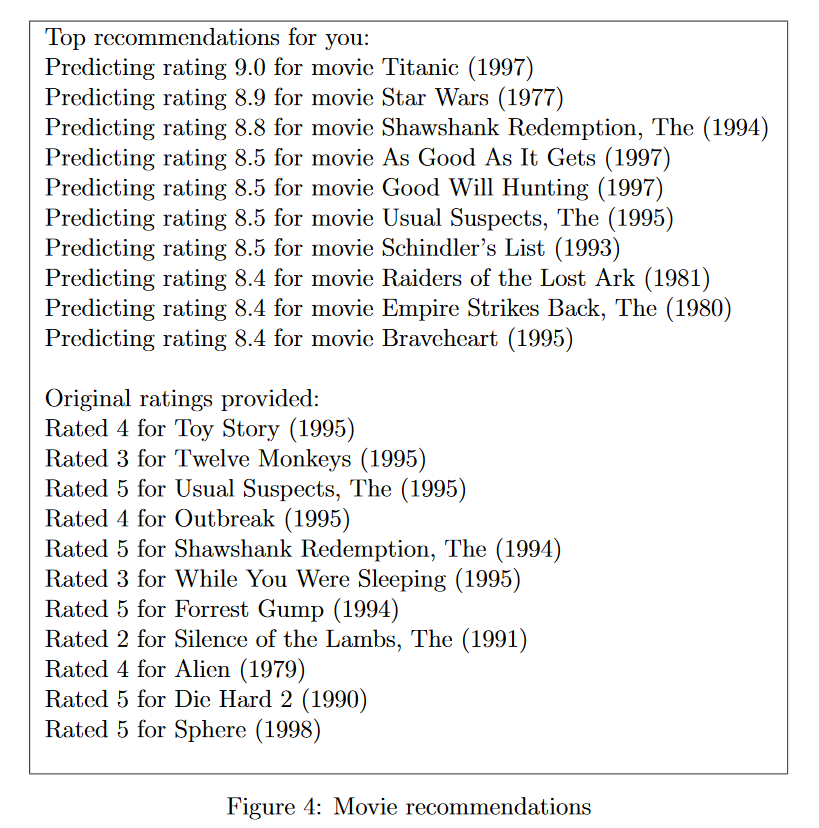

p = X * Theta';
my_predictions = p(:,1) + Ymean;

movieList = loadMovieList();

[r, ix] = sort(my_predictions,'descend');
for i=1:10
    j = ix(i);
    if i == 1
        fprintf('\nTop recommendations for you:\n');
    end
    fprintf('Predicting rating %.1f for movie %s\n', my_predictions(j), movieList{j});
end


Top recommendations for you:


Predicting rating 5.0 for movie Prefontaine (1997)
Predicting rating 5.0 for movie They Made Me a Criminal (1939)
Predicting rating 5.0 for movie Someone Else's America (1995)
Predicting rating 5.0 for movie Saint of Fort Washington, The (1993)
Predicting rating 5.0 for movie Aiqing wansui (1994)
Predicting rating 5.0 for movie Entertaining Angels: The Dorothy Day Story (1996)
Predicting rating 5.0 for movie Great Day in Harlem, A (1994)
Predicting rating 5.0 for movie Marlene Dietrich: Shadow and Light (1996)
Predicting rating 5.0 for movie Santa with Muscles (1996)
Predicting rating 5.0 for movie Star Kid (1997)


for i = 1:length(my_ratings)
    if i == 1
        fprintf('\n\nOriginal ratings provided:\n');
    end
    if my_ratings(i) > 0 
        fprintf('Rated %d for %s\n', my_ratings(i), movieList{i});
    end
end



Original ratings provided:


Rated 4 for Toy Story (1995)
Rated 3 for Twelve Monkeys (1995)
Rated 5 for Usual Suspects, The (1995)
Rated 4 for Outbreak (1995)
Rated 5 for Shawshank Redemption, The (1994)
Rated 3 for While You Were Sleeping (1995)
Rated 5 for Forrest Gump (1994)
Rated 2 for Silence of the Lambs, The (1991)
Rated 4 for Alien (1979)
Rated 5 for Die Hard 2 (1990)
Rated 5 for Sphere (1998)


## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored.

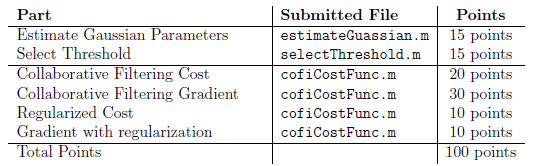

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.